# Design by Emulation

# 2.1.1 Position PID-controller

## 2.1.1.1-2.1.1.2  Backward

run("load_params_estimatedValues.m");
% Open Simulink model
open_system('Simulink/DiscretePID.slx');

#### Simulation results [$$T_s = 1ms$$] 

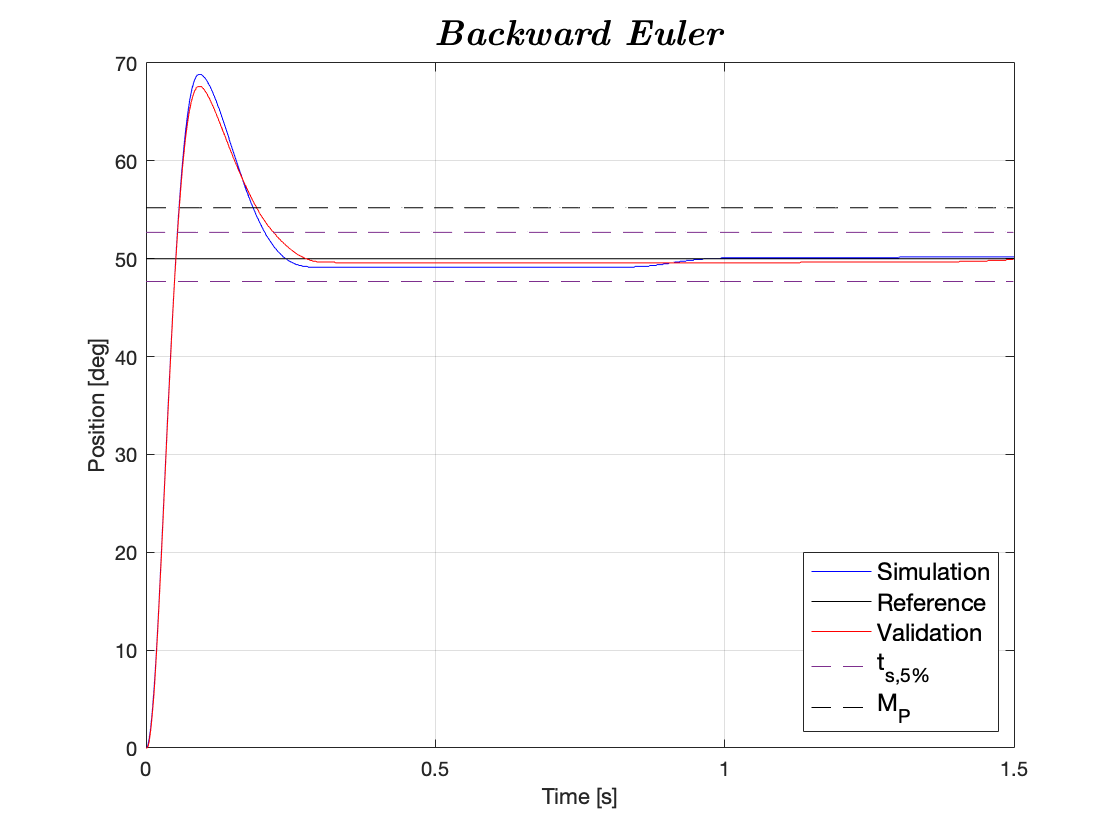

% Set parameters
set_param('DiscretePID', ...
    'SolverType', 'Variable-step', ...
    'Solver', 'ode45', ...
    'StopTime', '1.5', ...
    'AlgebraicLoopMsg','none');
% Step
set_param('DiscretePID/switch','sw','1');
set_param('DiscretePID/Step','Time','0','Before','0','After','50');

% % PID controller AW & FF
set_param('DiscretePID/Enable Anti-Windup','Value','0');
set_param('DiscretePID/Enable Feed-forward','Value','0');

% Sampling time
T_samp = 0.001;

% Controller
back.der_num = [1 -1];
back.der_den = [pid.sim.T_l+T_samp -pid.sim.T_l];
set_param('DiscretePID/PID controller_AWFF/Discrete-Time Integrator','IntegratorMethod','Integration: Backward Euler','SampleTime','T_samp'); 
set_param('DiscretePID/PID controller_AWFF1/Discrete-Time Integrator','IntegratorMethod','Integration: Backward Euler','SampleTime','T_samp');
set_param('DiscretePID/PID controller_AWFF/Discrete-Time Real Derivator','Numerator','back.der_num','Denominator','back.der_den','SampleTime','T_samp');
set_param('DiscretePID/PID controller_AWFF/AW_gain','Gain','0');
set_param('DiscretePID/PID controller_AWFF1/AW_gain','Gain','0');

% Run simulation
sim('DiscretePID');

% Extract simulation results
pid.t = simres1.time; % time vector 
pid.thl = simres1.signals(1).values(:,1); % load position
pid.thl_Ref = simres1.signals(1).values(:,2); % load position reference

ts5_low = [];
ts5_high = [];
Mp = [];
j = 1;
for i=0:0.001:1.5
    ts5_high(j) = pid.thl(length(pid.thl))+0.05*pid.thl(length(pid.thl));
    ts5_low(j) = pid.thl(length(pid.thl))-0.05*pid.thl(length(pid.thl));
    Mp(j) = pid.thl(length(pid.thl))+0.1*pid.thl(length(pid.thl));
    j = j + 1;
end

% Plot simulation results
figure
plot(pid.t, pid.thl, 'b');
hold on;
plot(pid.t, pid.thl_Ref, 'k');
hold on;
plot(back1.time(1:1500), back1.signals.values(1:1500,1), 'r');
hold on;
plot(back1.time(1:1500), ts5_low(1:1500), 'color', '#7E2F8E', 'LineStyle', '--');
hold on;
plot(back1.time(1:1500), ts5_high(1:1500), 'color', '#7E2F8E', 'LineStyle', '--');
hold on;
plot(back1.time(1:1500), Mp(1:1500), '--k');
ylabel('Position [deg]');
xlabel('Time [s]');
grid on;
tit = '\textbf{\textit{Backward Euler}}';
title(tit,'interpreter','latex');
ax = gca;
ax.TitleFontSizeMultiplier = 1.8;
lgd = legend('Simulation', 'Reference', 'Validation', 't_{s,5%}', '', 'M_P', 'Location', 'southeast');
lgd.FontSize = 12;

#### Simulation results [$$T_s = 10ms$$]

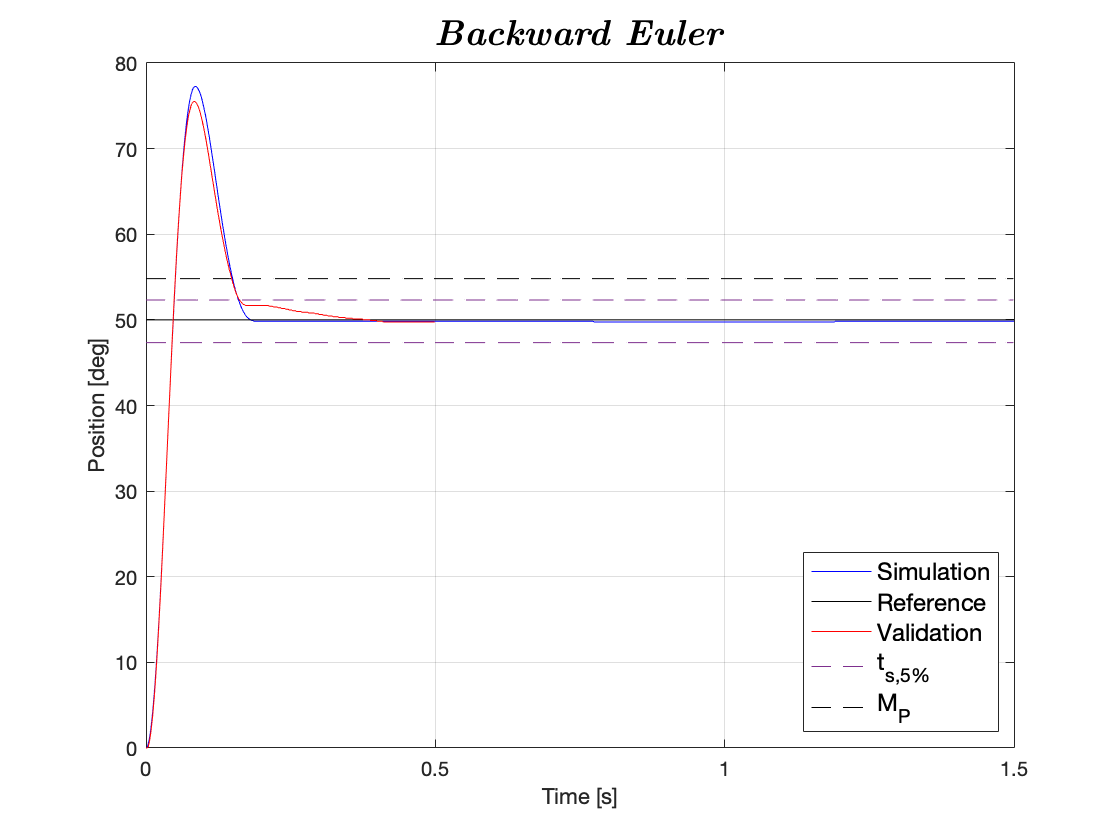

% Sampling time
T_samp = 0.01;

% Controller
back.der_num = [1 -1];
back.der_den = [pid.sim.T_l+T_samp -pid.sim.T_l];
set_param('DiscretePID/PID controller_AWFF/Discrete-Time Integrator','IntegratorMethod','Integration: Backward Euler','SampleTime','T_samp'); 
set_param('DiscretePID/PID controller_AWFF1/Discrete-Time Integrator','IntegratorMethod','Integration: Backward Euler','SampleTime','T_samp');
set_param('DiscretePID/PID controller_AWFF/Discrete-Time Real Derivator','Numerator','back.der_num','Denominator','back.der_den','SampleTime','T_samp');

% Run simulation
sim('DiscretePID');

% Extract simulation results
pid.t = simres1.time; % time vector 
pid.thl = simres1.signals(1).values(:,1); % load position
pid.thl_Ref = simres1.signals(1).values(:,2); % load position reference

ts5_low = [];
ts5_high = [];
Mp = [];
j = 1;
for i=0:0.001:1.5
    ts5_high(j) = pid.thl(length(pid.thl))+0.05*pid.thl(length(pid.thl));
    ts5_low(j) = pid.thl(length(pid.thl))-0.05*pid.thl(length(pid.thl));
    Mp(j) = pid.thl(length(pid.thl))+0.1*pid.thl(length(pid.thl));
    j = j + 1;
end

% Plot simulation results
figure
plot(pid.t, pid.thl, 'b');
hold on;
plot(pid.t, pid.thl_Ref, 'k');
hold on;
plot(back10.time(1:500), back10.signals.values(1:500,1), 'r');
hold on;
plot(back1.time(1:1500), ts5_low(1:1500), 'color', '#7E2F8E', 'LineStyle', '--');
hold on;
plot(back1.time(1:1500), ts5_high(1:1500), 'color', '#7E2F8E', 'LineStyle', '--');
hold on;
plot(back1.time(1:1500), Mp(1:1500), '--k');
ylabel('Position [deg]');
xlabel('Time [s]');
grid on;
tit = '\textbf{\textit{Backward Euler}}';
title(tit,'interpreter','latex');
ax = gca;
ax.TitleFontSizeMultiplier = 1.8;
lgd = legend('Simulation', 'Reference', 'Validation', 't_{s,5%}', '', 'M_P', 'Location', 'southeast');
lgd.FontSize = 12;

#### Simulation results [$$T_s = 50ms$$]

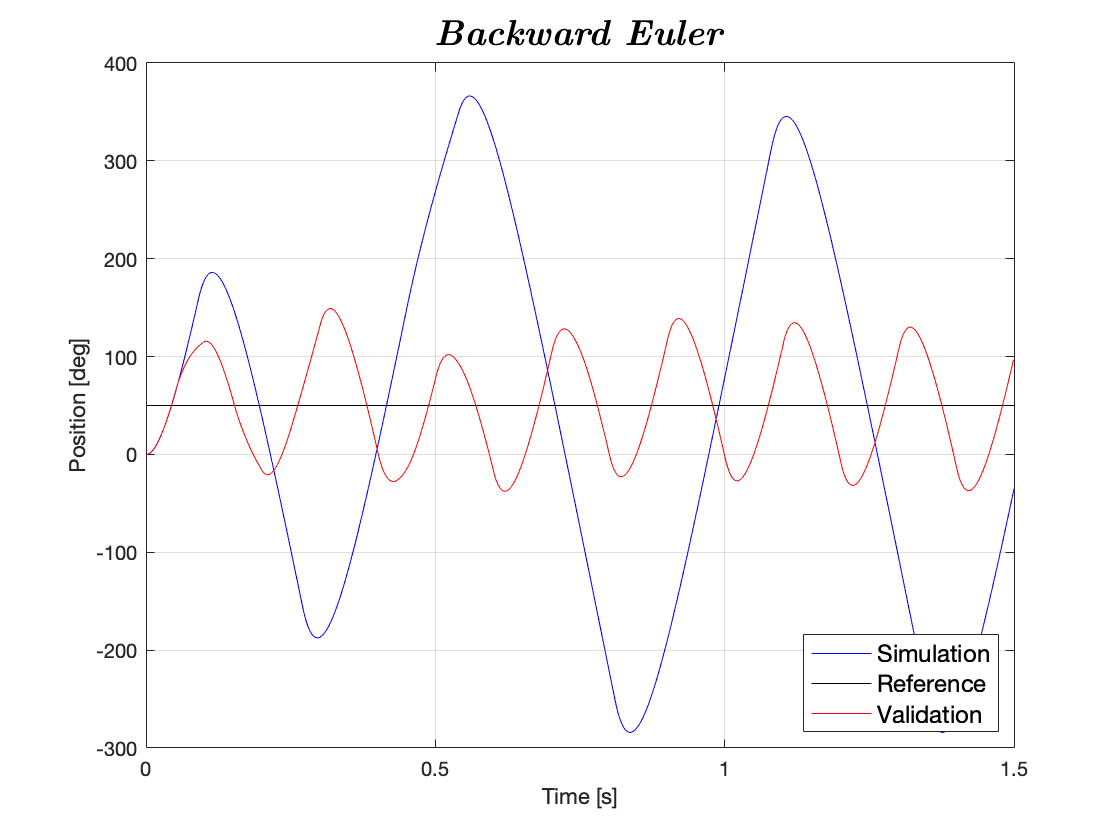

% Sampling time
T_samp = 0.09;

% Controller
back.der_num = [1 -1];
back.der_den = [pid.sim.T_l+T_samp -pid.sim.T_l];
set_param('DiscretePID/PID controller_AWFF/Discrete-Time Integrator','IntegratorMethod','Integration: Backward Euler','SampleTime','T_samp'); 
set_param('DiscretePID/PID controller_AWFF1/Discrete-Time Integrator','IntegratorMethod','Integration: Backward Euler','SampleTime','T_samp');
set_param('DiscretePID/PID controller_AWFF/Discrete-Time Real Derivator','Numerator','back.der_num','Denominator','back.der_den','SampleTime','T_samp');

% Run simulation
sim('DiscretePID');

% Extract simulation results
pid.t = simres1.time; % time vector 
pid.thl = simres1.signals(1).values(:,1); % load position
pid.thl_Ref = simres1.signals(1).values(:,2); % load position reference

% Plot simulation results
figure
plot(pid.t, pid.thl, 'b');
hold on;
plot(pid.t, pid.thl_Ref, 'k');
hold on;
plot(back50.time(1:1500), back50.signals.values(1:1500,1), 'r');
ylabel('Position [deg]');
xlabel('Time [s]');
grid on;
tit = '\textbf{\textit{Backward Euler}}';
title(tit,'interpreter','latex');
ax = gca;
ax.TitleFontSizeMultiplier = 1.8;
lgd = legend('Simulation', 'Reference', 'Validation', 'Location', 'southeast');
lgd.FontSize = 12;

## 2.1.1.3  Backward Anti-windup

#### Simulation results [$$T_s = 10ms$$] 

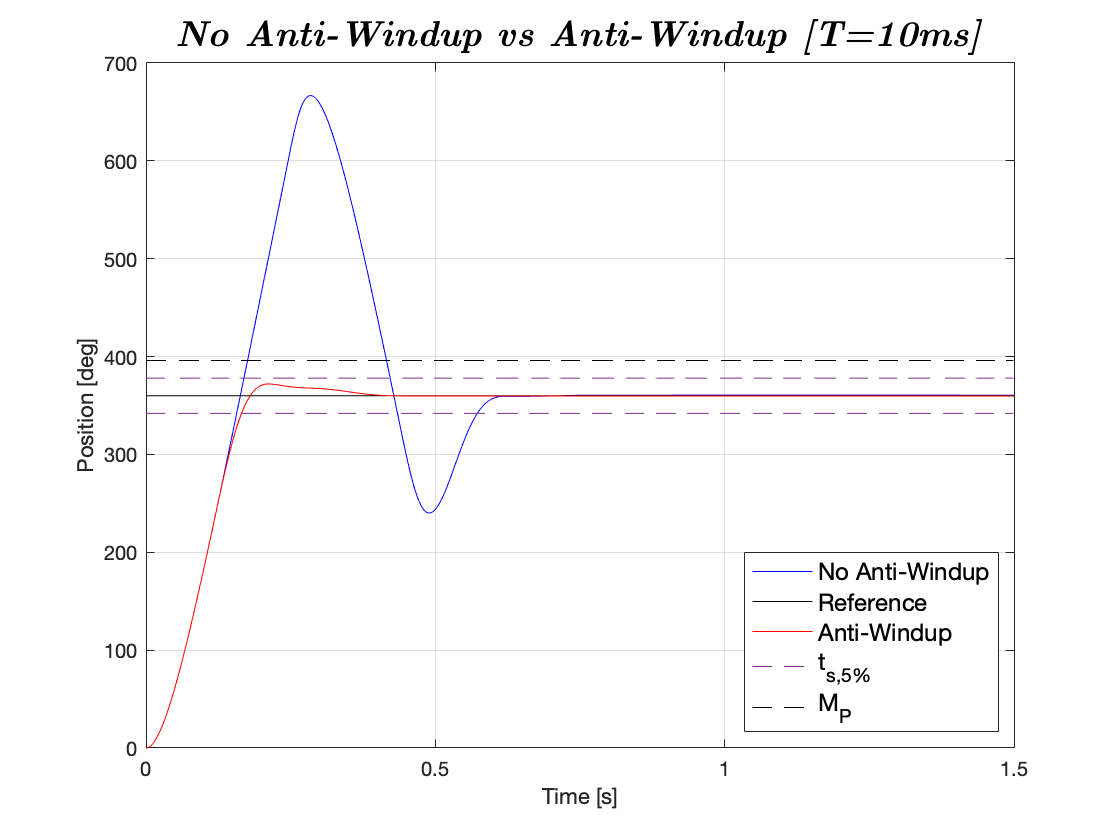

% Anti-Windup
AW.K_w = 5/0.15;

% Step
set_param('DiscretePID/switch','sw','1');
set_param('DiscretePID/switch1','sw','1');
set_param('DiscretePID/Step','Time','0','Before','0','After','360');
set_param('DiscretePID/Step1','Time','0','Before','0','After','360');

% PID controller AW & FF
set_param('DiscretePID/Enable Anti-Windup','Value','0'); % Disable Anti-windup
set_param('DiscretePID/Enable Anti-Windup1','Value','1'); % Enable Anti-windup
set_param('DiscretePID/Enable Feed-forward','Value','0'); % Disable Feed-forward
set_param('DiscretePID/Enable Feed-forward1','Value','0'); % Disable Feed-forward

% Sampling time
T_samp = 0.01;

% Controller
back.der_num = [1 -1];
back.der_den = [pid.sim.T_l+T_samp -pid.sim.T_l];
set_param('DiscretePID/PID controller_AWFF/Discrete-Time Integrator','IntegratorMethod','Integration: Backward Euler','SampleTime','T_samp'); 
set_param('DiscretePID/PID controller_AWFF1/Discrete-Time Integrator','IntegratorMethod','Integration: Backward Euler','SampleTime','T_samp');
set_param('DiscretePID/PID controller_AWFF/Discrete-Time Real Derivator','Numerator','back.der_num','Denominator','back.der_den','SampleTime','T_samp');
set_param('DiscretePID/PID controller_AWFF1/AW_gain','Gain','AW.K_w');

% Run simulation
sim('DiscretePID');

% Extract simulation results
AW.t = simres.time; % time vector 
AW.thl = simres.signals(1).values(:,1); % load position
AW.thl_AW = simres.signals(1).values(:,2); % load position AW
AW.thl_Ref = simres.signals(1).values(:,3); % load position reference

% Extract simulation results (CONTROL EFFORT)
AW.tu = simres2.time; % time vector 
AW.u = simres2.signals(1).values(:,1); % load position
AW.u_AW = simres2.signals(1).values(:,2); % load position AW

ts5_low = [];
ts5_high = [];
Mp = [];
sat_high = [];
sat_low = [];
j = 1;
for i=0:0.001:1.5
    ts5_high(j) = 360+0.05*360;
    ts5_low(j) = 360-0.05*360;
    sat_high(j) = 10;
    sat_low(j) = -10;
    Mp(j) = 360+0.1*360;
    j = j + 1;
end

for i=0:0.001:1.5
    ts5_high(j) = pid.thl(length(pid.thl))+0.05*pid.thl(length(pid.thl));
    ts5_low(j) = pid.thl(length(pid.thl))-0.05*pid.thl(length(pid.thl));
    Mp(j) = pid.thl(length(pid.thl))+0.1*pid.thl(length(pid.thl));
    j = j + 1;
end

% SIMULATION
% Plot simulation results
figure
plot(AW.t, AW.thl, 'b');
hold on;
plot(AW.t, AW.thl_Ref, 'k');
hold on;
plot(AW.t, AW.thl_AW, 'r');
hold on;
plot(back1.time(1:1500), ts5_low(1:1500), 'color', '#7E2F8E', 'LineStyle', '--');
hold on;
plot(back1.time(1:1500), ts5_high(1:1500), 'color', '#7E2F8E', 'LineStyle', '--');
hold on;
plot(back1.time(1:1500), Mp(1:1500), '--k');
ylabel('Position [deg]');
xlabel('Time [s]');
grid on;
tit = '\textbf{\textit{No Anti-Windup vs Anti-Windup [T=10ms]}}';
title(tit,'interpreter','latex');
ax = gca;
ax.TitleFontSizeMultiplier = 1.8;
lgd = legend('No Anti-Windup', 'Reference', 'Anti-Windup',  't_{s,5%}', '', 'M_P', 'Location', 'southeast');
lgd.FontSize = 12;

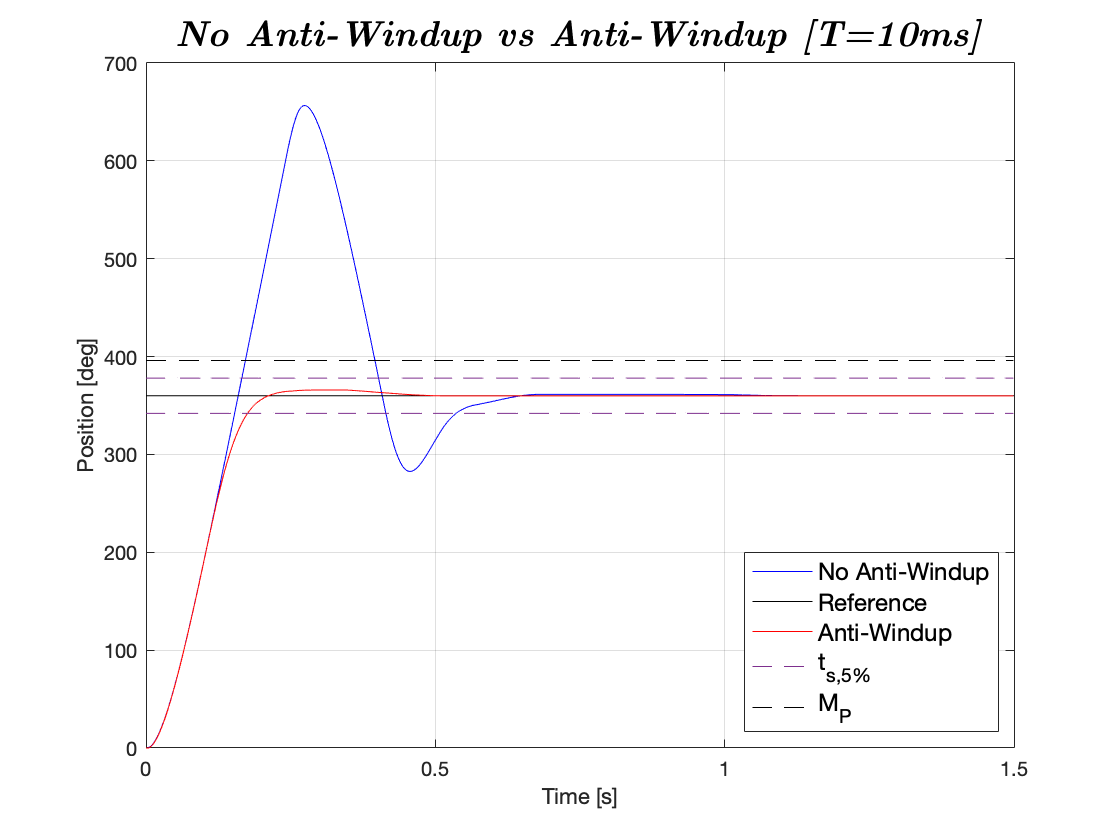


% EXPERIMENTAL
% Plot simulation results
figure
plot(AW.t(1:1500), noaw10.signals.values(1:1500), 'b');
hold on;
plot(AW.t, AW.thl_Ref, 'k');
hold on;
plot(AW.t(1:1500), aw10.signals.values(1:1500), 'r');
hold on;
plot(back1.time(1:1500), ts5_low(1:1500), 'color', '#7E2F8E', 'LineStyle', '--');
hold on;
plot(back1.time(1:1500), ts5_high(1:1500), 'color', '#7E2F8E', 'LineStyle', '--');
hold on;
plot(back1.time(1:1500), Mp(1:1500), '--k');
ylabel('Position [deg]');
xlabel('Time [s]');
grid on;
tit = '\textbf{\textit{No Anti-Windup vs Anti-Windup [T=10ms]}}';
title(tit,'interpreter','latex');
ax = gca;
ax.TitleFontSizeMultiplier = 1.8;
lgd = legend('No Anti-Windup', 'Reference', 'Anti-Windup',  't_{s,5%}', '', 'M_P', 'Location', 'southeast');
lgd.FontSize = 12;

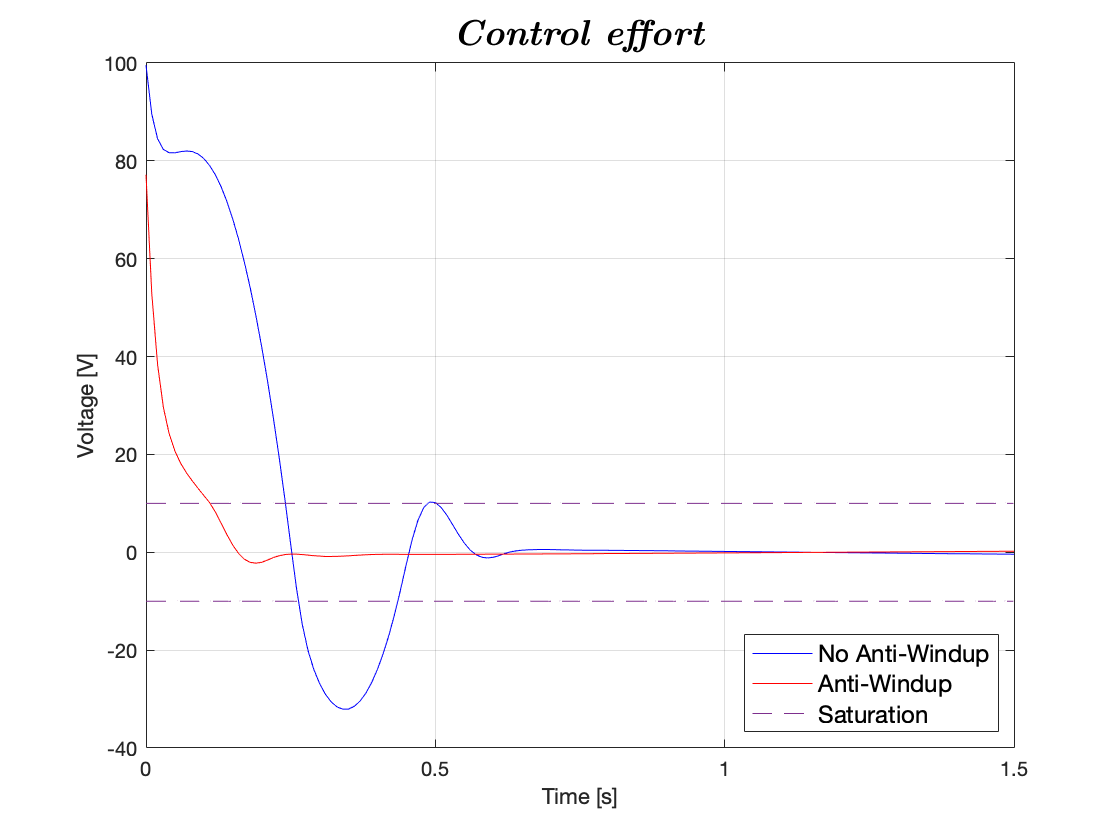

% CONTROL EFFORT (SIMULATION)
% Plot simulation results
figure
plot(AW.tu, AW.u, 'b');
hold on;
plot(AW.tu, AW.u_AW, 'r');
hold on;
plot(back1.time(1:1500), sat_low(1:1500), 'color', '#7E2F8E', 'LineStyle', '--');
hold on;
plot(back1.time(1:1500), sat_high(1:1500), 'color', '#7E2F8E', 'LineStyle', '--');
ylabel('Voltage [V]');
xlabel('Time [s]');
grid on;
tit = '\textbf{\textit{Control effort}}';
title(tit,'interpreter','latex');
ax = gca;
ax.TitleFontSizeMultiplier = 1.8;
lgd = legend('No Anti-Windup', 'Anti-Windup', 'Saturation', 'Location', 'southeast');
lgd.FontSize = 12;

## 2.1.1.4  Backward Feed-forward [OPTIONAL]

#### Simulation results [$$T_s = 10ms$$] 

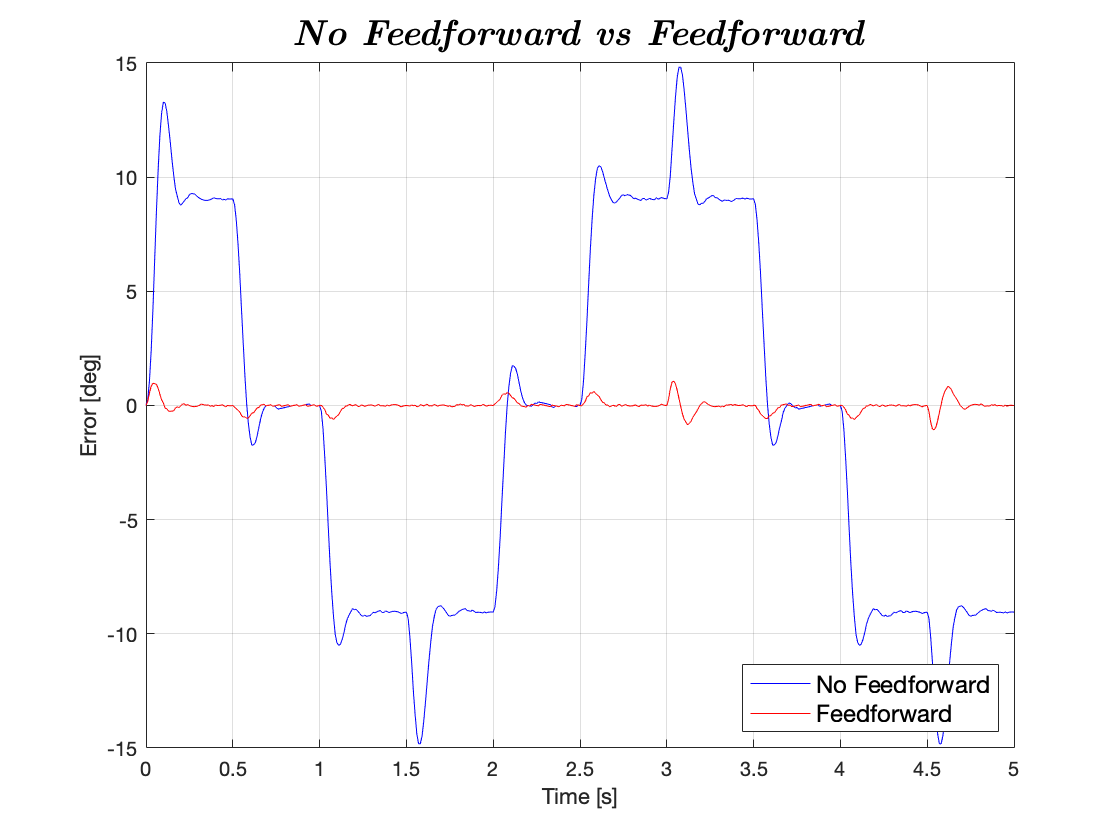

% Set parameters
set_param('DiscretePID', ...
    'SolverType', 'Variable-step', ...
    'Solver', 'ode45', ...
    'StopTime', '5');

% Sequence generator
set_param('DiscretePID/switch','sw','0');
set_param('DiscretePID/switch1','sw','0');

% % PID controller AW & FF
set_param('DiscretePID/Enable Anti-Windup','Value','0'); % Disable Anti-windup
set_param('DiscretePID/Enable Anti-Windup1','Value','0'); % Disable Anti-windup
set_param('DiscretePID/Enable Feed-forward','Value','0'); % Disable Feed-forward
set_param('DiscretePID/Enable Feed-forward1','Value','1'); % Enable Feed-forward

% Sampling time
T_samp = 0.01;

% Run simulation
sim('DiscretePID');

% Extract simulation results
FF.t = simerr.time; % time vector 
FF.err = simerr.signals(1).values(:,1); % load position
FF.err_FF = simerr.signals(1).values(:,2); % load position AW

% SIMULATION
% Plot simulation results
figure
plot(FF.t, FF.err, 'b');
hold on;
plot(FF.t, FF.err_FF, 'r');
ylabel('Error [deg]');
xlabel('Time [s]');
grid on;
tit = '\textbf{\textit{No Feedforward vs Feedforward}}';
title(tit,'interpreter','latex');
ax = gca;
ax.TitleFontSizeMultiplier = 1.8;
lgd = legend('No Feedforward', 'Feedforward', 'Location', 'southeast');
lgd.FontSize = 12;

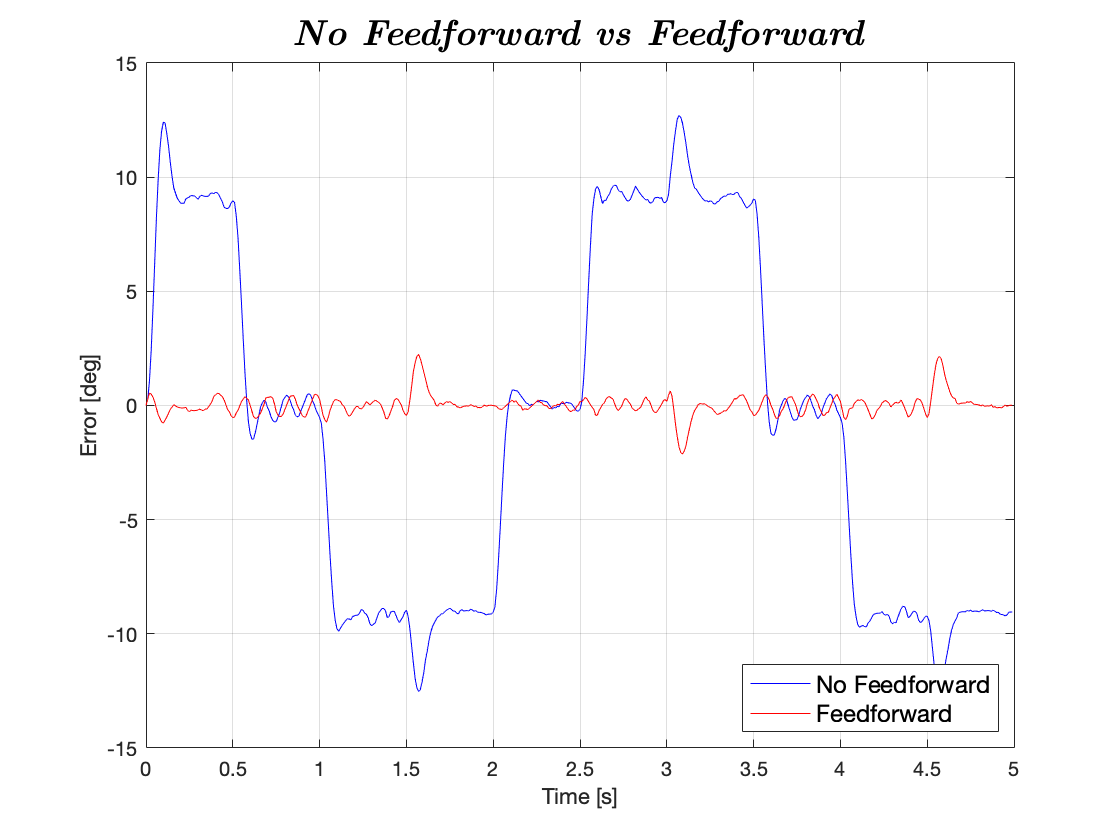

% EXPERIMENTAL
% Plot simulation results
figure
plot(noff10_err.time(1:500), noff10_err.signals.values(1:500), 'b');
hold on;
plot(ff10_err.time(1:500), ff10_err.signals.values(1:500), 'r');
ylabel('Error [deg]');
xlabel('Time [s]');
grid on;
tit = '\textbf{\textit{No Feedforward vs Feedforward}}';
title(tit,'interpreter','latex');
ax = gca;
ax.TitleFontSizeMultiplier = 1.8;
lgd = legend('No Feedforward', 'Feedforward', 'Location', 'southeast');
lgd.FontSize = 12;

## 2.1.1.5  Forward

#### Simulation results [$$T_s = 1ms$$] 

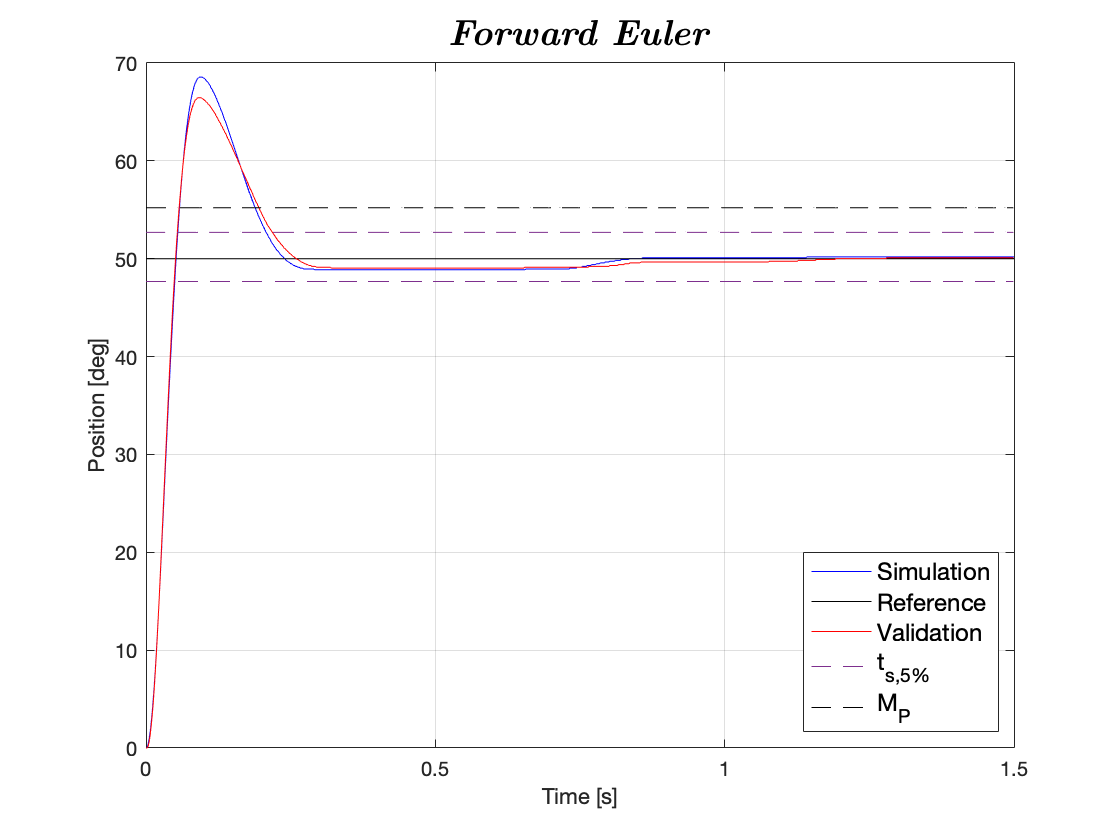

% Set parameters
set_param('DiscretePID', ...
    'SolverType', 'Variable-step', ...
    'Solver', 'ode45', ...
    'StopTime', '1.5');
% Step
set_param('DiscretePID/switch','sw','1');
set_param('DiscretePID/Step','Time','0','Before','0','After','50');

% % PID controller AW & FF
set_param('DiscretePID/Enable Anti-Windup','Value','0');
set_param('DiscretePID/Enable Feed-forward','Value','0');

% Sampling time
T_samp = 0.001;

% Controller
forw.der_num = [1 -1];
forw.der_den = [pid.sim.T_l T_samp-pid.sim.T_l];
set_param('DiscretePID/PID controller_AWFF/Discrete-Time Integrator','IntegratorMethod','Integration: Forward Euler','SampleTime','T_samp');
set_param('DiscretePID/PID controller_AWFF/Discrete-Time Real Derivator','Numerator','forw.der_num','Denominator','forw.der_den','SampleTime','T_samp');

% Run simulation
sim('DiscretePID');

% Extract simulation results
pid.t = simres1.time; % time vector 
pid.thl = simres1.signals(1).values(:,1); % load position
pid.thl_Ref = simres1.signals(1).values(:,2); % load position reference

ts5_low = [];
ts5_high = [];
Mp = [];
j = 1;
for i=0:0.001:1.5
    ts5_high(j) = pid.thl(length(pid.thl))+0.05*pid.thl(length(pid.thl));
    ts5_low(j) = pid.thl(length(pid.thl))-0.05*pid.thl(length(pid.thl));
    Mp(j) = pid.thl(length(pid.thl))+0.1*pid.thl(length(pid.thl));
    j = j + 1;
end


% Plot simulation results
figure
plot(pid.t, pid.thl, 'b');
hold on;
plot(pid.t, pid.thl_Ref, 'k');
hold on;
plot(forw1.time(1:1500), forw1.signals.values(1:1500,1), 'r');
hold on;
plot(forw1.time(1:1500), ts5_low(1:1500), 'color', '#7E2F8E', 'LineStyle', '--');
hold on;
plot(forw1.time(1:1500), ts5_high(1:1500), 'color', '#7E2F8E', 'LineStyle', '--');
hold on;
plot(forw1.time(1:1500), Mp(1:1500), '--k');
ylabel('Position [deg]');
xlabel('Time [s]');
grid on;
tit = '\textbf{\textit{Forward Euler}}';
title(tit,'interpreter','latex');
ax = gca;
ax.TitleFontSizeMultiplier = 1.8;
lgd = legend('Simulation', 'Reference', 'Validation', 't_{s,5%}', '', 'M_P', 'Location', 'southeast');
lgd.FontSize = 12;

#### Simulation results [$$T_s = 10ms$$] 

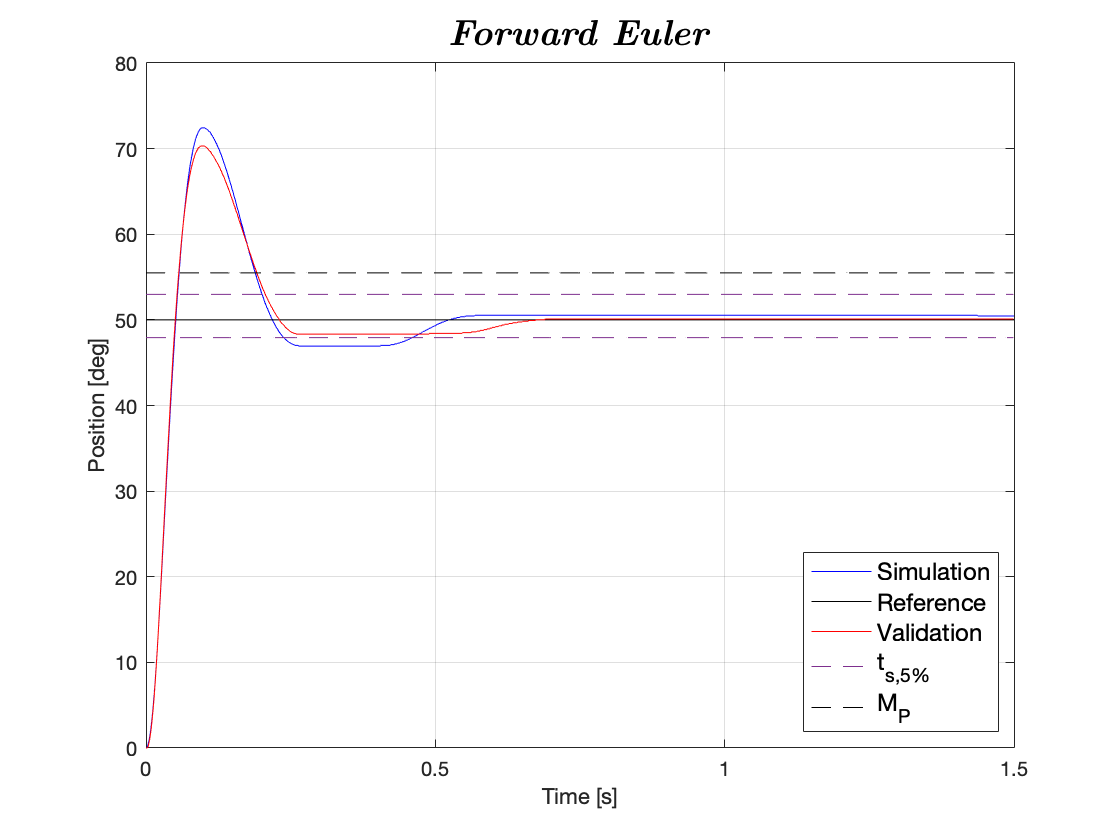

% Sampling time
T_samp = 0.01;

% Controller
forw.der_num = [1 -1];
forw.der_den = [pid.sim.T_l T_samp-pid.sim.T_l];
set_param('DiscretePID/PID controller_AWFF/Discrete-Time Integrator','IntegratorMethod','Integration: Forward Euler','SampleTime','T_samp');
set_param('DiscretePID/PID controller_AWFF/Discrete-Time Real Derivator','Numerator','forw.der_num','Denominator','forw.der_den','SampleTime','T_samp');

% Run simulation
sim('DiscretePID');

% Extract simulation results
pid.t = simres1.time; % time vector 
pid.thl = simres1.signals(1).values(:,1); % load position
pid.thl_Ref = simres1.signals(1).values(:,2); % load position reference

ts5_low = [];
ts5_high = [];
Mp = [];
j = 1;
for i=0:0.001:1.5
    ts5_high(j) = pid.thl(length(pid.thl))+0.05*pid.thl(length(pid.thl));
    ts5_low(j) = pid.thl(length(pid.thl))-0.05*pid.thl(length(pid.thl));
    Mp(j) = pid.thl(length(pid.thl))+0.1*pid.thl(length(pid.thl));
    j = j + 1;
end


% Plot simulation results
figure
plot(pid.t, pid.thl, 'b');
hold on;
plot(pid.t, pid.thl_Ref, 'k');
hold on;
plot(forw10.time(1:1500), forw10.signals.values(1:1500,1), 'r');
hold on;
plot(forw10.time(1:1500), ts5_low(1:1500), 'color', '#7E2F8E', 'LineStyle', '--');
hold on;
plot(forw10.time(1:1500), ts5_high(1:1500), 'color', '#7E2F8E', 'LineStyle', '--');
hold on;
plot(forw10.time(1:1500), Mp(1:1500), '--k');
ylabel('Position [deg]');
xlabel('Time [s]');
grid on;
tit = '\textbf{\textit{Forward Euler}}';
title(tit,'interpreter','latex');
ax = gca;
ax.TitleFontSizeMultiplier = 1.8;
lgd = legend('Simulation', 'Reference', 'Validation', 't_{s,5%}', '', 'M_P', 'Location', 'southeast');
lgd.FontSize = 12;

#### Simulation results [$$T_s = 50ms$$]

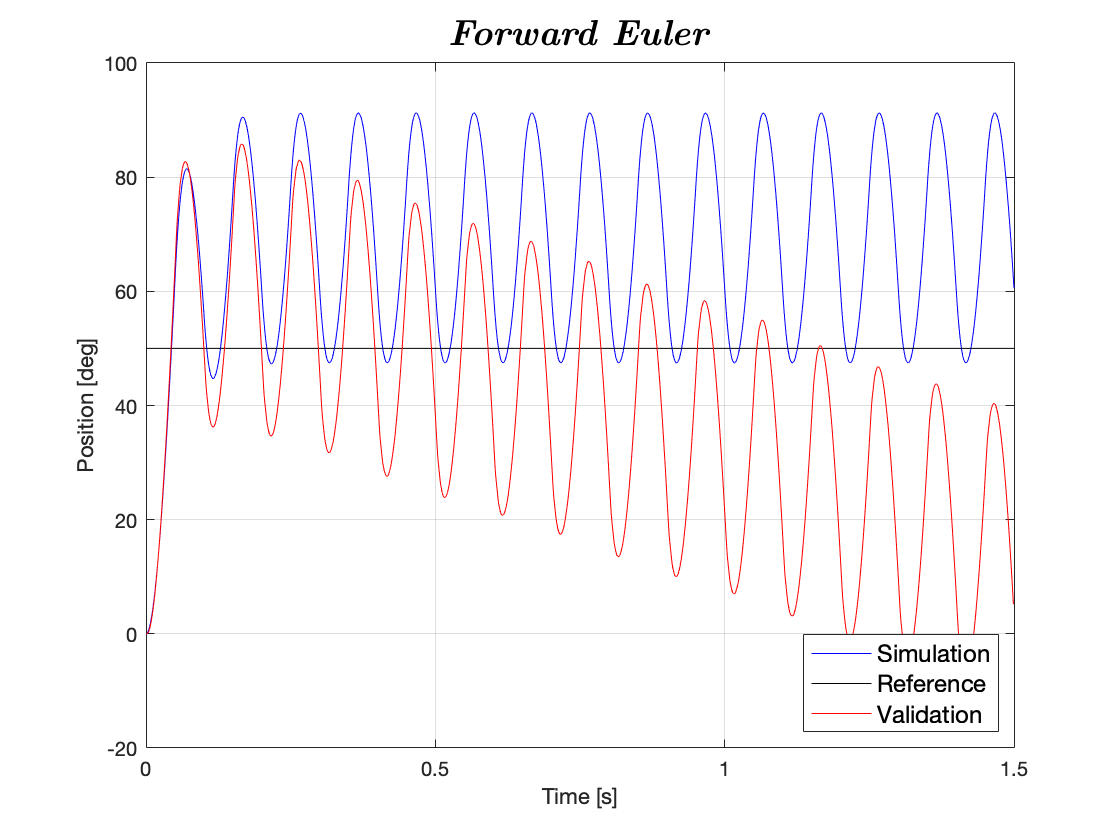

% Sampling time
T_samp = 0.05;

% Controller
forw.der_num = [1 -1];
forw.der_den = [pid.sim.T_l T_samp-pid.sim.T_l];
set_param('DiscretePID/PID controller_AWFF/Discrete-Time Integrator','IntegratorMethod','Integration: Forward Euler','SampleTime','T_samp');
set_param('DiscretePID/PID controller_AWFF/Discrete-Time Real Derivator','Numerator','forw.der_num','Denominator','forw.der_den','SampleTime','T_samp');

% Run simulation
sim('DiscretePID');

% Extract simulation results
pid.t = simres1.time; % time vector 
pid.thl = simres1.signals(1).values(:,1); % load position
pid.thl_Ref = simres1.signals(1).values(:,2); % load position reference

% Plot simulation results
figure
plot(pid.t, pid.thl, 'b');
hold on;
plot(pid.t, pid.thl_Ref, 'k');
hold on;
plot(forw50.time(1:1500), forw50.signals.values(1:1500,1), 'r');
ylabel('Position [deg]');
xlabel('Time [s]');
grid on;
tit = '\textbf{\textit{Forward Euler}}';
title(tit,'interpreter','latex');
ax = gca;
ax.TitleFontSizeMultiplier = 1.8;
lgd = legend('Simulation', 'Reference', 'Validation', 'Location', 'southeast');
lgd.FontSize = 12;

## 2.1.1.5  Tustin

#### Simulation results [$$T_s = 1ms$$]

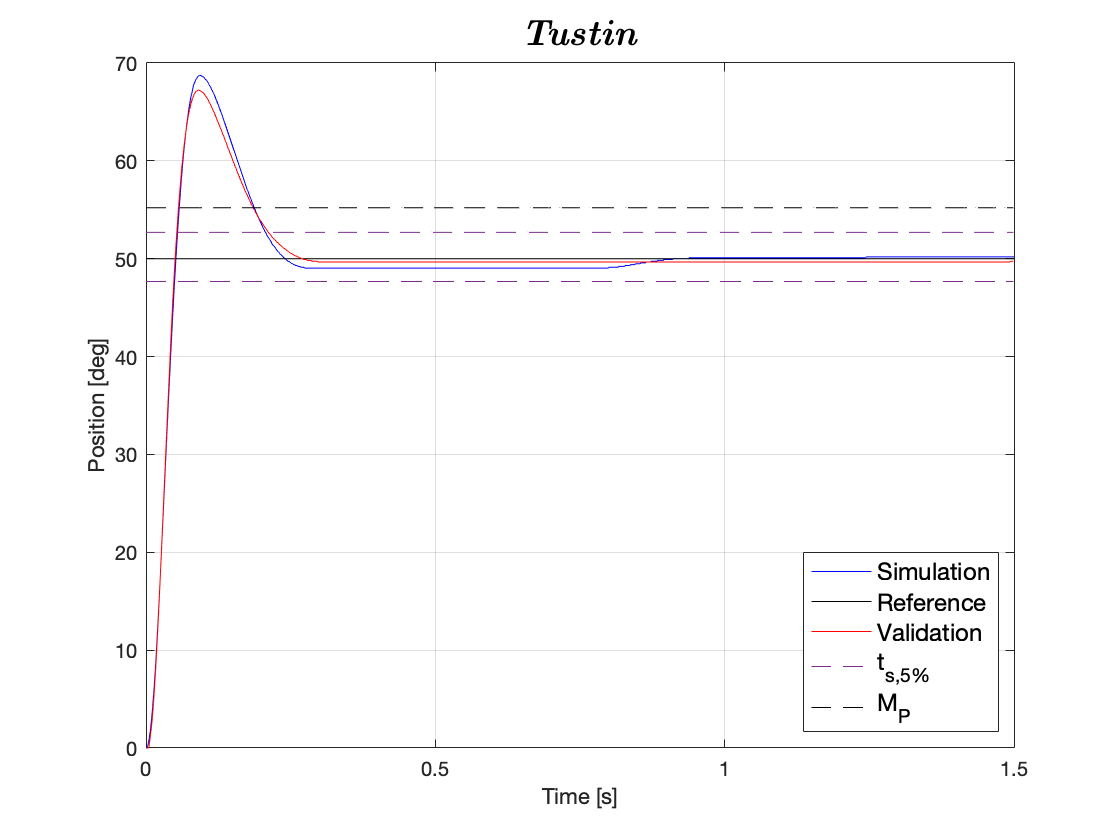

% Sampling time
T_samp = 0.001;

% Controller
tust.der_num = [2 -2];
tust.der_den = [2*pid.sim.T_l+T_samp T_samp-2*pid.sim.T_l]; 
set_param('DiscretePID/PID controller_AWFF/Discrete-Time Integrator','IntegratorMethod','Integration: Trapezoidal','SampleTime','T_samp');
set_param('DiscretePID/PID controller_AWFF/Discrete-Time Real Derivator','Numerator','tust.der_num','Denominator','tust.der_den','SampleTime','T_samp');

% Run simulation
sim('DiscretePID');

% Extract simulation results
pid.t = simres1.time; % time vector 
pid.thl = simres1.signals(1).values(:,1); % load position
pid.thl_Ref = simres1.signals(1).values(:,2); % load position reference

ts5_low = [];
ts5_high = [];
Mp = [];
j = 1;
for i=0:0.001:1.5
    ts5_high(j) = pid.thl(length(pid.thl))+0.05*pid.thl(length(pid.thl));
    ts5_low(j) = pid.thl(length(pid.thl))-0.05*pid.thl(length(pid.thl));
    Mp(j) = pid.thl(length(pid.thl))+0.1*pid.thl(length(pid.thl));
    j = j + 1;
end


% Plot simulation results
figure
plot(pid.t, pid.thl, 'b');
hold on;
plot(pid.t, pid.thl_Ref, 'k');
hold on;
plot(tust1.time(1:1500), tust1.signals.values(1:1500,1), 'r');
hold on;
plot(tust1.time(1:1500), ts5_low(1:1500), 'color', '#7E2F8E', 'LineStyle', '--');
hold on;
plot(tust1.time(1:1500), ts5_high(1:1500), 'color', '#7E2F8E', 'LineStyle', '--');
hold on;
plot(tust1.time(1:1500), Mp(1:1500), '--k');
ylabel('Position [deg]');
xlabel('Time [s]');
grid on;
tit = '\textbf{\textit{Tustin}}';
title(tit,'interpreter','latex');
ax = gca;
ax.TitleFontSizeMultiplier = 1.8;
lgd = legend('Simulation', 'Reference', 'Validation', 't_{s,5%}', '', 'M_P', 'Location', 'southeast');
lgd.FontSize = 12;

#### Simulation results [$$T_s = 10ms$$]

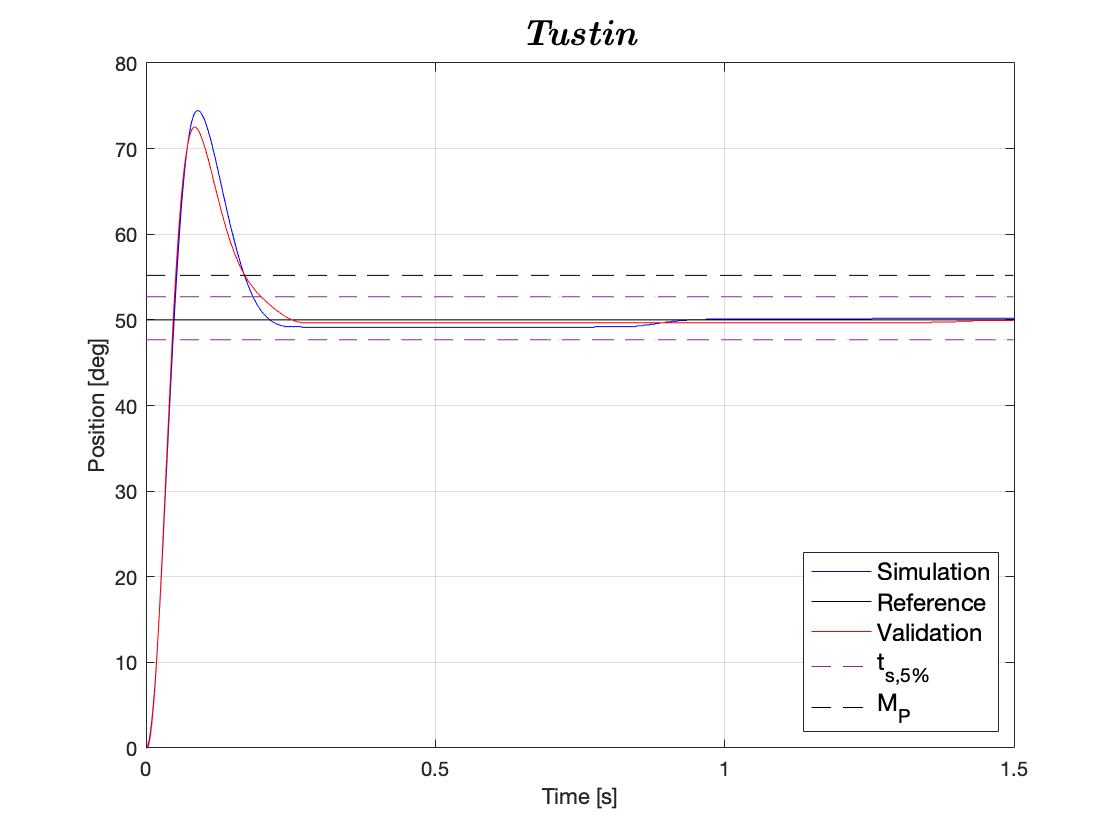

% Sampling time
T_samp = 0.01;

% Controller
tust.der_num = [2 -2];
tust.der_den = [2*pid.sim.T_l+T_samp T_samp-2*pid.sim.T_l]; 
set_param('DiscretePID/PID controller_AWFF/Discrete-Time Integrator','IntegratorMethod','Integration: Trapezoidal','SampleTime','T_samp');
set_param('DiscretePID/PID controller_AWFF/Discrete-Time Real Derivator','Numerator','tust.der_num','Denominator','tust.der_den','SampleTime','T_samp');

% Run simulation
sim('DiscretePID');

% Extract simulation results
pid.t = simres1.time; % time vector 
pid.thl = simres1.signals(1).values(:,1); % load position
pid.thl_Ref = simres1.signals(1).values(:,2); % load position reference

ts5_low = [];
ts5_high = [];
Mp = [];
j = 1;
for i=0:0.001:1.5
    ts5_high(j) = pid.thl(length(pid.thl))+0.05*pid.thl(length(pid.thl));
    ts5_low(j) = pid.thl(length(pid.thl))-0.05*pid.thl(length(pid.thl));
    Mp(j) = pid.thl(length(pid.thl))+0.1*pid.thl(length(pid.thl));
    j = j + 1;
end


% Plot simulation results
figure
plot(pid.t, pid.thl, 'b');
hold on;
plot(pid.t, pid.thl_Ref, 'k');
hold on;
plot(tust10.time(1:1500), tust10.signals.values(1:1500,1), 'r');
hold on;
plot(tust10.time(1:1500), ts5_low(1:1500), 'color', '#7E2F8E', 'LineStyle', '--');
hold on;
plot(tust10.time(1:1500), ts5_high(1:1500), 'color', '#7E2F8E', 'LineStyle', '--');
hold on;
plot(tust10.time(1:1500), Mp(1:1500), '--k');
ylabel('Position [deg]');
xlabel('Time [s]');
grid on;
tit = '\textbf{\textit{Tustin}}';
title(tit,'interpreter','latex');
ax = gca;
ax.TitleFontSizeMultiplier = 1.8;
lgd = legend('Simulation', 'Reference', 'Validation', 't_{s,5%}', '', 'M_P', 'Location', 'southeast');
lgd.FontSize = 12;

#### Simulation results [$$T_s = 50ms$$]

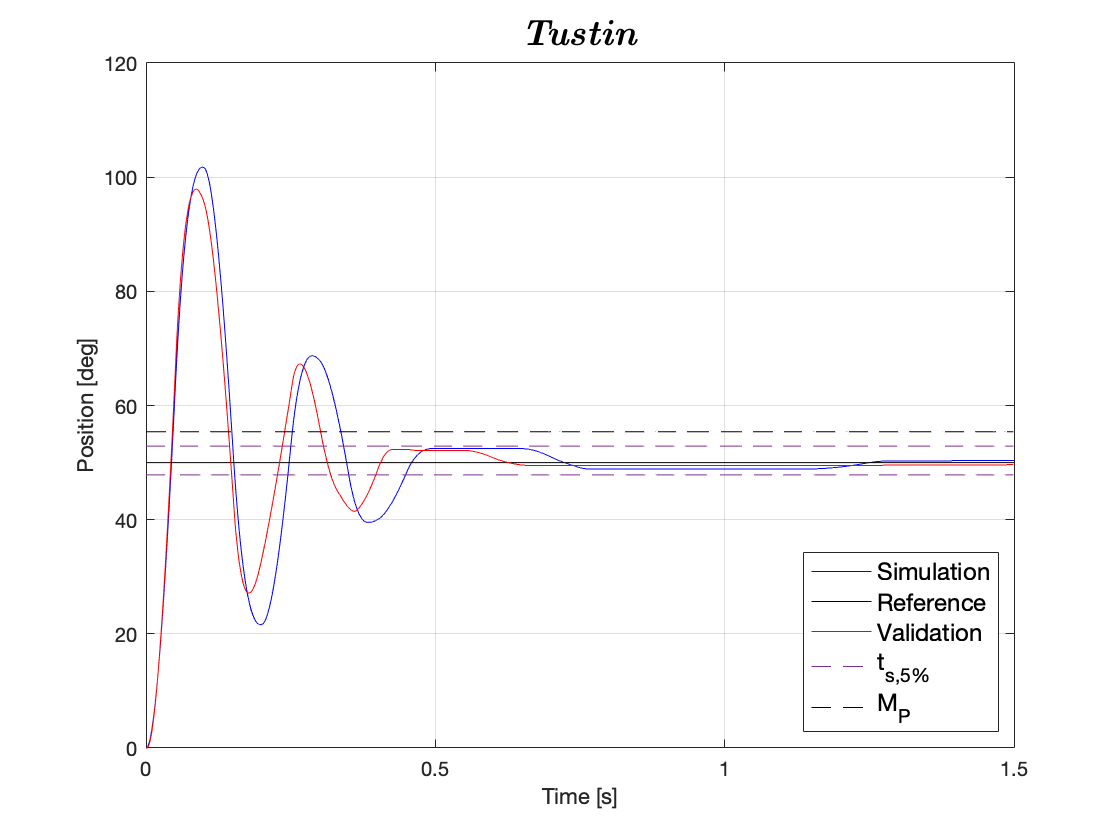

% Sampling time
T_samp = 0.05;

% Controller
tust.der_num = [2 -2];
tust.der_den = [2*pid.sim.T_l+T_samp T_samp-2*pid.sim.T_l]; 
set_param('DiscretePID/PID controller_AWFF/Discrete-Time Integrator','IntegratorMethod','Integration: Trapezoidal','SampleTime','T_samp');
set_param('DiscretePID/PID controller_AWFF/Discrete-Time Real Derivator','Numerator','tust.der_num','Denominator','tust.der_den','SampleTime','T_samp');

% Run simulation
sim('DiscretePID');

% Extract simulation results
pid.t = simres1.time; % time vector 
pid.thl = simres1.signals(1).values(:,1); % load position
pid.thl_Ref = simres1.signals(1).values(:,2); % load position reference

ts5_low = [];
ts5_high = [];
Mp = [];
j = 1;
for i=0:0.001:1.5
    ts5_high(j) = pid.thl(length(pid.thl))+0.05*pid.thl(length(pid.thl));
    ts5_low(j) = pid.thl(length(pid.thl))-0.05*pid.thl(length(pid.thl));
    Mp(j) = pid.thl(length(pid.thl))+0.1*pid.thl(length(pid.thl));
    j = j + 1;
end


% Plot simulation results
figure
plot(pid.t, pid.thl, 'b');
hold on;
plot(pid.t, pid.thl_Ref, 'k');
hold on;
plot(tust50.time(1:1500), tust50.signals.values(1:1500,1), 'r');
hold on;
plot(tust50.time(1:1500), ts5_low(1:1500), 'color', '#7E2F8E', 'LineStyle', '--');
hold on;
plot(tust50.time(1:1500), ts5_high(1:1500), 'color', '#7E2F8E', 'LineStyle', '--');
hold on;
plot(tust50.time(1:1500), Mp(1:1500), '--k');
ylabel('Position [deg]');
xlabel('Time [s]');
grid on;
tit = '\textbf{\textit{Tustin}}';
title(tit,'interpreter','latex');
ax = gca;
ax.TitleFontSizeMultiplier = 1.8;
lgd = legend('Simulation', 'Reference', 'Validation', 't_{s,5%}', '', 'M_P', 'Location', 'southeast');
lgd.FontSize = 12;

% Continuos controller tf

## 2.1.1.5  ZOH

#### Simulation results [$$T_s = 1ms$$] 

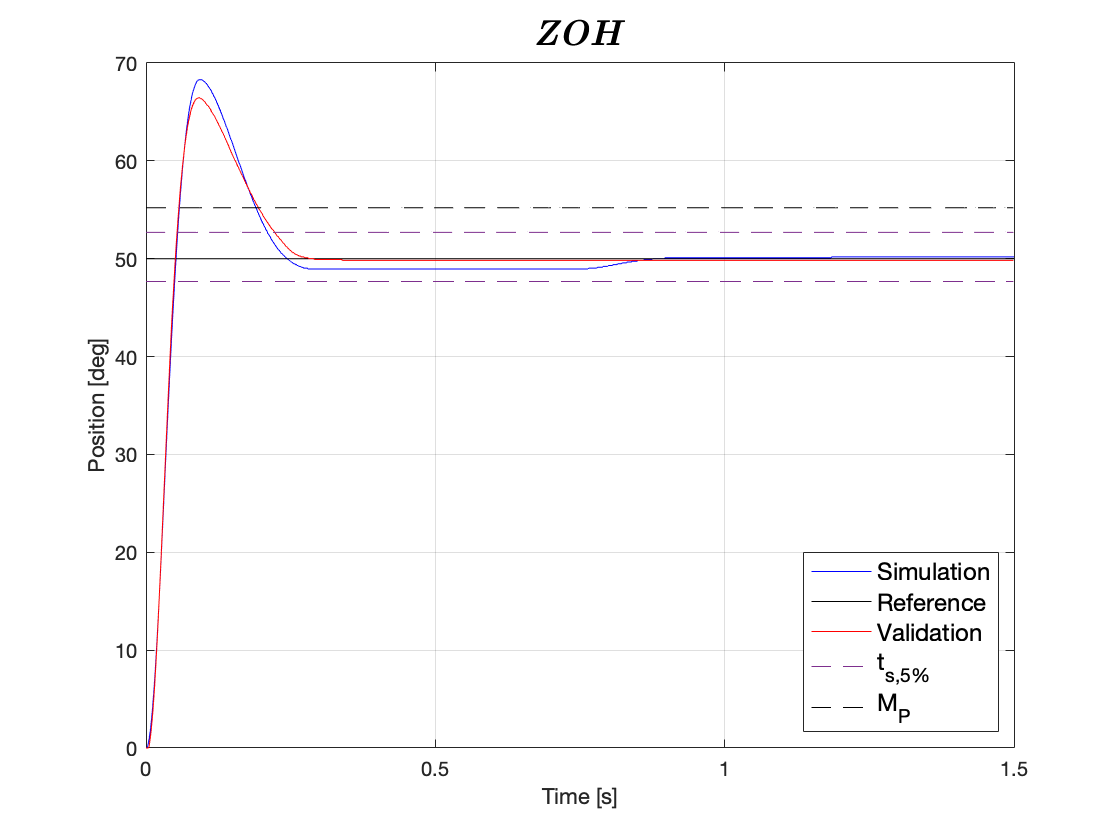

s = tf('s');
Cs = pid.Kp + pid.Ki/s + pid.Kd*s/(pid.sim.T_l*s + 1);

% Sampling time
T_samp = 0.001;

[zoh_num,zoh_den] = tfdata(c2d(Cs,T_samp,'zoh'));
zoh_num = cell2mat(zoh_num);
zoh_den = cell2mat(zoh_den);

% Open Simulink model
open_system('Simulink/Pid_ZOH.slx');

% Set parameters
set_param('Pid_ZOH', ...
    'SolverType', 'Variable-step', ...
    'Solver', 'ode45', ...
    'StopTime', '1.5');
% Step
set_param('Pid_ZOH/Step','Time','0','Before','0','After','50');

% Controller
set_param('Pid_ZOH/Controller/Discrete Transfer Fcn','Numerator','zoh_num','Denominator','zoh_den');

% Run simulation
sim('Pid_ZOH');

% Extract simulation results
zoh.t = simres.time; % time vector 
zoh.thl = simres.signals(1).values(:,1); % load position
zoh.thl_Ref = simres.signals(1).values(:,2); % load position reference

ts5_low = [];
ts5_high = [];
Mp = [];
j = 1;
for i=0:0.001:1.5
    ts5_high(j) = zoh.thl(length(zoh.thl))+0.05*zoh.thl(length(zoh.thl));
    ts5_low(j) = zoh.thl(length(zoh.thl))-0.05*zoh.thl(length(zoh.thl));
    Mp(j) = zoh.thl(length(zoh.thl))+0.1*zoh.thl(length(zoh.thl));
    j = j + 1;
end

% Plot simulation results
figure
plot(zoh.t, zoh.thl, 'b');
hold on;
plot(zoh.t, zoh.thl_Ref, 'k');
hold on;
plot(zoh1.time(1:1500), zoh1.signals.values(1:1500,1), 'r');
hold on;
plot(zoh1.time(1:1500), ts5_low(1:1500), 'color', '#7E2F8E', 'LineStyle', '--');
hold on;
plot(zoh1.time(1:1500), ts5_high(1:1500), 'color', '#7E2F8E', 'LineStyle', '--');
hold on;
plot(zoh1.time(1:1500), Mp(1:1500), '--k');
ylabel('Position [deg]');
xlabel('Time [s]');
grid on;
tit = '\textbf{\textit{ZOH}}';
title(tit,'interpreter','latex');
ax = gca;
ax.TitleFontSizeMultiplier = 1.8;
lgd = legend('Simulation', 'Reference', 'Validation', 't_{s,5%}', '', 'M_P', 'Location', 'southeast');
lgd.FontSize = 12;

#### Simulation results [$$T_s = 10ms$$] 

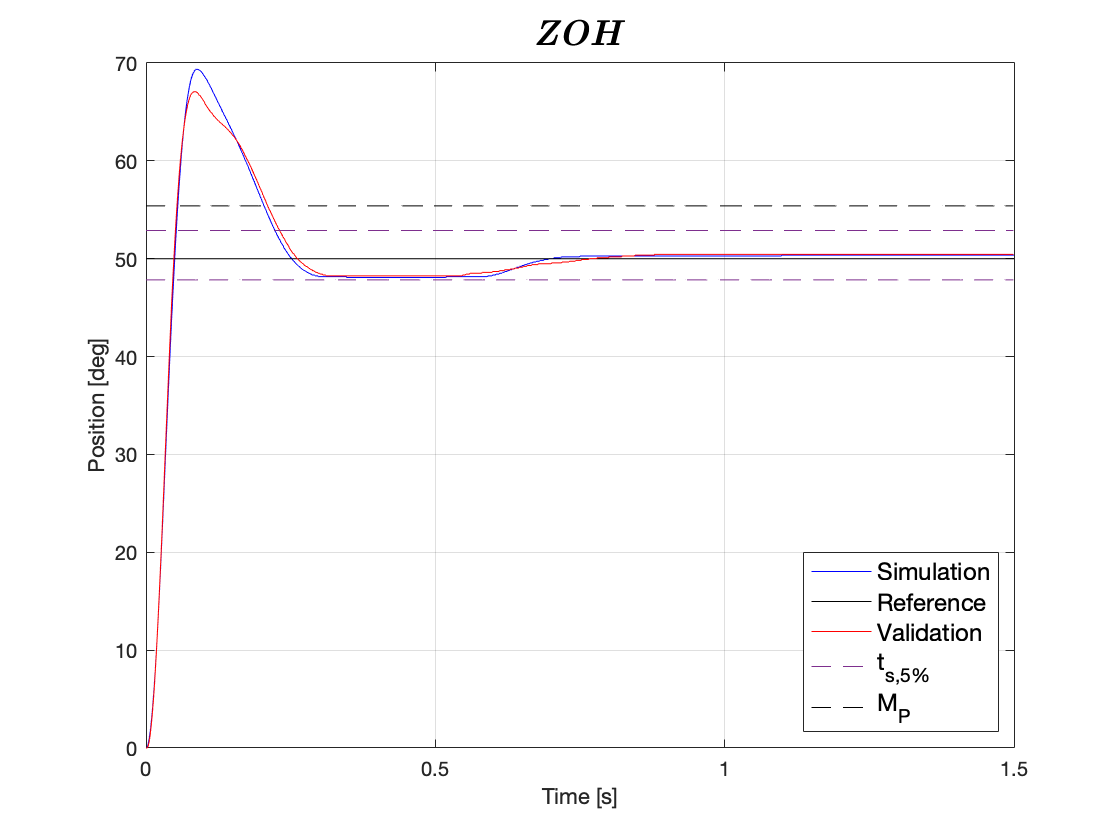

% Continuos controller tf
s = tf('s');
Cs = pid.Kp + pid.Ki/s + pid.Kd*s/(pid.sim.T_l*s + 1);

% Sampling time
T_samp = 0.01;

[zoh_num,zoh_den] = tfdata(c2d(Cs,T_samp,'zoh'));
zoh_num = cell2mat(zoh_num);
zoh_den = cell2mat(zoh_den);

% Controller
set_param('Pid_ZOH/Controller/Discrete Transfer Fcn','Numerator','zoh_num','Denominator','zoh_den');

% Run simulation
sim('Pid_ZOH');

% Extract simulation results
zoh.t = simres.time; % time vector 
zoh.thl = simres.signals(1).values(:,1); % load position
zoh.thl_Ref = simres.signals(1).values(:,2); % load position reference

ts5_low = [];
ts5_high = [];
Mp = [];
j = 1;
for i=0:0.001:1.5
    ts5_high(j) = zoh.thl(length(zoh.thl))+0.05*zoh.thl(length(zoh.thl));
    ts5_low(j) = zoh.thl(length(zoh.thl))-0.05*zoh.thl(length(zoh.thl));
    Mp(j) = zoh.thl(length(zoh.thl))+0.1*zoh.thl(length(zoh.thl));
    j = j + 1;
end

% Plot simulation results
figure
plot(zoh.t, zoh.thl, 'b');
hold on;
plot(zoh.t, zoh.thl_Ref, 'k');
hold on;
plot(zoh10.time(1:1500), zoh10.signals.values(1:1500,1), 'r');
hold on;
plot(zoh10.time(1:1500), ts5_low(1:1500), 'color', '#7E2F8E', 'LineStyle', '--');
hold on;
plot(zoh10.time(1:1500), ts5_high(1:1500), 'color', '#7E2F8E', 'LineStyle', '--');
hold on;
plot(zoh10.time(1:1500), Mp(1:1500), '--k');
ylabel('Position [deg]');
xlabel('Time [s]');
grid on;
tit = '\textbf{\textit{ZOH}}';
title(tit,'interpreter','latex');
ax = gca;
ax.TitleFontSizeMultiplier = 1.8;
lgd = legend('Simulation', 'Reference', 'Validation', 't_{s,5%}', '', 'M_P', 'Location', 'southeast');
lgd.FontSize = 12;

#### Simulation results [$$T_s = 50ms$$] 

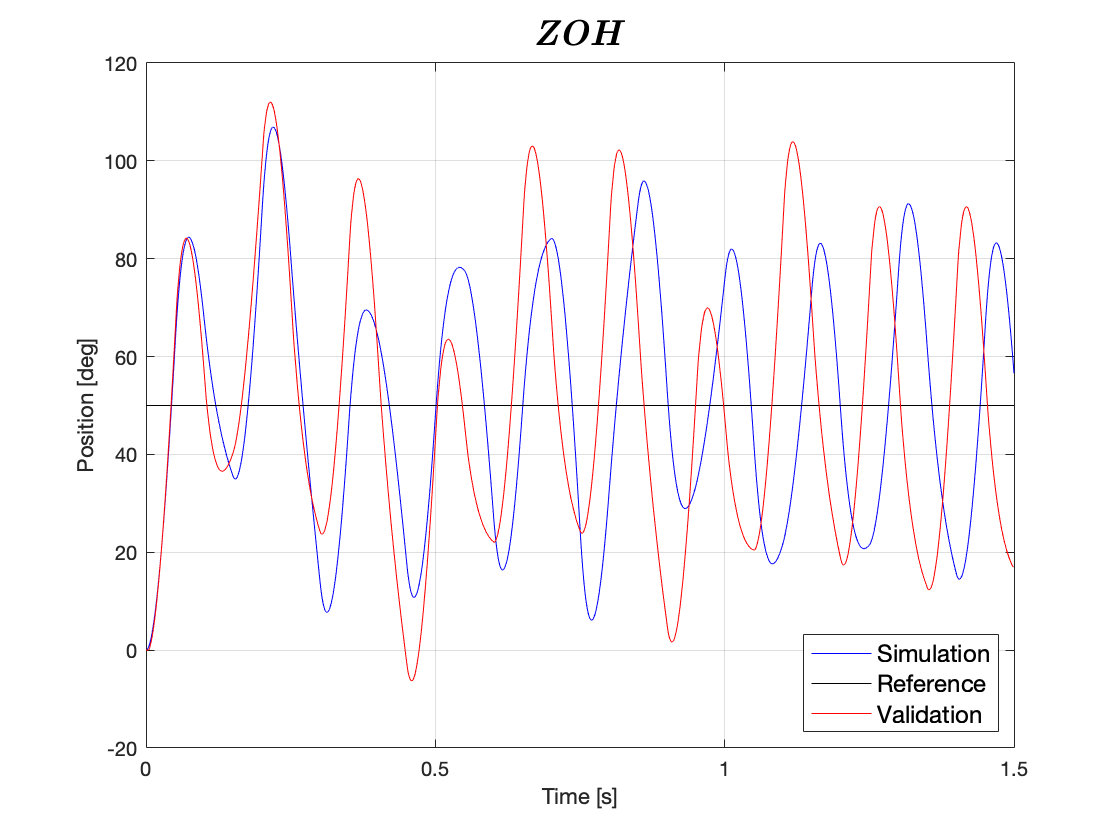

% Continuos controller tf
s = tf('s');
Cs = pid.Kp + pid.Ki/s + pid.Kd*s/(pid.sim.T_l*s + 1);

% Sampling time
T_samp = 0.05;

[zoh_num,zoh_den] = tfdata(c2d(Cs,T_samp,'zoh'));
zoh_num = cell2mat(zoh_num);
zoh_den = cell2mat(zoh_den);

% Controller
set_param('Pid_ZOH/Controller/Discrete Transfer Fcn','Numerator','zoh_num','Denominator','zoh_den');

% Run simulation
sim('Pid_ZOH');

% Extract simulation results
zoh.t = simres.time; % time vector 
zoh.thl = simres.signals(1).values(:,1); % load position
zoh.thl_Ref = simres.signals(1).values(:,2); % load position reference

% Plot simulation results
figure
plot(zoh.t, zoh.thl, 'b');
hold on;
plot(zoh.t, zoh.thl_Ref, 'k');
hold on;
plot(zoh50.time(1:1500), zoh50.signals.values(1:1500,1), 'r');
ylabel('Position [deg]');
xlabel('Time [s]');
grid on;
tit = '\textbf{\textit{ZOH}}';
title(tit,'interpreter','latex');
ax = gca;
ax.TitleFontSizeMultiplier = 1.8;
lgd = legend('Simulation', 'Reference', 'Validation', 'Location', 'southeast');
lgd.FontSize = 12;

# 2.1.2 Position state–space controller

## Reduced-Order Observer [Continuos-case]

## 2.1.2.1-2.1.2.2 NOMINAL

% State-Space model
state_space.T_m = (simp_model.Req*est_par.J_eq)/(mot.Kt*mot.Ke + simp_model.Req*est_par.B_eq);
state_space.K_m = (drv.dcgain*mot.Kt)/(mot.Kt*mot.Ke + simp_model.Req*est_par.B_eq);
state_space.A = [0 1;0 -1/state_space.T_m];
state_space.B = [0;state_space.K_m/(state_space.T_m*gbox.N)];
state_space.C = [1 0];
state_space.D = 0;

% Continuos controller tf
s = tf('s');
Cs = pid.Kp + pid.Ki/s + pid.Kd*s/(pid.sim.T_l*s + 1);

% Compute L
reduced.L = place(-1/state_space.T_m,1,5*min(eig(Cs)));

% A0
reduced.A0 = -1/state_space.T_m - reduced.L;
% B0
reduced.B0 = [state_space.K_m/(gbox.N*state_space.T_m) (-1/state_space.T_m - reduced.L)*reduced.L];
% C0
reduced.C0 = [0;1];
% D0
reduced.D0 = [0 1;0 reduced.L];

% Dominant Pole Approximation
mp = 0.1;
ts = 0.15;
nominal.delta = log(1/mp)/(sqrt(pi*pi + log(1/mp)*log(1/mp)));
nominal.wn = 3/(nominal.delta*ts);

% Nominal control
nominal.X = linsolve([state_space.A,state_space.B;state_space.C 0],[0;0;1]);
nominal.N_x = nominal.X(1:2,:);
nominal.N_u = nominal.X(3,:);

% Pole placement
nominal.p1 = -nominal.delta*nominal.wn + 1i*nominal.wn*sqrt(1-nominal.delta^2);
nominal.p2 = conj(nominal.p1);
nominal.poles = [nominal.p1 nominal.p2];
nominal.K = place(state_space.A,state_space.B,nominal.poles);

% Open Simulink model
open_system('Simulink/Cont_ReducedOrder.slx');

#### Simulation results [$$40\degree $$] 

% Set parameters
set_param('Cont_ReducedOrder', ...
    'SolverType', 'Variable-step', ...
    'Solver', 'ode45', ...
    'StopTime', '2');
% Step
set_param('Cont_ReducedOrder/Step','Time','0','Before','0','After','40');

% Controller
set_param('Cont_ReducedOrder/Controller/State feed-forward gain','Gain','nominal.N_x');
set_param('Cont_ReducedOrder/Controller/Input feed-forward gain','Gain','nominal.N_u');
set_param('Cont_ReducedOrder/Controller/State feedback gain','Gain','nominal.K','Multiplication','Matrix(K*u)');
set_param('Cont_ReducedOrder/Enable Integral','Value','0'); % Nominal
set_param('Cont_ReducedOrder/Controller/Ki','Gain','0'); % Ki

% Continuos Reduced state observer
set_param('Cont_ReducedOrder/Reduced Order Observer','A','reduced.A0','B','reduced.B0','C','reduced.C0','D','reduced.D0');

% Run simulation
sim('Cont_ReducedOrder');
 
% Extract simulation results
reducednom40.t = simres.time; % time vector 
reducednom40.thl = simres.signals(1).values(:,1); % load position
reducednom40.thl_Ref = simres.signals(1).values(:,2); % load position reference

#### Simulation results [$$70\degree $$] 

% Step
set_param('Cont_ReducedOrder/Step','Time','0','Before','0','After','70');

% Run simulation
sim('Cont_ReducedOrder');
 
% Extract simulation results
reducednom70.t = simres.time; % time vector 
reducednom70.thl = simres.signals(1).values(:,1); % load position
reducednom70.thl_Ref = simres.signals(1).values(:,2); % load position reference

#### Simulation results [$$120\degree $$] 

% Step
set_param('Cont_ReducedOrder/Step','Time','0','Before','0','After','120');

% Run simulation
sim('Cont_ReducedOrder');
 
% Extract simulation results
reducednom120.t = simres.time; % time vector 
reducednom120.thl = simres.signals(1).values(:,1); % load position
reducednom120.thl_Ref = simres.signals(1).values(:,2); % load position reference

## Reduced-Order Observer [Discrete-case: Forward]

## 2.1.2.3-2.1.2.4 NOMINAL

#### Simulation results [$$T_s = 1ms$$] 

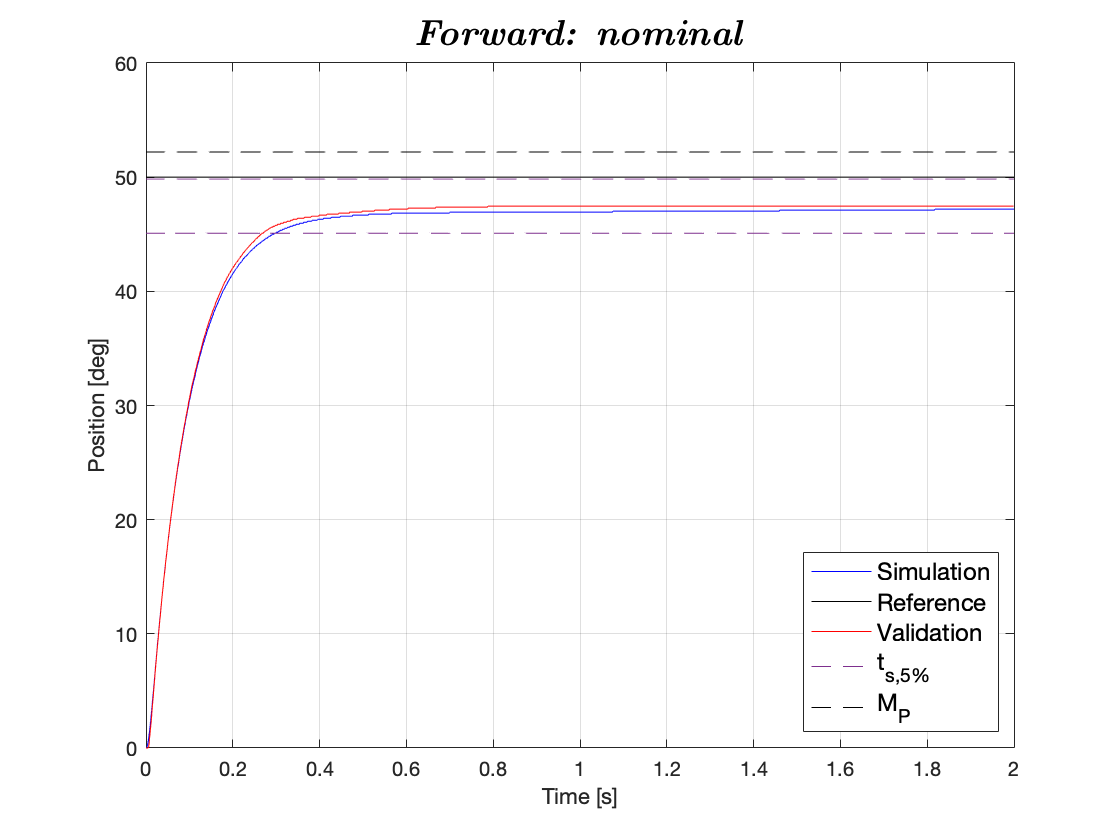

% Sampling time
T_samp = 0.001;

% PHY0
reduced.Phy0 = 1 + reduced.A0*T_samp;
% GAMMA0
reduced.Gamma0 = reduced.B0*T_samp;
% HO
reduced.H0 = reduced.C0;
% J0
reduced.J0 = reduced.D0;

% Open Simulink model
open_system('Simulink/Disc_ReducedOrder.slx');
% Set parameters
set_param('Disc_ReducedOrder', ...
    'SolverType', 'Variable-step', ...
    'Solver', 'ode45', ...
    'StopTime', '2', ...
    'AlgebraicLoopMsg','none');
% Step
set_param('Disc_ReducedOrder/Step','Time','0','Before','0','After','50');

% Controller
set_param('Disc_ReducedOrder/Controller/State feed-forward gain','Gain','nominal.N_x');
set_param('Disc_ReducedOrder/Controller/Input feed-forward gain','Gain','nominal.N_u');
set_param('Disc_ReducedOrder/Controller/State feedback gain','Gain','nominal.K','Multiplication','Matrix(K*u)');
set_param('Disc_ReducedOrder/Enable Integral','Value','0'); % Nominal
set_param('Disc_ReducedOrder/Controller/Ki','Gain','0'); % Ki
set_param('Disc_ReducedOrder/Controller/Discrete-Time Integrator','IntegratorMethod','Integration: Forward Euler','SampleTime','T_samp'); % Integrator

% Discrete Reduced state observer
set_param('Disc_ReducedOrder/Discrete Reduced Order Observer','A','reduced.Phy0','B','reduced.Gamma0','C','reduced.H0','D','reduced.J0','SampleTime','T_samp');

% Run simulation
sim('Disc_ReducedOrder');
 
% Extract simulation results
reduced_nomfor_1ms.t = simres.time; % time vector 
reduced_nomfor_1ms.thl = simres.signals(1).values(:,1); % load position
reduced_nomfor_1ms.thl_Ref = simres.signals(1).values(:,2); % load position reference

ts5_low = [];
ts5_high = [];
Mp = [];
time = [];
j = 1;
for i=0:0.001:2
    ts5_high(j) = nomfor1.signals.values(length(nomfor1.signals.values),1)+0.05*nomfor1.signals.values(length(nomfor1.signals.values),1);
    ts5_low(j) = nomfor1.signals.values(length(nomfor1.signals.values),1)-0.05*nomfor1.signals.values(length(nomfor1.signals.values),1);
    Mp(j) = nomfor1.signals.values(length(nomfor1.signals.values),1)+0.1*nomfor1.signals.values(length(nomfor1.signals.values),1);
    time(j) = i;
    j = j + 1;
end

% Plot simulation results
figure
plot(reduced_nomfor_1ms.t, reduced_nomfor_1ms.thl, 'b');
hold on;
plot(reduced_nomfor_1ms.t, reduced_nomfor_1ms.thl_Ref, 'k');
hold on;
plot(nomfor1.time(1:2000), nomfor1.signals.values(1:2000,1), 'r');
hold on;
plot(time, ts5_low, 'color', '#7E2F8E', 'LineStyle', '--');
hold on;
plot(time, ts5_high, 'color', '#7E2F8E', 'LineStyle', '--');
hold on;
plot(time, Mp, '--k');
ylabel('Position [deg]');
xlabel('Time [s]');
grid on;
tit = '\textbf{\textit{Forward: nominal}}';
title(tit,'interpreter','latex');
ax = gca;
ax.TitleFontSizeMultiplier = 1.8;
lgd = legend('Simulation', 'Reference', 'Validation', 't_{s,5%}', '', 'M_P', 'Location', 'southeast');
lgd.FontSize = 12;

#### Simulation results [$$T_s = 10ms$$] 

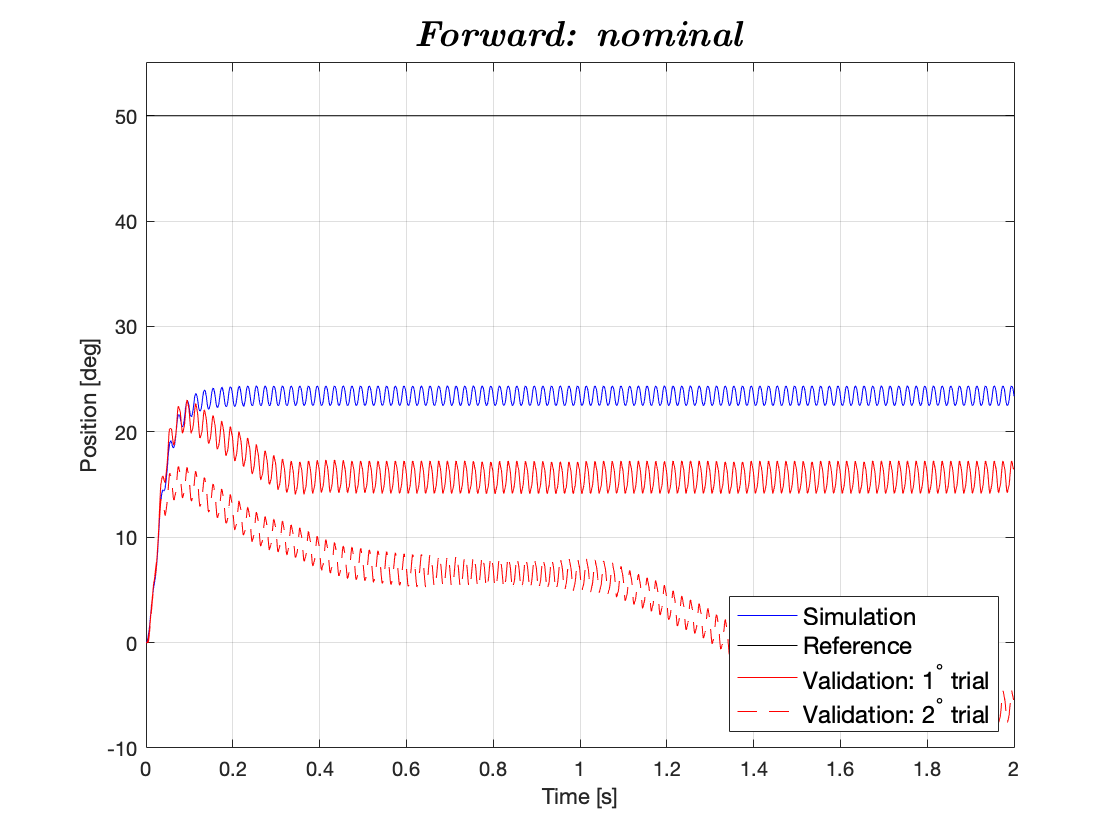

% Sampling time
T_samp = 0.01;

% PHY0
reduced.Phy0 = 1 + reduced.A0*T_samp;
% GAMMA0
reduced.Gamma0 = reduced.B0*T_samp;
% HO
reduced.H0 = reduced.C0;
% J0
reduced.J0 = reduced.D0;

% Discrete Reduced state observer
set_param('Disc_ReducedOrder/Discrete Reduced Order Observer','A','reduced.Phy0','B','reduced.Gamma0','C','reduced.H0','D','reduced.J0','SampleTime','T_samp');

% Run simulation
sim('Disc_ReducedOrder');
 
% Extract simulation results
reduced_nomfor_10ms.t = simres.time; % time vector 
reduced_nomfor_10ms.thl = simres.signals(1).values(:,1); % load position
reduced_nomfor_10ms.thl_Ref = simres.signals(1).values(:,2); % load position reference

% Plot simulation results
figure
plot(reduced_nomfor_10ms.t, reduced_nomfor_10ms.thl, 'b');
hold on;
plot(reduced_nomfor_10ms.t, reduced_nomfor_10ms.thl_Ref, 'k');
hold on;
plot(nomfor10_first.time(1:2000), nomfor10_first.signals.values(1:2000,1), 'r');
hold on;
plot(nomfor10_second.time(1:2000), nomfor10_second.signals.values(1:2000,1), '--r');
ylabel('Position [deg]');
xlabel('Time [s]');
ylim([-10,55]);
grid on;
tit = '\textbf{\textit{Forward: nominal}}';
title(tit,'interpreter','latex');
ax = gca;
ax.TitleFontSizeMultiplier = 1.8;
lgd = legend('Simulation', 'Reference', 'Validation: 1^{\circ} trial', 'Validation: 2^{\circ} trial', 'Location', 'southeast');
lgd.FontSize = 12;

#### Simulation results [$$T_s = 50ms$$] 

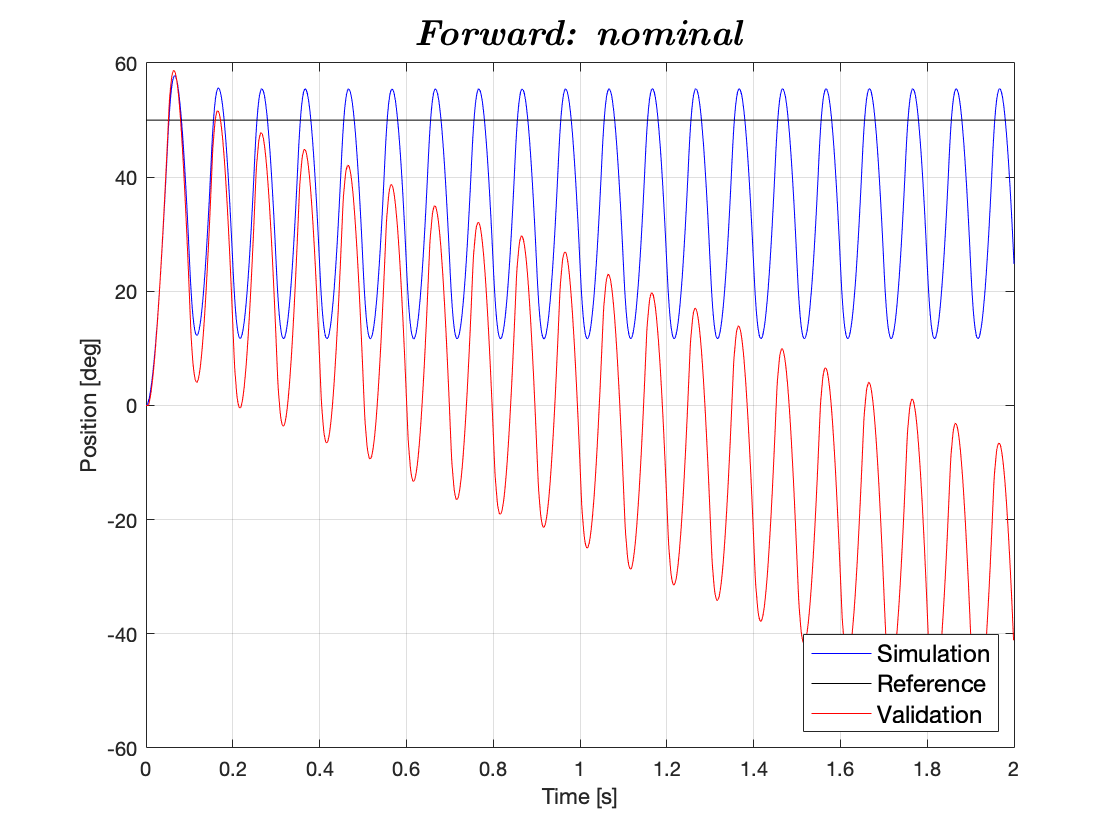

% Sampling time
T_samp = 0.05;

% PHY0
reduced.Phy0 = 1 + reduced.A0*T_samp;
% GAMMA0
reduced.Gamma0 = reduced.B0*T_samp;
% HO
reduced.H0 = reduced.C0;
% J0
reduced.J0 = reduced.D0;

% Discrete Reduced state observer
set_param('Disc_ReducedOrder/Discrete Reduced Order Observer','A','reduced.Phy0','B','reduced.Gamma0','C','reduced.H0','D','reduced.J0','SampleTime','T_samp');

% Run simulation
sim('Disc_ReducedOrder');
 
% Extract simulation results
reduced_nomfor_50ms.t = simres.time; % time vector 
reduced_nomfor_50ms.thl = simres.signals(1).values(:,1); % load position
reduced_nomfor_50ms.thl_Ref = simres.signals(1).values(:,2); % load position reference

% Plot simulation results
figure
plot(reduced_nomfor_50ms.t, reduced_nomfor_50ms.thl, 'b');
hold on;
plot(reduced_nomfor_50ms.t, reduced_nomfor_50ms.thl_Ref, 'k');
hold on;
plot(nomfor50.time(1:2000), nomfor50.signals.values(1:2000,1), 'r');
ylabel('Position [deg]');
xlabel('Time [s]');
grid on;
tit = '\textbf{\textit{Forward: nominal}}';
title(tit,'interpreter','latex');
ax = gca;
ax.TitleFontSizeMultiplier = 1.8;
lgd = legend('Simulation', 'Reference', 'Validation', 'Location', 'southeast');
lgd.FontSize = 12;

## Reduced-Order Observer [Continuos-case]

## 2.1.2.5 INTEGRAL

% Augmented state-space
robust.Ae = [0 state_space.C;[0;0] state_space.A];
robust.Be = [0;state_space.B];
robust.Ce = [0 state_space.C];

% Real and imaginary parts of the eigenvalues
robust.sigma = -nominal.delta*nominal.wn;
robust.wd = nominal.wn*sqrt(1-nominal.delta^2);

% Pole placement
robust.poles = [2*robust.sigma + 1i*robust.wd, 2*robust.sigma - 1i*robust.wd, 2*robust.sigma];

% Ke
robust.Ke = place(robust.Ae,robust.Be,robust.poles);
robust.Ki = robust.Ke(1);
robust.K = robust.Ke(1,2:3);


#### Simulation results [$$40\degree $$] 

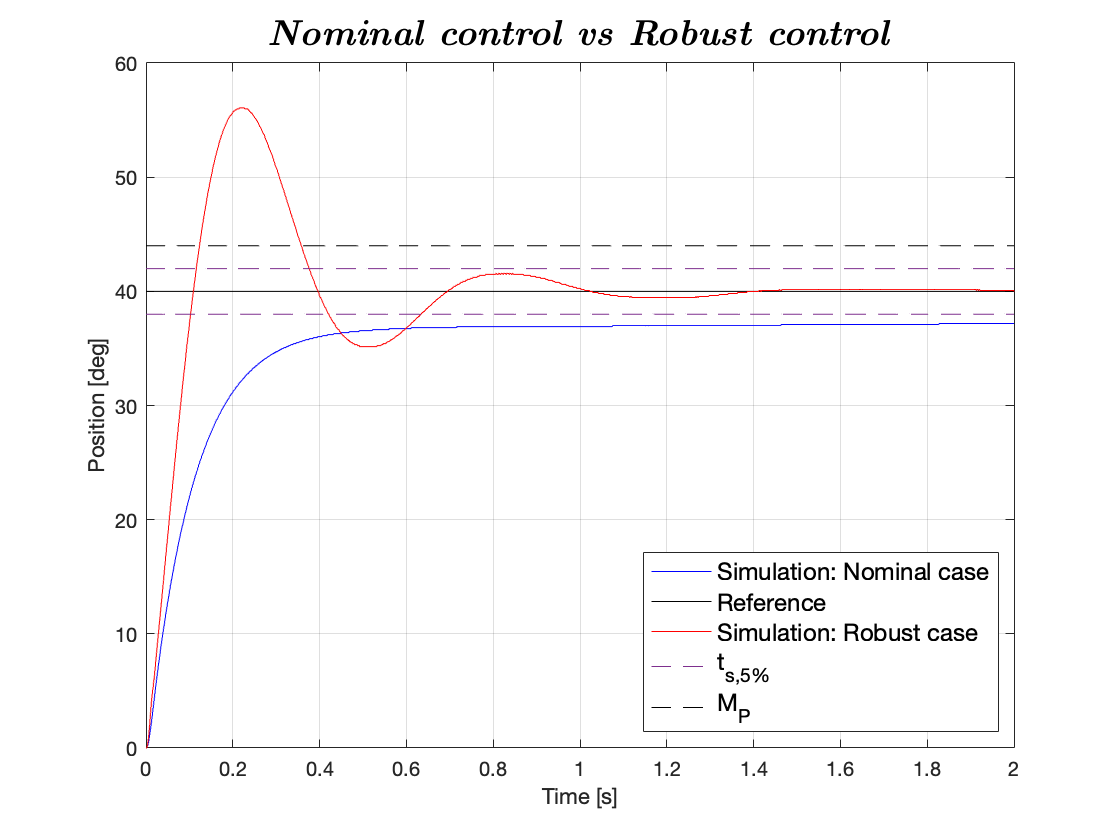

% Step
set_param('Cont_ReducedOrder/Step','Time','0','Before','0','After','40');

% Controller
set_param('Cont_ReducedOrder/Controller/State feed-forward gain','Gain','nominal.N_x');
set_param('Cont_ReducedOrder/Controller/Input feed-forward gain','Gain','nominal.N_u');
set_param('Cont_ReducedOrder/Controller/State feedback gain','Gain','robust.K','Multiplication','Matrix(K*u)');
set_param('Cont_ReducedOrder/Enable Integral','Value','1'); % Integral
set_param('Cont_ReducedOrder/Controller/Ki','Gain','robust.Ki'); % Ki

% Continuos Reduced state observer
set_param('Cont_ReducedOrder/Reduced Order Observer','A','reduced.A0','B','reduced.B0','C','reduced.C0','D','reduced.D0');

% Run simulation
sim('Cont_ReducedOrder');
 
% Extract simulation results
reducedint40.t = simres.time; % time vector 
reducedint40.thl = simres.signals(1).values(:,1); % load position
reducedint40.thl_Ref = simres.signals(1).values(:,2); % load position reference

ts5_low = [];
ts5_high = [];
Mp = [];
time = [];
j = 1;
for i=0:0.001:2
    ts5_high(j) = reducedint40.thl(length(reducedint40.thl))+0.05*reducedint40.thl(length(reducedint40.thl));
    ts5_low(j) = reducedint40.thl(length(reducedint40.thl))-0.05*reducedint40.thl(length(reducedint40.thl));
    Mp(j) = reducedint40.thl(length(reducedint40.thl))+0.1*reducedint40.thl(length(reducedint40.thl));
    time(j) = i;
    j = j + 1;
end

% Plot simulation results
figure
plot(reducednom40.t, reducednom40.thl, 'b');
hold on;
plot(reducedint40.t, reducedint40.thl_Ref, 'k');
hold on;
plot(reducedint40.t, reducedint40.thl, 'r');
hold on;
plot(time, ts5_low, 'color', '#7E2F8E', 'LineStyle', '--');
hold on;
plot(time, ts5_high, 'color', '#7E2F8E', 'LineStyle', '--');
hold on;
plot(time, Mp, '--k');
ylabel('Position [deg]');
xlabel('Time [s]');
grid on;
tit = '\textbf{\textit{Nominal control vs Robust control}}';
title(tit,'interpreter','latex');
ax = gca;
ax.TitleFontSizeMultiplier = 1.8;
lgd = legend('Simulation: Nominal case', 'Reference', 'Simulation: Robust case', 't_{s,5%}', '', 'M_P', 'Location', 'southeast');
lgd.FontSize = 12;

#### Simulation results [$$70\degree $$] 

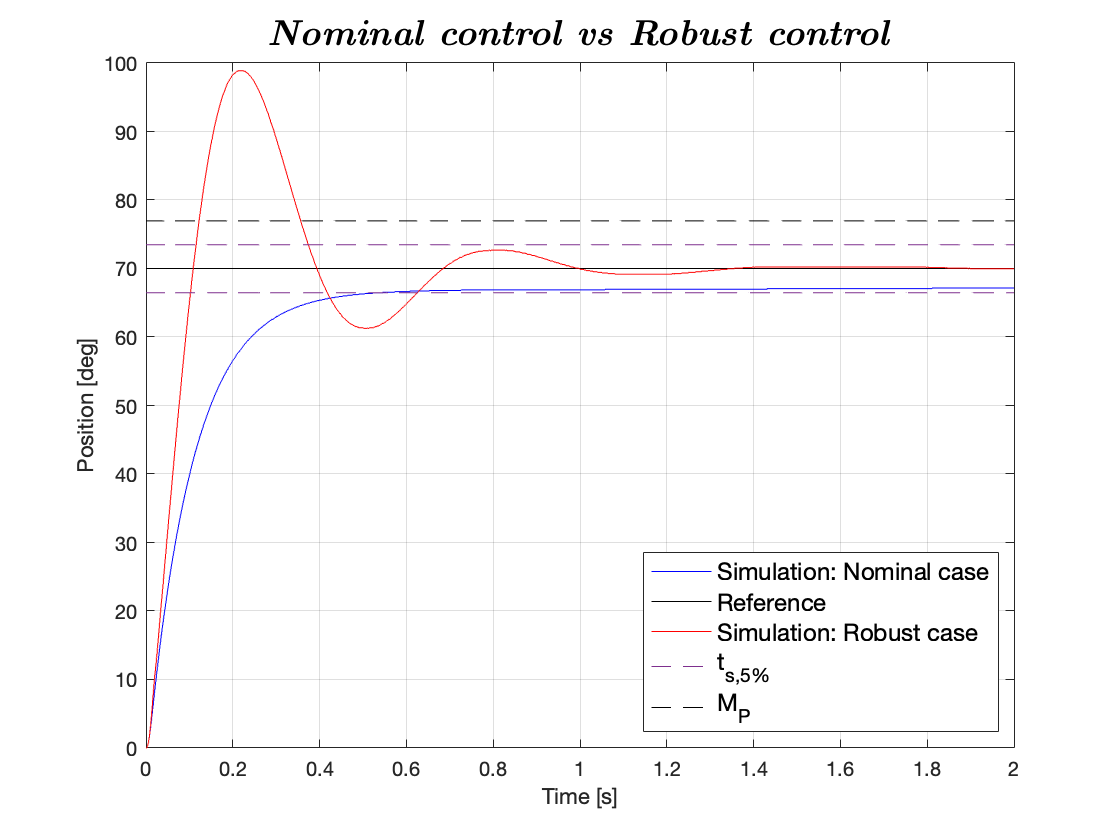

% Step
set_param('Cont_ReducedOrder/Step','Time','0','Before','0','After','70');

% Run simulation
sim('Cont_ReducedOrder');
 
% Extract simulation results
reducedint70.t = simres.time; % time vector 
reducedint70.thl = simres.signals(1).values(:,1); % load position
reducedint70.thl_Ref = simres.signals(1).values(:,2); % load position reference

ts5_low = [];
ts5_high = [];
Mp = [];
time = [];
j = 1;
for i=0:0.001:2
    ts5_high(j) = reducedint70.thl(length(reducedint70.thl))+0.05*reducedint70.thl(length(reducedint70.thl));
    ts5_low(j) = reducedint70.thl(length(reducedint70.thl))-0.05*reducedint70.thl(length(reducedint70.thl));
    Mp(j) = reducedint70.thl(length(reducedint70.thl))+0.1*reducedint70.thl(length(reducedint70.thl));
    time(j) = i;
    j = j + 1;
end

% Plot simulation results
figure
plot(reducednom70.t, reducednom70.thl, 'b');
hold on;
plot(reducedint70.t, reducedint70.thl_Ref, 'k');
hold on;
plot(reducedint70.t, reducedint70.thl, 'r');
hold on;
plot(time, ts5_low, 'color', '#7E2F8E', 'LineStyle', '--');
hold on;
plot(time, ts5_high, 'color', '#7E2F8E', 'LineStyle', '--');
hold on;
plot(time, Mp, '--k');
ylabel('Position [deg]');
xlabel('Time [s]');
grid on;
tit = '\textbf{\textit{Nominal control vs Robust control}}';
title(tit,'interpreter','latex');
ax = gca;
ax.TitleFontSizeMultiplier = 1.8;
lgd = legend('Simulation: Nominal case', 'Reference', 'Simulation: Robust case', 't_{s,5%}', '', 'M_P', 'Location', 'southeast');
lgd.FontSize = 12;

#### Simulation results [$$120\degree $$] 

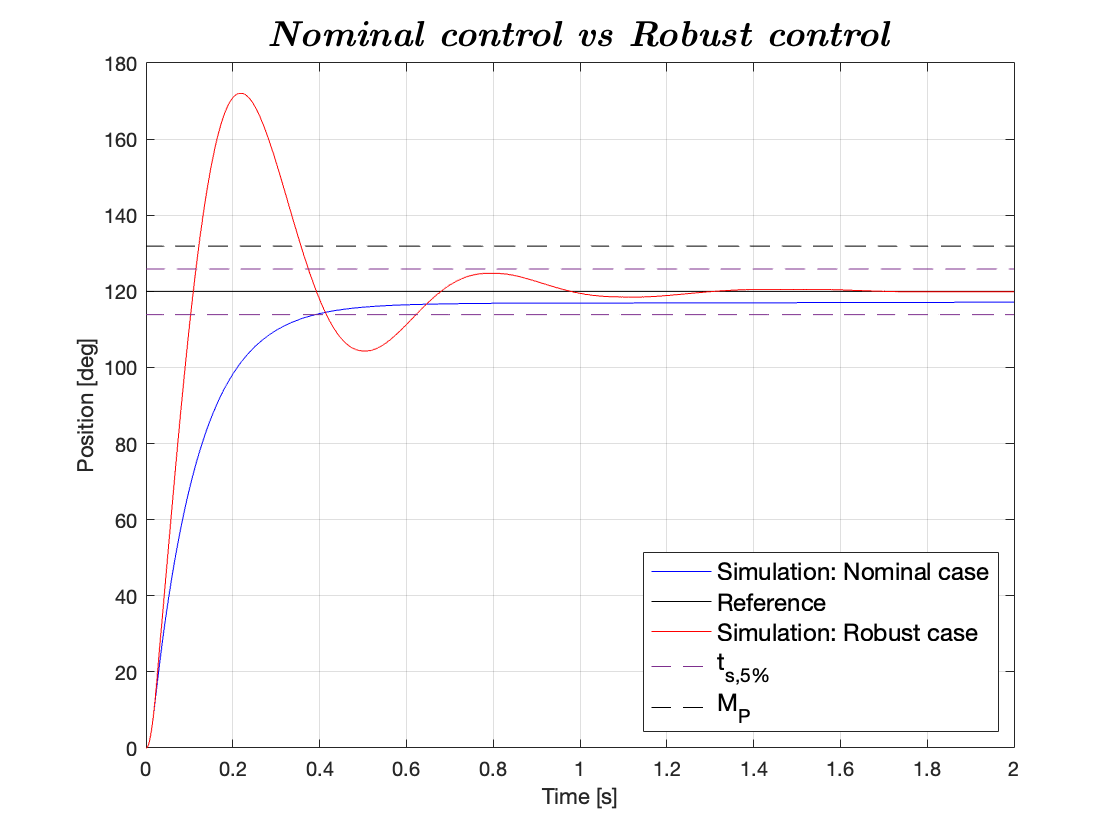

% Step
set_param('Cont_ReducedOrder/Step','Time','0','Before','0','After','120');

% Run simulation
sim('Cont_ReducedOrder');
 
% Extract simulation results
reducedint120.t = simres.time; % time vector 
reducedint120.thl = simres.signals(1).values(:,1); % load position
reducedint120.thl_Ref = simres.signals(1).values(:,2); % load position reference

ts5_low = [];
ts5_high = [];
Mp = [];
time = [];
j = 1;
for i=0:0.001:2
    ts5_high(j) = reducedint120.thl(length(reducedint120.thl))+0.05*reducedint120.thl(length(reducedint120.thl));
    ts5_low(j) = reducedint120.thl(length(reducedint120.thl))-0.05*reducedint120.thl(length(reducedint120.thl));
    Mp(j) = reducedint120.thl(length(reducedint120.thl))+0.1*reducedint120.thl(length(reducedint120.thl));
    time(j) = i;
    j = j + 1;
end

% Plot simulation results
figure
plot(reducednom120.t, reducednom120.thl, 'b');
hold on;
plot(reducedint120.t, reducedint120.thl_Ref, 'k');
hold on;
plot(reducedint120.t, reducedint120.thl, 'r');
hold on;
plot(time, ts5_low, 'color', '#7E2F8E', 'LineStyle', '--');
hold on;
plot(time, ts5_high, 'color', '#7E2F8E', 'LineStyle', '--');
hold on;
plot(time, Mp, '--k');
ylabel('Position [deg]');
xlabel('Time [s]');
grid on;
tit = '\textbf{\textit{Nominal control vs Robust control}}';
title(tit,'interpreter','latex');
ax = gca;
ax.TitleFontSizeMultiplier = 1.8;
lgd = legend('Simulation: Nominal case', 'Reference', 'Simulation: Robust case', 't_{s,5%}', '', 'M_P', 'Location', 'southeast');
lgd.FontSize = 12;

## Reduced-Order Observer [Discrete-case: Forward]

## 2.1.2.6-2.1.2.7 INTEGRAL

#### Simulation results [$$T_s = 1ms$$] 

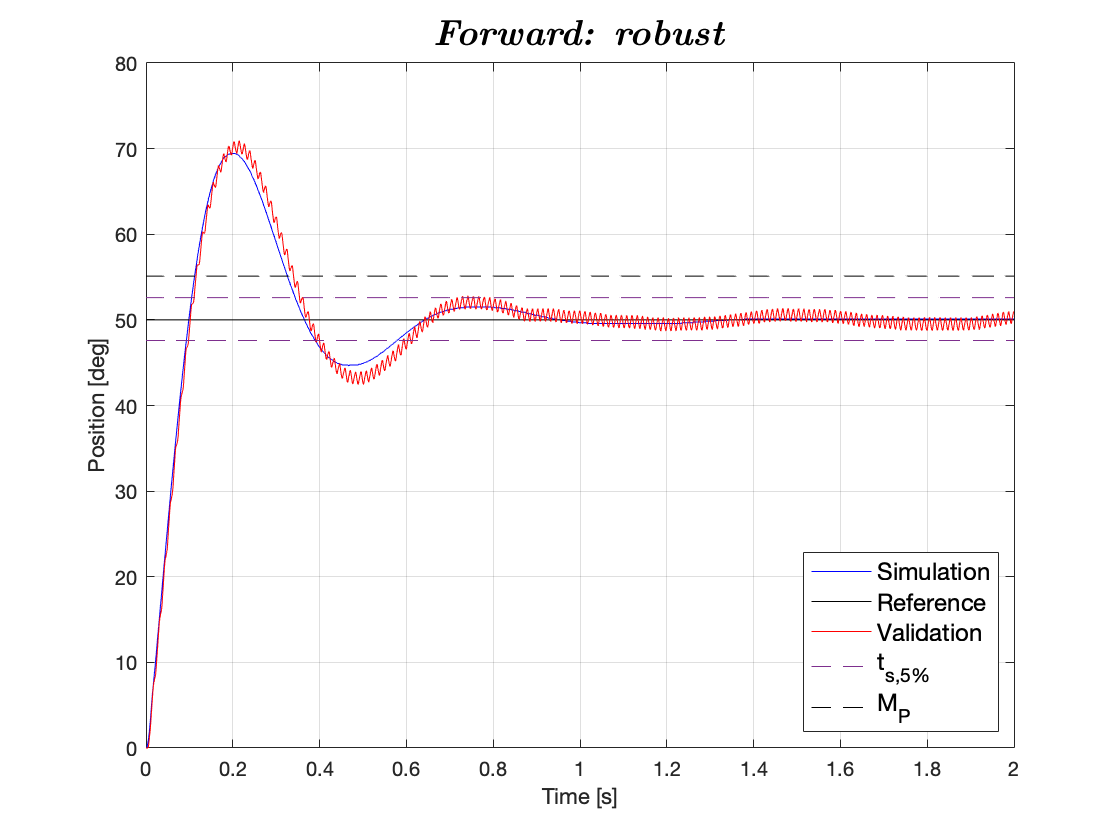

% Sampling time
T_samp = 0.001;

% PHY0
reduced.Phy0 = 1 + reduced.A0*T_samp;
% GAMMA0
reduced.Gamma0 = reduced.B0*T_samp;
% HO
reduced.H0 = reduced.C0;
% J0
reduced.J0 = reduced.D0;

% Step
set_param('Disc_ReducedOrder/Step','Time','0','Before','0','After','50');

% Controller
set_param('Disc_ReducedOrder/Controller/State feed-forward gain','Gain','nominal.N_x');
set_param('Disc_ReducedOrder/Controller/Input feed-forward gain','Gain','nominal.N_u');
set_param('Disc_ReducedOrder/Controller/State feedback gain','Gain','robust.K','Multiplication','Matrix(K*u)');
set_param('Disc_ReducedOrder/Enable Integral','Value','1'); % Integral
set_param('Disc_ReducedOrder/Controller/Ki','Gain','robust.Ki'); % Ki
set_param('Disc_ReducedOrder/Controller/Discrete-Time Integrator','IntegratorMethod','Integration: Forward Euler','SampleTime','T_samp'); % Integrator

% Discrete Reduced state observer
set_param('Disc_ReducedOrder/Discrete Reduced Order Observer','A','reduced.Phy0','B','reduced.Gamma0','C','reduced.H0','D','reduced.J0','SampleTime','T_samp');

% Run simulation
sim('Disc_ReducedOrder');

% Extract simulation results
reduced_intfor_1ms.t = simres.time; % time vector 
reduced_intfor_1ms.thl = simres.signals(1).values(:,1); % load position
reduced_intfor_1ms.thl_Ref = simres.signals(1).values(:,2); % load position reference

ts5_low = [];
ts5_high = [];
Mp = [];
time = [];
j = 1;
for i=0:0.001:2
    ts5_high(j) = reduced_intfor_1ms.thl(length(reduced_intfor_1ms.thl))+0.05*reduced_intfor_1ms.thl(length(reduced_intfor_1ms.thl));
    ts5_low(j) = reduced_intfor_1ms.thl(length(reduced_intfor_1ms.thl))-0.05*reduced_intfor_1ms.thl(length(reduced_intfor_1ms.thl));
    Mp(j) = reduced_intfor_1ms.thl(length(reduced_intfor_1ms.thl))+0.1*reduced_intfor_1ms.thl(length(reduced_intfor_1ms.thl));
    time(j) = i;
    j = j + 1;
end

% Plot simulation results
figure
plot(reduced_intfor_1ms.t, reduced_intfor_1ms.thl, 'b');
hold on;
plot(reduced_intfor_1ms.t, reduced_intfor_1ms.thl_Ref, 'k');
hold on;
plot(intfor1.time(1:2000), intfor1.signals.values(1:2000,1), 'r');
hold on;
plot(time, ts5_low, 'color', '#7E2F8E', 'LineStyle', '--');
hold on;
plot(time, ts5_high, 'color', '#7E2F8E', 'LineStyle', '--');
hold on;
plot(time, Mp, '--k');
ylabel('Position [deg]');
xlabel('Time [s]');
grid on;
tit = '\textbf{\textit{Forward: robust}}';
title(tit,'interpreter','latex');
ax = gca;
ax.TitleFontSizeMultiplier = 1.8;
lgd = legend('Simulation', 'Reference', 'Validation', 't_{s,5%}', '', 'M_P', 'Location', 'southeast');
lgd.FontSize = 12;

#### Simulation results [$$T_s = 10ms$$] 

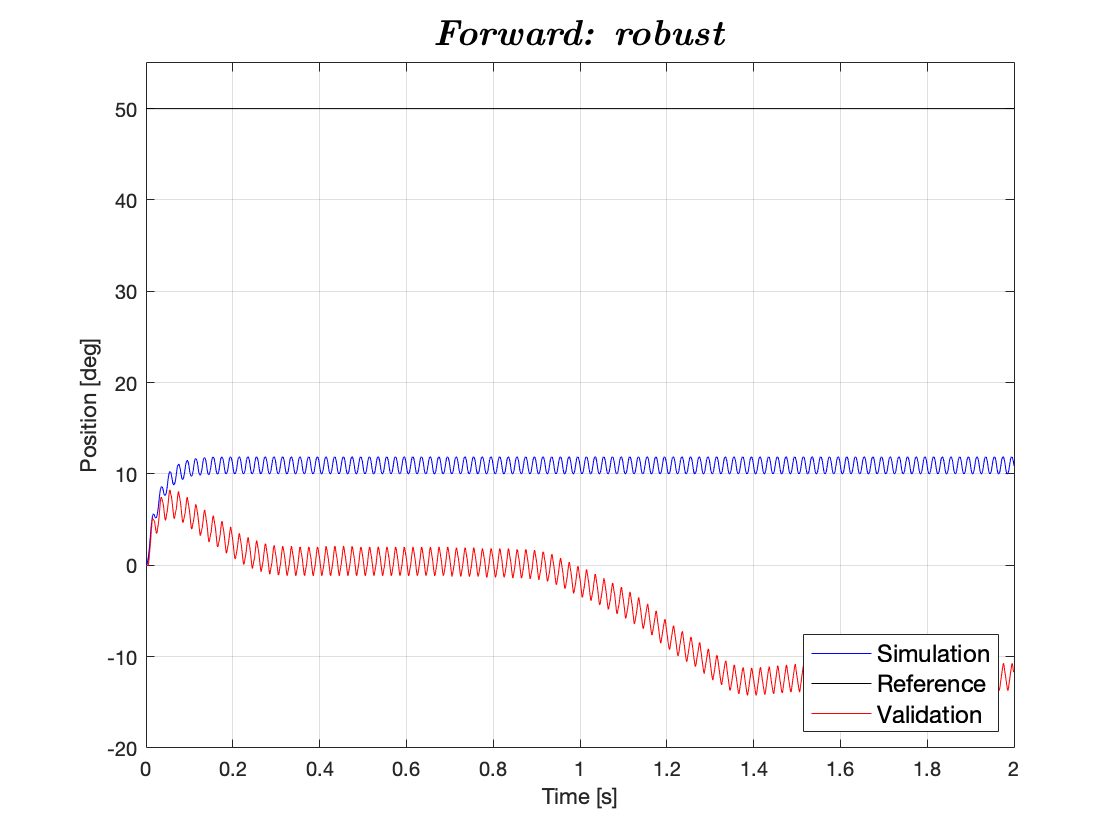

% Sampling time
T_samp = 0.01;

% PHY0
reduced.Phy0 = 1 + reduced.A0*T_samp;
% GAMMA0
reduced.Gamma0 = reduced.B0*T_samp;
% HO
reduced.H0 = reduced.C0;
% J0
reduced.J0 = reduced.D0;

set_param('Disc_ReducedOrder/Controller/Discrete-Time Integrator','IntegratorMethod','Integration: Forward Euler','SampleTime','T_samp'); % Integrator

% Discrete Reduced state observer
set_param('Disc_ReducedOrder/Discrete Reduced Order Observer','A','reduced.Phy0','B','reduced.Gamma0','C','reduced.H0','D','reduced.J0','SampleTime','T_samp');

% Run simulation
sim('Disc_ReducedOrder');

% Extract simulation results
reduced_intfor_10ms.t = simres.time; % time vector 
reduced_intfor_10ms.thl = simres.signals(1).values(:,1); % load position
reduced_intfor_10ms.thl_Ref = simres.signals(1).values(:,2); % load position reference

% Plot simulation results
figure
plot(reduced_intfor_10ms.t, reduced_intfor_10ms.thl, 'b');
hold on;
plot(reduced_intfor_10ms.t, reduced_intfor_10ms.thl_Ref, 'k');
hold on;
plot(intfor10.time(1:2000), intfor10.signals.values(1:2000,1), 'r');
ylabel('Position [deg]');
xlabel('Time [s]');
grid on;
ylim([-20,55]);
tit = '\textbf{\textit{Forward: robust}}';
title(tit,'interpreter','latex');
ax = gca;
ax.TitleFontSizeMultiplier = 1.8;
lgd = legend('Simulation', 'Reference', 'Validation', 'Location', 'southeast');
lgd.FontSize = 12;

#### Simulation results [$$T_s = 50ms$$] 

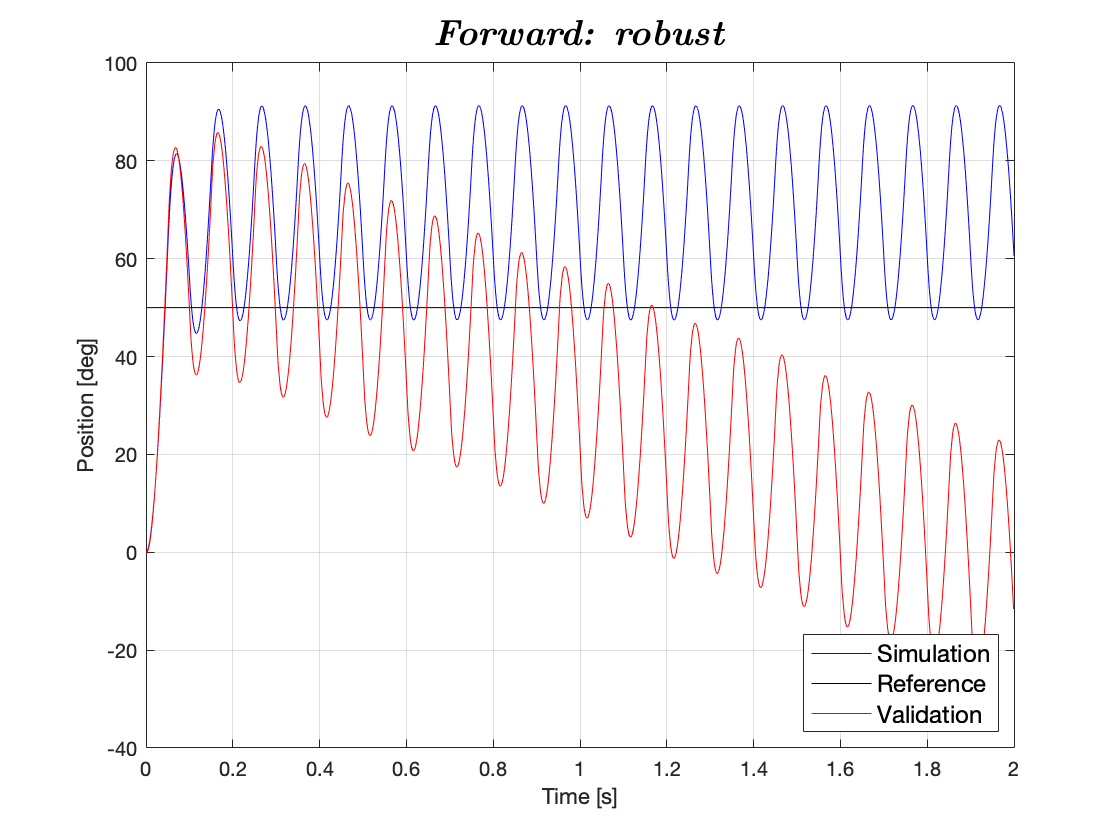

% Sampling time
T_samp = 0.05;

% PHY0
reduced.Phy0 = 1 + reduced.A0*T_samp;
% GAMMA0
reduced.Gamma0 = reduced.B0*T_samp;
% HO
reduced.H0 = reduced.C0;
% J0
reduced.J0 = reduced.D0;

set_param('Disc_ReducedOrder/Controller/Discrete-Time Integrator','IntegratorMethod','Integration: Forward Euler','SampleTime','T_samp'); % Integrator

% Discrete Reduced state observer
set_param('Disc_ReducedOrder/Discrete Reduced Order Observer','A','reduced.Phy0','B','reduced.Gamma0','C','reduced.H0','D','reduced.J0','SampleTime','T_samp');

% Run simulation
sim('Disc_ReducedOrder');

% Extract simulation results
reduced_intfor_50ms.t = simres.time; % time vector 
reduced_intfor_50ms.thl = simres.signals(1).values(:,1); % load position
reduced_intfor_50ms.thl_Ref = simres.signals(1).values(:,2); % load position reference

% Plot simulation results
figure
plot(reduced_intfor_50ms.t, reduced_intfor_50ms.thl, 'b');
hold on;
plot(reduced_intfor_50ms.t, reduced_intfor_50ms.thl_Ref, 'k');
hold on;
plot(intfor50.time(1:2000), intfor50.signals.values(1:2000,1), 'r');
ylabel('Position [deg]');
xlabel('Time [s]');
grid on;
tit = '\textbf{\textit{Forward: robust}}';
title(tit,'interpreter','latex');
ax = gca;
ax.TitleFontSizeMultiplier = 1.8;
lgd = legend('Simulation', 'Reference', 'Validation', 'Location', 'southeast');
lgd.FontSize = 12;

## Reduced-Order Observer [Discrete-case: ZOH]

## 2.1.2.8 NOMINAL

#### Simulation results [$$T_s = 1ms$$] 

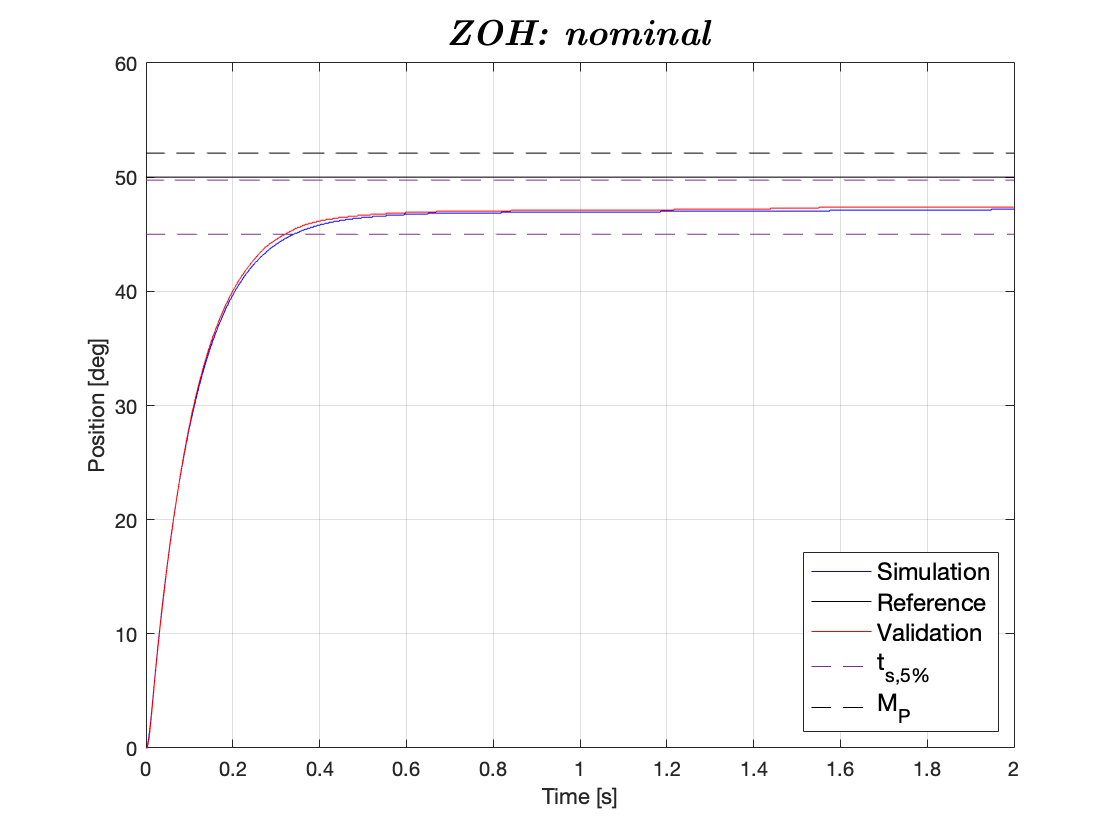

% Sampling time
T_samp = 0.001;

[reduced.Phy0,reduced.Gamma0,reduced.H0,reduced.J0] = ssdata(c2d(ss(reduced.A0,reduced.B0,reduced.C0,reduced.D0),T_samp,'zoh'));

% Step
set_param('Disc_ReducedOrder/Step','Time','0','Before','0','After','50');

% Controller
set_param('Disc_ReducedOrder/Controller/State feed-forward gain','Gain','nominal.N_x');
set_param('Disc_ReducedOrder/Controller/Input feed-forward gain','Gain','nominal.N_u');
set_param('Disc_ReducedOrder/Controller/State feedback gain','Gain','nominal.K','Multiplication','Matrix(K*u)');
set_param('Disc_ReducedOrder/Enable Integral','Value','0'); % Nominal
set_param('Disc_ReducedOrder/Controller/Ki','Gain','0'); % Ki
set_param('Disc_ReducedOrder/Controller/Discrete-Time Integrator','IntegratorMethod','Integration: Forward Euler','SampleTime','T_samp'); % Integrator

% Discrete Reduced state observer
set_param('Disc_ReducedOrder/Discrete Reduced Order Observer','A','reduced.Phy0','B','reduced.Gamma0','C','reduced.H0','D','reduced.J0','SampleTime','T_samp');

% Run simulation
sim('Disc_ReducedOrder');

% Extract simulation results
reduced_nomzoh_1ms.t = simres.time; % time vector 
reduced_nomzoh_1ms.thl = simres.signals(1).values(:,1); % load position
reduced_nomzoh_1ms.thl_Ref = simres.signals(1).values(:,2); % load position reference

ts5_low = [];
ts5_high = [];
Mp = [];
time = [];
j = 1;
for i=0:0.001:2
    ts5_high(j) = nomzoh1.signals.values(length(nomzoh1.signals.values),1)+0.05*nomzoh1.signals.values(length(nomzoh1.signals.values),1);
    ts5_low(j) = nomzoh1.signals.values(length(nomzoh1.signals.values),1)-0.05*nomzoh1.signals.values(length(nomzoh1.signals.values),1);
    Mp(j) = nomzoh1.signals.values(length(nomzoh1.signals.values),1)+0.1*nomzoh1.signals.values(length(nomzoh1.signals.values),1);
    time(j) = i;
    j = j + 1;
end

% Plot simulation results
figure
plot(reduced_nomzoh_1ms.t, reduced_nomzoh_1ms.thl, 'b');
hold on;
plot(reduced_nomzoh_1ms.t, reduced_nomzoh_1ms.thl_Ref, 'k');
hold on;
plot(nomzoh1.time(1:2000), nomzoh1.signals.values(1:2000,1), 'r');
hold on;
plot(time, ts5_low, 'color', '#7E2F8E', 'LineStyle', '--');
hold on;
plot(time, ts5_high, 'color', '#7E2F8E', 'LineStyle', '--');
hold on;
plot(time, Mp, '--k');
ylabel('Position [deg]');
xlabel('Time [s]');
grid on;
tit = '\textbf{\textit{ZOH: nominal}}';
title(tit,'interpreter','latex');
ax = gca;
ax.TitleFontSizeMultiplier = 1.8;
lgd = legend('Simulation', 'Reference', 'Validation', 't_{s,5%}', '', 'M_P', 'Location', 'southeast');
lgd.FontSize = 12;

#### Simulation results [$$T_s = 10ms$$] 

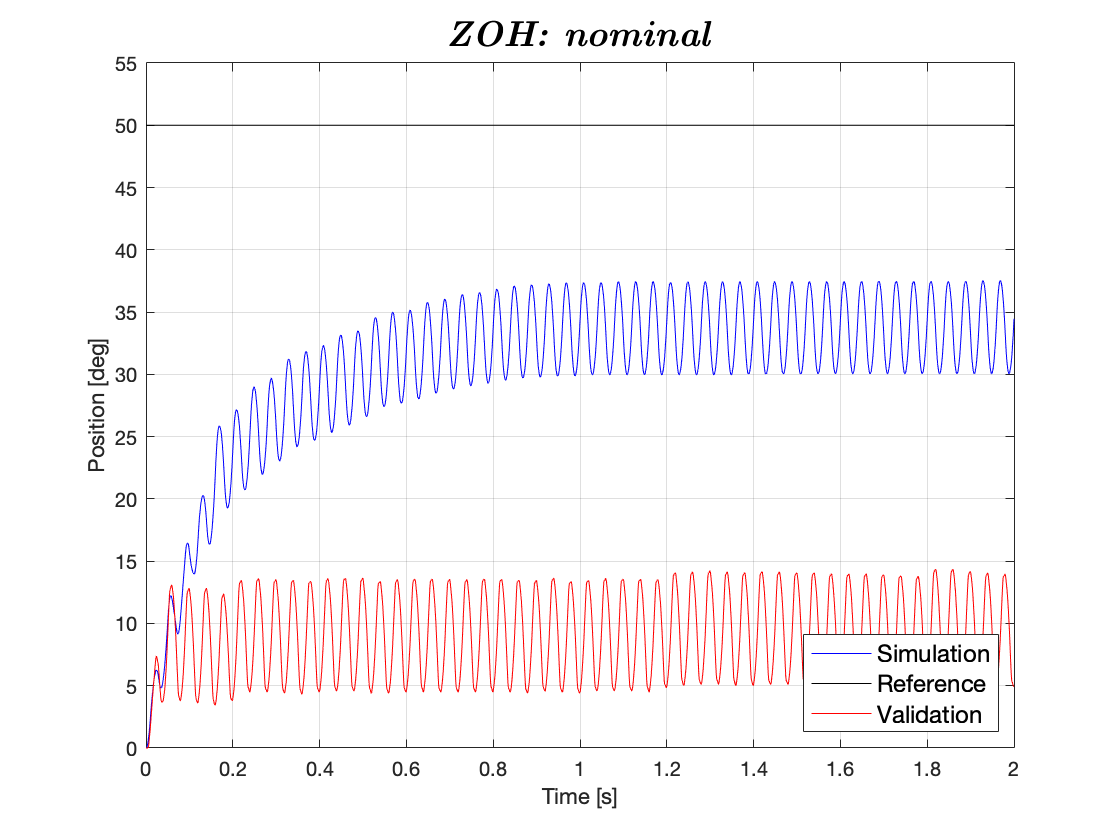

% Sampling time
T_samp = 0.01;

[reduced.Phy0,reduced.Gamma0,reduced.H0,reduced.J0] = ssdata(c2d(ss(reduced.A0,reduced.B0,reduced.C0,reduced.D0),T_samp,'zoh'));

% Discrete Reduced state observer
set_param('Disc_ReducedOrder/Discrete Reduced Order Observer','A','reduced.Phy0','B','reduced.Gamma0','C','reduced.H0','D','reduced.J0','SampleTime','T_samp');

% Run simulation
sim('Disc_ReducedOrder');

% Extract simulation results
reduced_nomzoh_10ms.t = simres.time; % time vector 
reduced_nomzoh_10ms.thl = simres.signals(1).values(:,1); % load position
reduced_nomzoh_10ms.thl_Ref = simres.signals(1).values(:,2); % load position reference

% Plot simulation results
figure
plot(reduced_nomzoh_10ms.t, reduced_nomzoh_10ms.thl, 'b');
hold on;
plot(reduced_nomzoh_10ms.t, reduced_nomzoh_10ms.thl_Ref, 'k');
hold on;
plot(nomzoh10.time(1:2000), nomzoh10.signals.values(1:2000,1), 'r');
ylabel('Position [deg]');
xlabel('Time [s]');
ylim([0,55]);
grid on;
tit = '\textbf{\textit{ZOH: nominal}}';
title(tit,'interpreter','latex');
ax = gca;
ax.TitleFontSizeMultiplier = 1.8;
lgd = legend('Simulation', 'Reference', 'Validation', 'Location', 'southeast');
lgd.FontSize = 12;

#### Simulation results [$$T_s = 50ms$$] 

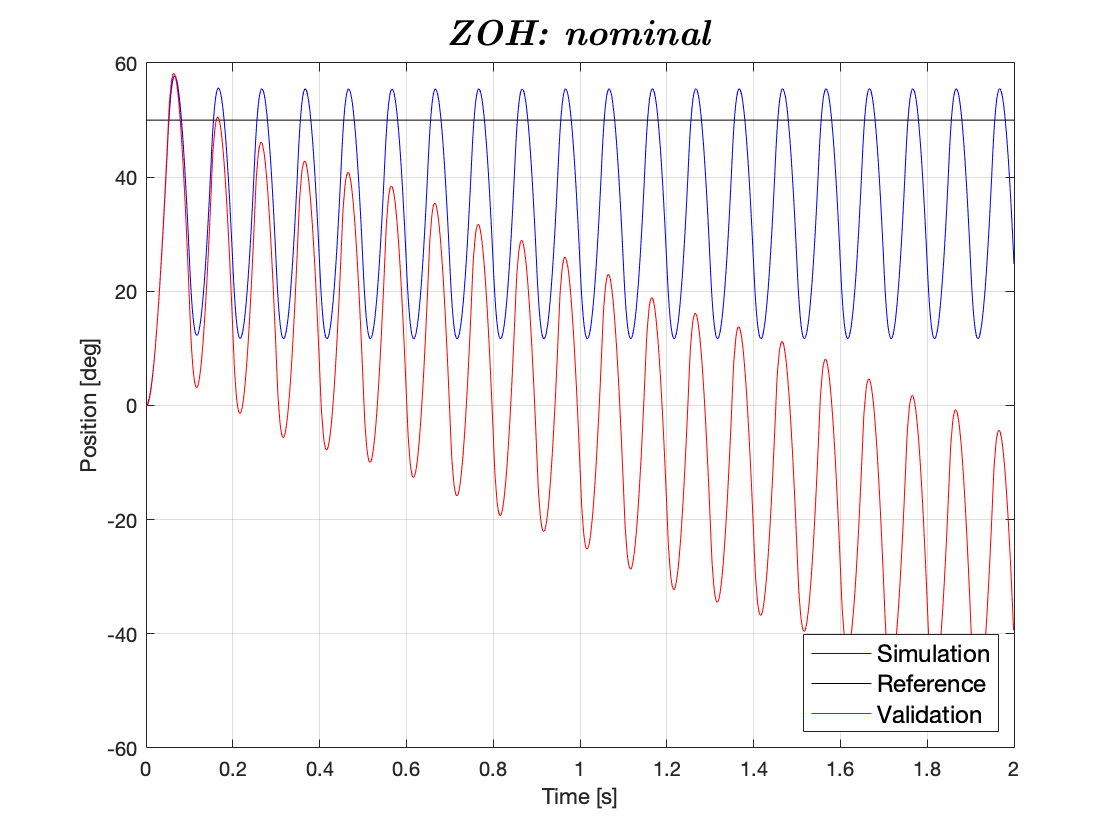

% Sampling time
T_samp = 0.05;

[reduced.Phy0,reduced.Gamma0,reduced.H0,reduced.J0] = ssdata(c2d(ss(reduced.A0,reduced.B0,reduced.C0,reduced.D0),T_samp,'zoh'));

% Discrete Reduced state observer
set_param('Disc_ReducedOrder/Discrete Reduced Order Observer','A','reduced.Phy0','B','reduced.Gamma0','C','reduced.H0','D','reduced.J0','SampleTime','T_samp');

% Run simulation
sim('Disc_ReducedOrder');

% Extract simulation results
reduced_nomzoh_50ms.t = simres.time; % time vector 
reduced_nomzoh_50ms.thl = simres.signals(1).values(:,1); % load position
reduced_nomzoh_50ms.thl_Ref = simres.signals(1).values(:,2); % load position reference

% Plot simulation results
figure
plot(reduced_nomzoh_50ms.t, reduced_nomzoh_50ms.thl, 'b');
hold on;
plot(reduced_nomzoh_50ms.t, reduced_nomzoh_50ms.thl_Ref, 'k');
hold on;
plot(nomzoh50.time(1:2000), nomzoh50.signals.values(1:2000,1), 'r');
ylabel('Position [deg]');
xlabel('Time [s]');
grid on;
tit = '\textbf{\textit{ZOH: nominal}}';
title(tit,'interpreter','latex');
ax = gca;
ax.TitleFontSizeMultiplier = 1.8;
lgd = legend('Simulation', 'Reference', 'Validation', 'Location', 'southeast');
lgd.FontSize = 12;

## Reduced-Order Observer [Discrete-case: ZOH]

## 2.1.2.8 INTEGRAL

#### Simulation results [$$T_s = 1ms$$] 

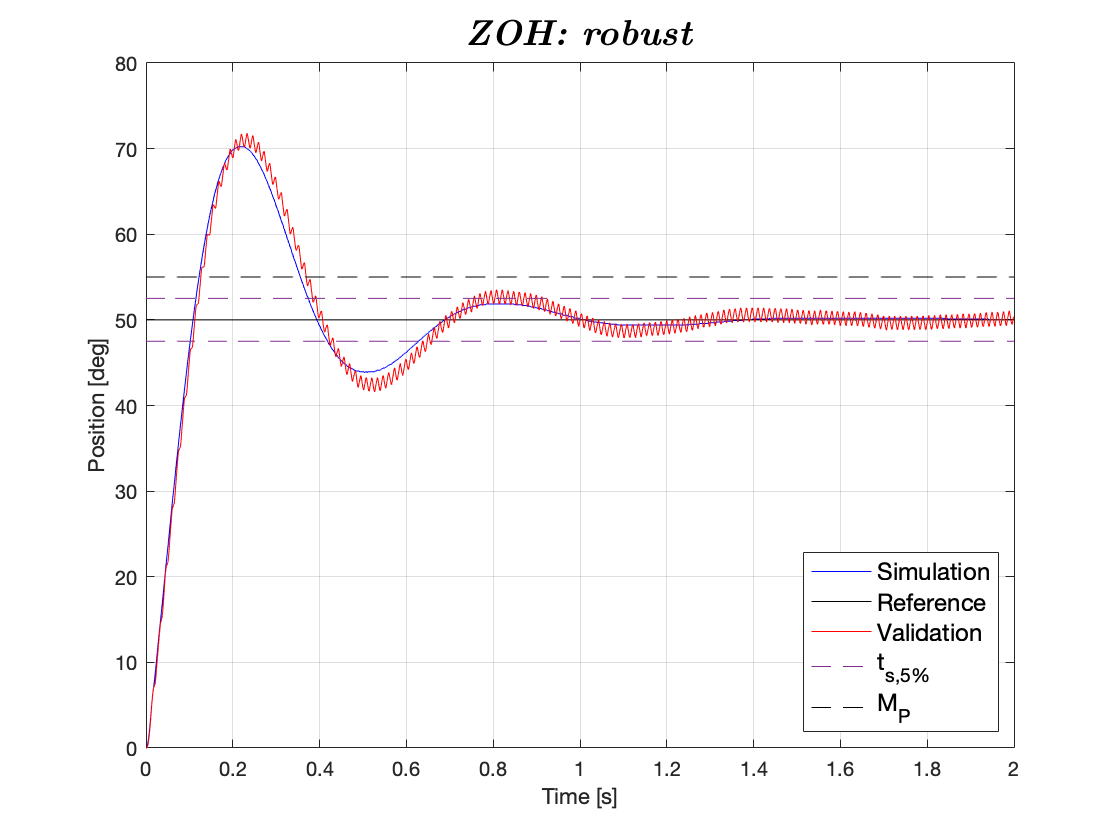

% Set parameters
set_param('Disc_ReducedOrder', ...
    'SolverType', 'Variable-step', ...
    'Solver', 'ode45', ...
    'StopTime', '2', ...
    'AlgebraicLoopMsg','none');

% Sampling time
T_samp = 0.001;

[reduced.Phy0,reduced.Gamma0,reduced.H0,reduced.J0] = ssdata(c2d(ss(reduced.A0,reduced.B0,reduced.C0,reduced.D0),T_samp,'zoh'));

% Step
set_param('Disc_ReducedOrder/Step','Time','0','Before','0','After','50');

% Controller
set_param('Disc_ReducedOrder/Controller/State feed-forward gain','Gain','nominal.N_x');
set_param('Disc_ReducedOrder/Controller/Input feed-forward gain','Gain','nominal.N_u');
set_param('Disc_ReducedOrder/Controller/State feedback gain','Gain','robust.K','Multiplication','Matrix(K*u)');
set_param('Disc_ReducedOrder/Enable Integral','Value','1'); % Integral
set_param('Disc_ReducedOrder/Controller/Ki','Gain','robust.Ki'); % Ki
set_param('Disc_ReducedOrder/Controller/Discrete-Time Integrator','IntegratorMethod','Integration: Forward Euler','SampleTime','T_samp'); % Integrator

% Discrete Reduced state observer
set_param('Disc_ReducedOrder/Discrete Reduced Order Observer','A','reduced.Phy0','B','reduced.Gamma0','C','reduced.H0','D','reduced.J0','SampleTime','T_samp');

% Run simulation
sim('Disc_ReducedOrder');

% Extract simulation results
reduced_intzoh_1ms.t = simres.time; % time vector 
reduced_intzoh_1ms.thl = simres.signals(1).values(:,1); % load position
reduced_intzoh_1ms.thl_Ref = simres.signals(1).values(:,2); % load position reference

ts5_low = [];
ts5_high = [];
Mp = [];
time = [];
j = 1;
for i=0:0.001:2
    ts5_high(j) = reduced_intzoh_1ms.thl(length(reduced_intzoh_1ms.thl))+0.05*reduced_intzoh_1ms.thl(length(reduced_intzoh_1ms.thl));
    ts5_low(j) = reduced_intzoh_1ms.thl(length(reduced_intzoh_1ms.thl))-0.05*reduced_intzoh_1ms.thl(length(reduced_intzoh_1ms.thl));
    Mp(j) = reduced_intzoh_1ms.thl(length(reduced_intzoh_1ms.thl))+0.1*reduced_intzoh_1ms.thl(length(reduced_intzoh_1ms.thl));
    time(j) = i;
    j = j + 1;
end

% Plot simulation results
figure
plot(reduced_intzoh_1ms.t, reduced_intzoh_1ms.thl, 'b');
hold on;
plot(reduced_intzoh_1ms.t, reduced_intzoh_1ms.thl_Ref, 'k');
hold on;
plot(intzoh1.time(1:2000), intzoh1.signals.values(1:2000,1), 'r');
hold on;
plot(time, ts5_low, 'color', '#7E2F8E', 'LineStyle', '--');
hold on;
plot(time, ts5_high, 'color', '#7E2F8E', 'LineStyle', '--');
hold on;
plot(time, Mp, '--k');
ylabel('Position [deg]');
xlabel('Time [s]');
grid on;
tit = '\textbf{\textit{ZOH: robust}}';
title(tit,'interpreter','latex');
ax = gca;
ax.TitleFontSizeMultiplier = 1.8;
lgd = legend('Simulation', 'Reference', 'Validation', 't_{s,5%}', '', 'M_P', 'Location', 'southeast');
lgd.FontSize = 12;

#### Simulation results [$$T_s = 10ms$$] 

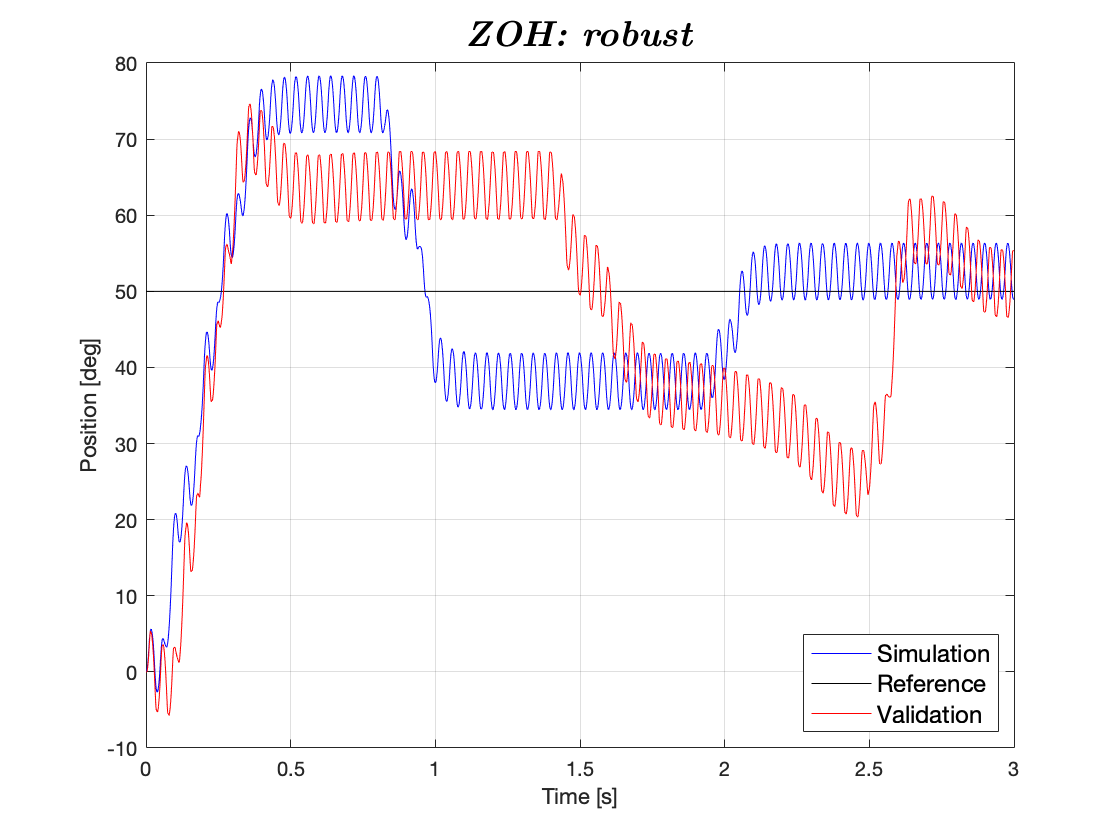

% Set parameters
set_param('Disc_ReducedOrder', ...
    'SolverType', 'Variable-step', ...
    'Solver', 'ode45', ...
    'StopTime', '3', ...
    'AlgebraicLoopMsg','none');

% Sampling time
T_samp = 0.01;

[reduced.Phy0,reduced.Gamma0,reduced.H0,reduced.J0] = ssdata(c2d(ss(reduced.A0,reduced.B0,reduced.C0,reduced.D0),T_samp,'zoh'));

% Controller
set_param('Disc_ReducedOrder/Controller/Discrete-Time Integrator','IntegratorMethod','Integration: Forward Euler','SampleTime','T_samp'); % Integrator

% Discrete Reduced state observer
set_param('Disc_ReducedOrder/Discrete Reduced Order Observer','A','reduced.Phy0','B','reduced.Gamma0','C','reduced.H0','D','reduced.J0','SampleTime','T_samp');

% Run simulation
sim('Disc_ReducedOrder');

% Extract simulation results
reduced_intzoh_10ms.t = simres.time; % time vector 
reduced_intzoh_10ms.thl = simres.signals(1).values(:,1); % load position
reduced_intzoh_10ms.thl_Ref = simres.signals(1).values(:,2); % load position reference

% Plot simulation results
figure
plot(reduced_intzoh_10ms.t, reduced_intzoh_10ms.thl, 'b');
hold on;
plot(reduced_intzoh_10ms.t, reduced_intzoh_10ms.thl_Ref, 'k');
hold on;
plot(intzoh10.time(1:3000), intzoh10.signals.values(1:3000,1), 'r');
ylabel('Position [deg]');
xlabel('Time [s]');
grid on;
tit = '\textbf{\textit{ZOH: robust}}';
title(tit,'interpreter','latex');
ax = gca;
ax.TitleFontSizeMultiplier = 1.8;
lgd = legend('Simulation', 'Reference', 'Validation', 'Location', 'southeast');
lgd.FontSize = 12;

#### Simulation results [$$T_s = 50ms$$] 

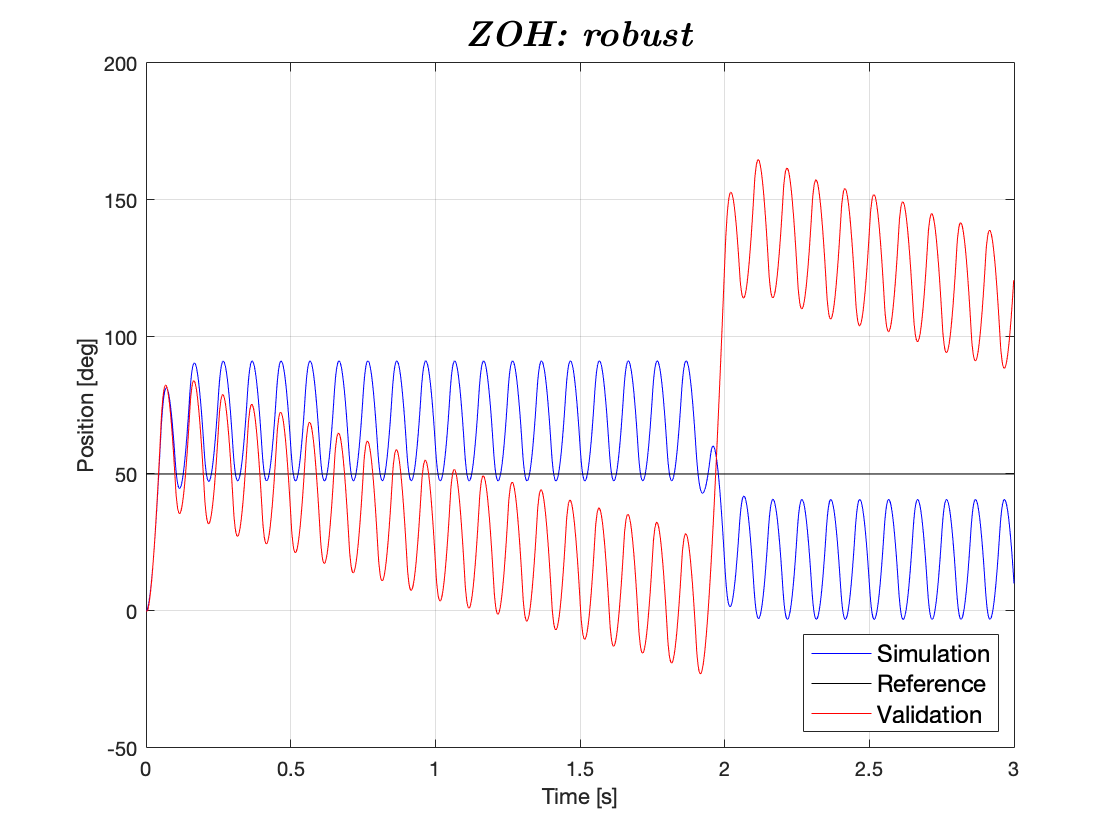

% Sampling time
T_samp = 0.05;

[reduced.Phy0,reduced.Gamma0,reduced.H0,reduced.J0] = ssdata(c2d(ss(reduced.A0,reduced.B0,reduced.C0,reduced.D0),T_samp,'zoh'));

% Controller
set_param('Disc_ReducedOrder/Controller/Discrete-Time Integrator','IntegratorMethod','Integration: Forward Euler','SampleTime','T_samp'); % Integrator

% Discrete Reduced state observer
set_param('Disc_ReducedOrder/Discrete Reduced Order Observer','A','reduced.Phy0','B','reduced.Gamma0','C','reduced.H0','D','reduced.J0','SampleTime','T_samp');

% Run simulation
sim('Disc_ReducedOrder');

% Extract simulation results
reduced_intzoh_50ms.t = simres.time; % time vector 
reduced_intzoh_50ms.thl = simres.signals(1).values(:,1); % load position
reduced_intzoh_50ms.thl_Ref = simres.signals(1).values(:,2); % load position reference

% Plot simulation results
figure
plot(reduced_intzoh_50ms.t, reduced_intzoh_50ms.thl, 'b');
hold on;
plot(reduced_intzoh_50ms.t, reduced_intzoh_50ms.thl_Ref, 'k');
hold on;
plot(intzoh50.time(1:3000), intzoh50.signals.values(1:3000,1), 'r');
ylabel('Position [deg]');
xlabel('Time [s]');
grid on;
tit = '\textbf{\textit{ZOH: robust}}';
title(tit,'interpreter','latex');
ax = gca;
ax.TitleFontSizeMultiplier = 1.8;
lgd = legend('Simulation', 'Reference', 'Validation', 'Location', 'southeast');
lgd.FontSize = 12;

## Reduced-Order Observer [Discrete-case: Backward]

% Sampling time
T_samp = 0.001;

% PHY0
reduced.Phy0 = inv(1 - reduced.A0*T_samp);
% GAMMA0
reduced.Gamma0 = inv(1 - reduced.A0*T_samp)*reduced.B0*T_samp;
% HO
reduced.H0 = reduced.C0*inv(1 - reduced.A0*T_samp);
% J0
reduced.J0 = reduced.D0+reduced.C0*inv(1 - reduced.A0*T_samp)*reduced.B0*T_samp;

## Reduced-Order Observer [Discrete-case: Tustin]

% Sampling time
T_samp = 0.001;

[reduced.Phy0, reduced.Gamma0, reduced.H0, reduced.J0] = ssdata(c2d(ss(reduced.A0,reduced.B0,reduced.C0,reduced.D0),T_samp,'tustin'));

# Direct digital design

## Reduced-Order Observer [Discrete]

## 2.2.1-2.2.2-2.2.3 NOMINAL

% Continuos state-Space model
state_space.T_m = (simp_model.Req*est_par.J_eq)/(mot.Kt*mot.Ke + simp_model.Req*est_par.B_eq);
state_space.K_m = (drv.dcgain*mot.Kt)/(mot.Kt*mot.Ke + simp_model.Req*est_par.B_eq);
state_space.A = [0 1;0 -1/state_space.T_m];
state_space.B = [0;state_space.K_m/(state_space.T_m*gbox.N)];
state_space.C = [1 0];
state_space.D = 0;

#### 
$$$T_s = 1ms$$$


% Sampling time
T_samp = 0.001;

% Exact discretized state-space model
[state_space.Phy1, state_space.Gamma1, state_space.H1, state_space.J1] = ssdata(c2d(ss(state_space.A, state_space.B, state_space.C, state_space.D), T_samp, 'zoh'));

% Observer eigenvalue placement
% Continuos controller tf
s = tf('s');
Cs = pid.Kp + pid.Ki/s + pid.Kd*s/(pid.sim.T_l*s + 1);
lambda_z = exp(5*min(eig(Cs))*T_samp);

% Compute L
digital_des_reduced.L = place(state_space.Phy1(2,2),state_space.Phy1(1,2),lambda_z);

% Phy0
digital_des_reduced.Phy0_1 = state_space.Phy1(2,2) - digital_des_reduced.L*state_space.Phy1(1,2);

% Gamma0
digital_des_reduced.Gamma0_1 = [state_space.Gamma1(2,1)-digital_des_reduced.L*state_space.Gamma1(1,1) (state_space.Phy1(2,2)-digital_des_reduced.L*state_space.Phy1(1,2))*digital_des_reduced.L+state_space.Phy1(2,1)-digital_des_reduced.L*state_space.Phy1(1,1)];

% H0
digital_des_reduced.H0_1 = [0;1];

% J0
digital_des_reduced.J0_1 = [0 1;0 digital_des_reduced.L];

% Nominal Nx Nu [DISCRETE]
digital_des_reduced.X = linsolve([state_space.Phy1 - eye(2),state_space.Gamma1;state_space.H1 0],[0;0;1]);
digital_des_reduced.N_x1 = digital_des_reduced.X(1:2,:);
digital_des_reduced.N_u1 = digital_des_reduced.X(3,:);

% Dominant Pole Approximation
mp = 0.1;
ts = 0.15;
digital_des_reduced.delta = log(1/mp)/(sqrt(pi*pi + log(1/mp)*log(1/mp)));
digital_des_reduced.wn = 3/(digital_des_reduced.delta*ts);

% Pole placement [DISCRETE]
digital_des_reduced.p1_cont = -digital_des_reduced.delta*digital_des_reduced.wn + 1i*digital_des_reduced.wn*sqrt(1-digital_des_reduced.delta^2);
digital_des_reduced.p1_disc = exp(digital_des_reduced.p1_cont*T_samp);
digital_des_reduced.p2_cont = conj(digital_des_reduced.p1_cont);
digital_des_reduced.p2_disc = exp(digital_des_reduced.p2_cont*T_samp);
digital_des_reduced.poles_disc = [digital_des_reduced.p1_disc digital_des_reduced.p2_disc];

% K
digital_des_reduced.K1 = place(state_space.Phy1, state_space.Gamma1, digital_des_reduced.poles_disc);

#### 
$$$T_s = 10ms$$$


% Sampling time
T_samp = 0.01;

% Exact discretized state-space model (T = 10ms)
[state_space.Phy10, state_space.Gamma10, state_space.H10, state_space.J10] = ssdata(c2d(ss(state_space.A, state_space.B, state_space.C, state_space.D), T_samp, 'zoh'));

% Observer eigenvalue placement
% Continuos controller tf
s = tf('s');
Cs = pid.Kp + pid.Ki/s + pid.Kd*s/(pid.sim.T_l*s + 1);
lambda_z = exp(5*min(eig(Cs))*T_samp);

% Compute L
digital_des_reduced.L = place(state_space.Phy10(2,2),state_space.Phy10(1,2),lambda_z);

% Phy0
digital_des_reduced.Phy0_10 = state_space.Phy10(2,2) - digital_des_reduced.L*state_space.Phy10(1,2);

% Gamma0
digital_des_reduced.Gamma0_10 = [state_space.Gamma10(2,1)-digital_des_reduced.L*state_space.Gamma10(1,1) (state_space.Phy10(2,2)-digital_des_reduced.L*state_space.Phy10(1,2))*digital_des_reduced.L+state_space.Phy10(2,1)-digital_des_reduced.L*state_space.Phy10(1,1)];

% H0
digital_des_reduced.H0_10 = [0;1];

% J0
digital_des_reduced.J0_10 = [0 1;0 digital_des_reduced.L];

% Nominal Nx Nu [DISCRETE]
digital_des_reduced.X = linsolve([state_space.Phy10 - eye(2),state_space.Gamma10;state_space.H10 0],[0;0;1]);
digital_des_reduced.N_x10 = digital_des_reduced.X(1:2,:);
digital_des_reduced.N_u10 = digital_des_reduced.X(3,:);

% Dominant Pole Approximation
mp = 0.1;
ts = 0.15;
digital_des_reduced.delta = log(1/mp)/(sqrt(pi*pi + log(1/mp)*log(1/mp)));
digital_des_reduced.wn = 3/(digital_des_reduced.delta*ts);

% Pole placement [DISCRETE]
digital_des_reduced.p1_cont = -digital_des_reduced.delta*digital_des_reduced.wn + 1i*digital_des_reduced.wn*sqrt(1-digital_des_reduced.delta^2);
digital_des_reduced.p1_disc = exp(digital_des_reduced.p1_cont*T_samp);
digital_des_reduced.p2_cont = conj(digital_des_reduced.p1_cont);
digital_des_reduced.p2_disc = exp(digital_des_reduced.p2_cont*T_samp);
digital_des_reduced.poles_disc = [digital_des_reduced.p1_disc digital_des_reduced.p2_disc];

% K
digital_des_reduced.K10 = place(state_space.Phy10, state_space.Gamma10, digital_des_reduced.poles_disc);

#### 
$$$T_s = 50ms$$$


% Sampling time
T_samp = 0.05;

% Exact discretized state-space model (T = 10ms)
[state_space.Phy50, state_space.Gamma50, state_space.H50, state_space.J50] = ssdata(c2d(ss(state_space.A, state_space.B, state_space.C, state_space.D), T_samp, 'zoh'));

% Observer eigenvalue placement
% Continuos controller tf
s = tf('s');
Cs = pid.Kp + pid.Ki/s + pid.Kd*s/(pid.sim.T_l*s + 1);
lambda_z = exp(5*min(eig(Cs))*T_samp);

% Compute L
digital_des_reduced.L = place(state_space.Phy10(2,2),state_space.Phy10(1,2),lambda_z);

% Phy0
digital_des_reduced.Phy0_50 = state_space.Phy50(2,2) - digital_des_reduced.L*state_space.Phy50(1,2);

% Gamma0
digital_des_reduced.Gamma0_50 = [state_space.Gamma50(2,1)-digital_des_reduced.L*state_space.Gamma50(1,1) (state_space.Phy50(2,2)-digital_des_reduced.L*state_space.Phy50(1,2))*digital_des_reduced.L+state_space.Phy50(2,1)-digital_des_reduced.L*state_space.Phy50(1,1)];

% H0
digital_des_reduced.H0_50 = [0;1];

% J0
digital_des_reduced.J0_50 = [0 1;0 digital_des_reduced.L];

% Nominal Nx Nu [DISCRETE]
digital_des_reduced.X = linsolve([state_space.Phy50 - eye(2),state_space.Gamma50;state_space.H50 0],[0;0;1]);
digital_des_reduced.N_x50 = digital_des_reduced.X(1:2,:);
digital_des_reduced.N_u50 = digital_des_reduced.X(3,:);

% Dominant Pole Approximation
mp = 0.1;
ts = 0.15;
digital_des_reduced.delta = log(1/mp)/(sqrt(pi*pi + log(1/mp)*log(1/mp)));
digital_des_reduced.wn = 3/(digital_des_reduced.delta*ts);

% Pole placement [DISCRETE]
digital_des_reduced.p1_cont = -digital_des_reduced.delta*digital_des_reduced.wn + 1i*digital_des_reduced.wn*sqrt(1-digital_des_reduced.delta^2);
digital_des_reduced.p1_disc = exp(digital_des_reduced.p1_cont*T_samp);
digital_des_reduced.p2_cont = conj(digital_des_reduced.p1_cont);
digital_des_reduced.p2_disc = exp(digital_des_reduced.p2_cont*T_samp);
digital_des_reduced.poles_disc = [digital_des_reduced.p1_disc digital_des_reduced.p2_disc];

% K
digital_des_reduced.K50 = place(state_space.Phy50, state_space.Gamma50, digital_des_reduced.poles_disc);

#### Simulation results [$$T_s = 1ms$$] 

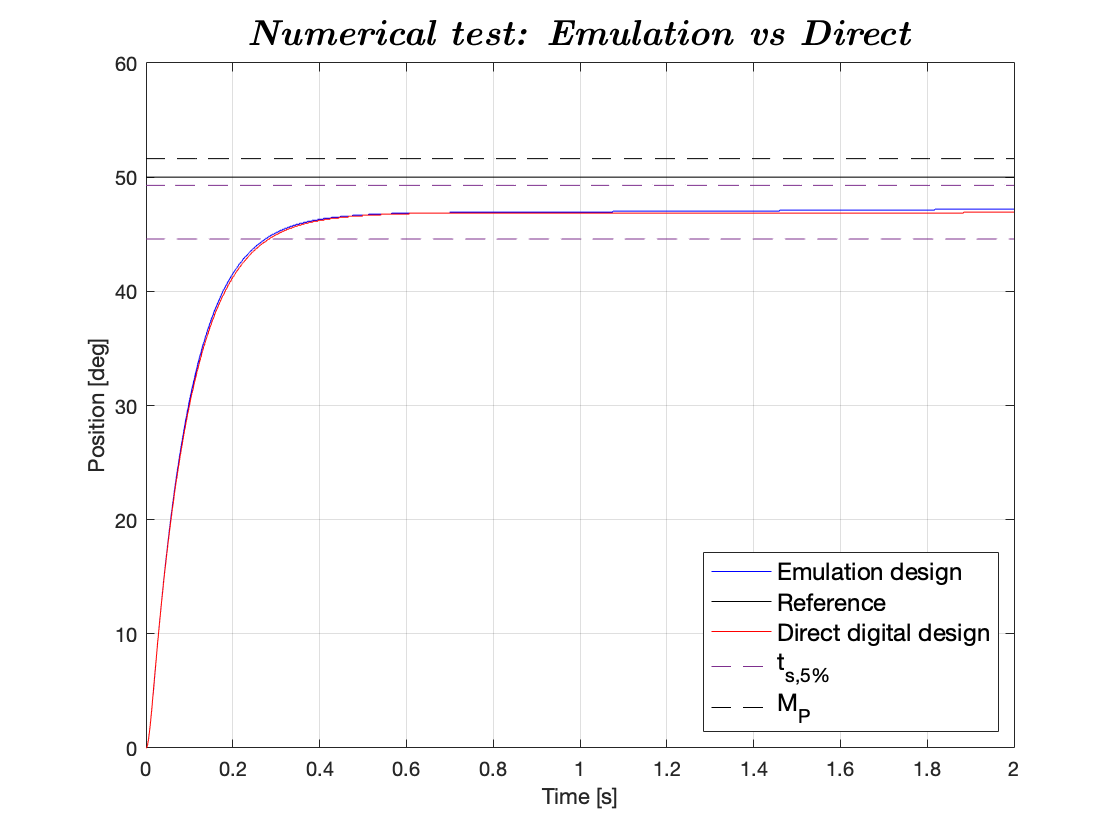

% Sampling time
T_samp = 0.001;

% Open Simulink model
open_system('Simulink/Disc_ReducedOrder.slx');

% Set parameters
set_param('Disc_ReducedOrder', ...
    'SolverType', 'Variable-step', ...
    'Solver', 'ode45', ...
    'StopTime', '2', ...
    'AlgebraicLoopMsg','none');

% Step
set_param('Disc_ReducedOrder/Step','Time','0','Before','0','After','50');

% Controller
set_param('Disc_ReducedOrder/Controller/State feed-forward gain','Gain','digital_des_reduced.N_x1');
set_param('Disc_ReducedOrder/Controller/Input feed-forward gain','Gain','digital_des_reduced.N_u1');
set_param('Disc_ReducedOrder/Controller/State feedback gain','Gain','digital_des_reduced.K1','Multiplication','Matrix(K*u)');
set_param('Disc_ReducedOrder/Enable Integral','Value','0'); % Nominal
set_param('Disc_ReducedOrder/Controller/Ki','Gain','0'); % Ki
set_param('Disc_ReducedOrder/Controller/Discrete-Time Integrator','IntegratorMethod','Integration: Forward Euler','SampleTime','T_samp'); % Integrator

% Discrete Reduced state observer
set_param('Disc_ReducedOrder/Discrete Reduced Order Observer','A','digital_des_reduced.Phy0_1','B','digital_des_reduced.Gamma0_1','C','digital_des_reduced.H0_1','D','digital_des_reduced.J0_1','SampleTime','T_samp');

% Run simulation
sim('Disc_ReducedOrder');
 
% Extract simulation results
direct_nomzoh_1ms.t = simres.time; % time vector 
direct_nomzoh_1ms.thl = simres.signals(1).values(:,1); % load position
direct_nomzoh_1ms.thl_Ref = simres.signals(1).values(:,2); % load position reference

ts5_low = [];
ts5_high = [];
Mp = [];
time = [];
j = 1;
for i=0:0.001:2
    ts5_high(j) = direct_nomzoh_1ms.thl(length(direct_nomzoh_1ms.thl))+0.05*direct_nomzoh_1ms.thl(length(direct_nomzoh_1ms.thl));
    ts5_low(j) = direct_nomzoh_1ms.thl(length(direct_nomzoh_1ms.thl))-0.05*direct_nomzoh_1ms.thl(length(direct_nomzoh_1ms.thl));
    Mp(j) = direct_nomzoh_1ms.thl(length(direct_nomzoh_1ms.thl))+0.1*direct_nomzoh_1ms.thl(length(direct_nomzoh_1ms.thl));
    time(j) = i;
    j = j + 1;
end

% NUMERICAL COMPARISON
% Plot simulation results
figure
plot(reduced_nomfor_1ms.t, reduced_nomfor_1ms.thl, 'b');
hold on;
plot(direct_nomzoh_1ms.t, direct_nomzoh_1ms.thl_Ref, 'k');
hold on;
plot(direct_nomzoh_1ms.t, direct_nomzoh_1ms.thl, 'r');
hold on;
plot(time, ts5_low, 'color', '#7E2F8E', 'LineStyle', '--');
hold on;
plot(time, ts5_high, 'color', '#7E2F8E', 'LineStyle', '--');
hold on;
plot(time, Mp, '--k');
ylabel('Position [deg]');
xlabel('Time [s]');
grid on;
tit = '\textbf{\textit{Numerical test: Emulation vs Direct}}';
title(tit,'interpreter','latex');
ax = gca;
ax.TitleFontSizeMultiplier = 1.8;
lgd = legend('Emulation design', 'Reference', 'Direct digital design', 't_{s,5%}', '', 'M_P', 'Location', 'southeast');
lgd.FontSize = 12;

stepinfo(reduced_nomfor_1ms.thl, reduced_nomfor_1ms.t, 'SettlingTimeThreshold', 0.05)

ans = struct with fields:
        RiseTime: 0.2009
    SettlingTime: 0.2862
     SettlingMin: 42.5391
     SettlingMax: 47.1973
       Overshoot: 0
      Undershoot: 0
            Peak: 47.1973
        PeakTime: 1.8180


stepinfo(direct_nomzoh_1ms.thl, direct_nomzoh_1ms.t, 'SettlingTimeThreshold', 0.05)

ans = struct with fields:
        RiseTime: 0.2023
    SettlingTime: 0.2843
     SettlingMin: 42.2754
     SettlingMax: 46.9336
       Overshoot: 0
      Undershoot: 0
            Peak: 46.9336
        PeakTime: 1.8840


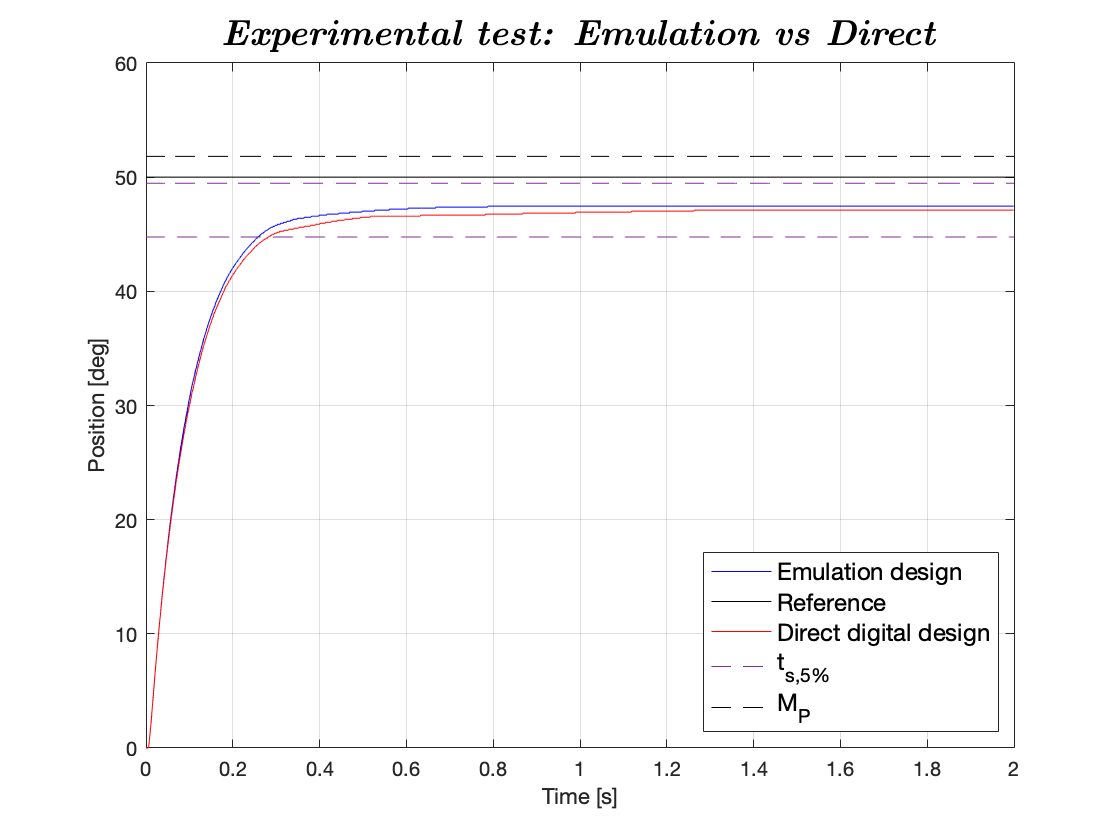

ts5_low = [];
ts5_high = [];
Mp = [];
time = [];
j = 1;
for i=0:0.001:2
    ts5_high(j) = direct_nomzoh1.signals.values(length(direct_nomzoh1.signals.values),1)+0.05*direct_nomzoh1.signals.values(length(direct_nomzoh1.signals.values),1);
    ts5_low(j) = direct_nomzoh1.signals.values(length(direct_nomzoh1.signals.values),1)-0.05*direct_nomzoh1.signals.values(length(direct_nomzoh1.signals.values),1);
    Mp(j) = direct_nomzoh1.signals.values(length(direct_nomzoh1.signals.values),1)+0.1*direct_nomzoh1.signals.values(length(direct_nomzoh1.signals.values),1);
    time(j) = i;
    j = j + 1;
end

% EXPERIMENTAL COMPARISON
% Plot simulation results
figure
plot(nomfor1.time(1:2000), nomfor1.signals.values(1:2000,1), 'b');
hold on;
plot(direct_nomzoh_1ms.t, direct_nomzoh_1ms.thl_Ref, 'k');
hold on;
plot(direct_nomzoh1.time(1:2000), direct_nomzoh1.signals.values(1:2000,1), 'r');
hold on;
plot(time, ts5_low, 'color', '#7E2F8E', 'LineStyle', '--');
hold on;
plot(time, ts5_high, 'color', '#7E2F8E', 'LineStyle', '--');
hold on;
plot(time, Mp, '--k');
ylabel('Position [deg]');
xlabel('Time [s]');
grid on;
tit = '\textbf{\textit{Experimental test: Emulation vs Direct}}';
title(tit,'interpreter','latex');
ax = gca;
ax.TitleFontSizeMultiplier = 1.8;
lgd = legend('Emulation design', 'Reference', 'Direct digital design', 't_{s,5%}', '', 'M_P', 'Location', 'southeast');
lgd.FontSize = 12;

stepinfo(nomfor1.signals.values(1:2000,1), nomfor1.time(1:2000), 'SettlingTimeThreshold', 0.05)

ans = struct with fields:
        RiseTime: 0.1948
    SettlingTime: 0.2670
     SettlingMin: 42.7148
     SettlingMax: 47.4609
       Overshoot: 0
      Undershoot: 0
            Peak: 47.4609
        PeakTime: 0.7880


stepinfo(direct_nomzoh1.signals.values(1:2000,1), direct_nomzoh1.time(1:2000), 'SettlingTimeThreshold', 0.05)

ans = struct with fields:
        RiseTime: 0.2005
    SettlingTime: 0.2822
     SettlingMin: 42.4512
     SettlingMax: 47.1094
       Overshoot: 0
      Undershoot: 0
            Peak: 47.1094
        PeakTime: 1.2630


#### Simulation results [$$T_s = 10ms$$] 

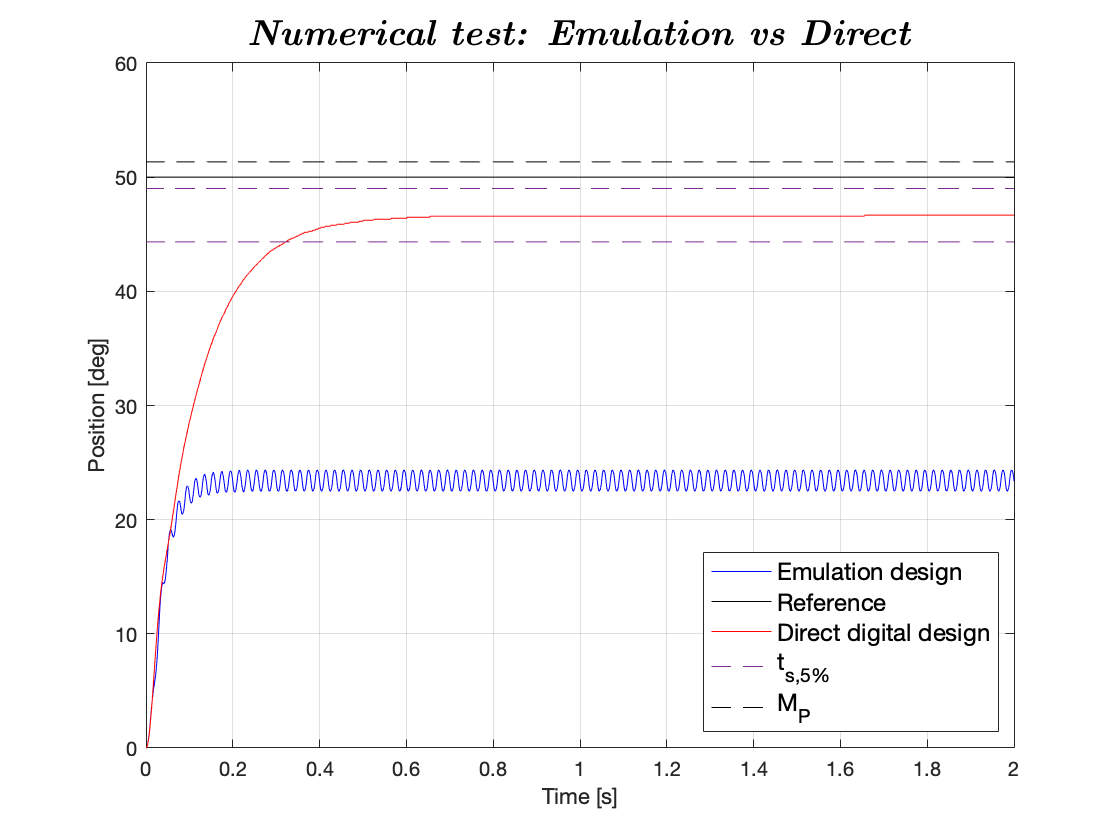

% Sampling time
T_samp = 0.01;

% Set parameters
set_param('Disc_ReducedOrder', ...
    'SolverType', 'Variable-step', ...
    'Solver', 'ode45', ...
    'StopTime', '2', ...
    'AlgebraicLoopMsg','none');

% Step
set_param('Disc_ReducedOrder/Step','Time','0','Before','0','After','50');

% Controller
set_param('Disc_ReducedOrder/Controller/State feed-forward gain','Gain','digital_des_reduced.N_x10');
set_param('Disc_ReducedOrder/Controller/Input feed-forward gain','Gain','digital_des_reduced.N_u10');
set_param('Disc_ReducedOrder/Controller/State feedback gain','Gain','digital_des_reduced.K10','Multiplication','Matrix(K*u)');
set_param('Disc_ReducedOrder/Enable Integral','Value','0'); % Nominal
set_param('Disc_ReducedOrder/Controller/Ki','Gain','0'); % Ki
set_param('Disc_ReducedOrder/Controller/Discrete-Time Integrator','IntegratorMethod','Integration: Forward Euler','SampleTime','T_samp'); % Integrator

% Discrete Reduced state observer
set_param('Disc_ReducedOrder/Discrete Reduced Order Observer','A','digital_des_reduced.Phy0_10','B','digital_des_reduced.Gamma0_10','C','digital_des_reduced.H0_10','D','digital_des_reduced.J0_10','SampleTime','T_samp');

% Run simulation
sim('Disc_ReducedOrder');
 
% Extract simulation results
direct_nomzoh_10ms.t = simres.time; % time vector 
direct_nomzoh_10ms.thl = simres.signals(1).values(:,1); % load position
direct_nomzoh_10ms.thl_Ref = simres.signals(1).values(:,2); % load position reference

ts5_low = [];
ts5_high = [];
Mp = [];
time = [];
j = 1;
for i=0:0.001:2
    ts5_high(j) = direct_nomzoh_10ms.thl(length(direct_nomzoh_10ms.thl))+0.05*direct_nomzoh_10ms.thl(length(direct_nomzoh_10ms.thl));
    ts5_low(j) = direct_nomzoh_10ms.thl(length(direct_nomzoh_10ms.thl))-0.05*direct_nomzoh_10ms.thl(length(direct_nomzoh_10ms.thl));
    Mp(j) = direct_nomzoh_10ms.thl(length(direct_nomzoh_10ms.thl))+0.1*direct_nomzoh_10ms.thl(length(direct_nomzoh_10ms.thl));
    time(j) = i;
    j = j + 1;
end

% NUMERICAL COMPARISON
% Plot simulation results
figure
plot(reduced_nomfor_10ms.t, reduced_nomfor_10ms.thl, 'b');
hold on;
plot(direct_nomzoh_10ms.t, direct_nomzoh_10ms.thl_Ref, 'k');
hold on;
plot(direct_nomzoh_10ms.t, direct_nomzoh_10ms.thl, 'r');
hold on;
plot(time, ts5_low, 'color', '#7E2F8E', 'LineStyle', '--');
hold on;
plot(time, ts5_high, 'color', '#7E2F8E', 'LineStyle', '--');
hold on;
plot(time, Mp, '--k');
ylabel('Position [deg]');
xlabel('Time [s]');
grid on;
tit = '\textbf{\textit{Numerical test: Emulation vs Direct}}';
title(tit,'interpreter','latex');
ax = gca;
ax.TitleFontSizeMultiplier = 1.8;
lgd = legend('Emulation design', 'Reference', 'Direct digital design', 't_{s,5%}', '', 'M_P', 'Location', 'southeast');
lgd.FontSize = 12;

stepinfo(reduced_nomfor_10ms.thl, reduced_nomfor_10ms.t, 'SettlingTimeThreshold', 0.05)

ans = struct with fields:
        RiseTime: 0.0622
    SettlingTime: 0.1457
     SettlingMin: 20.4785
     SettlingMax: 24.3457
       Overshoot: 4.1353
      Undershoot: 0
            Peak: 24.3457
        PeakTime: 0.2150


stepinfo(direct_nomzoh_10ms.thl, direct_nomzoh_10ms.t, 'SettlingTimeThreshold', 0.05)

ans = struct with fields:
        RiseTime: 0.2307
    SettlingTime: 0.3225
     SettlingMin: 42.0117
     SettlingMax: 46.6699
       Overshoot: 0
      Undershoot: 0
            Peak: 46.6699
        PeakTime: 1.6560


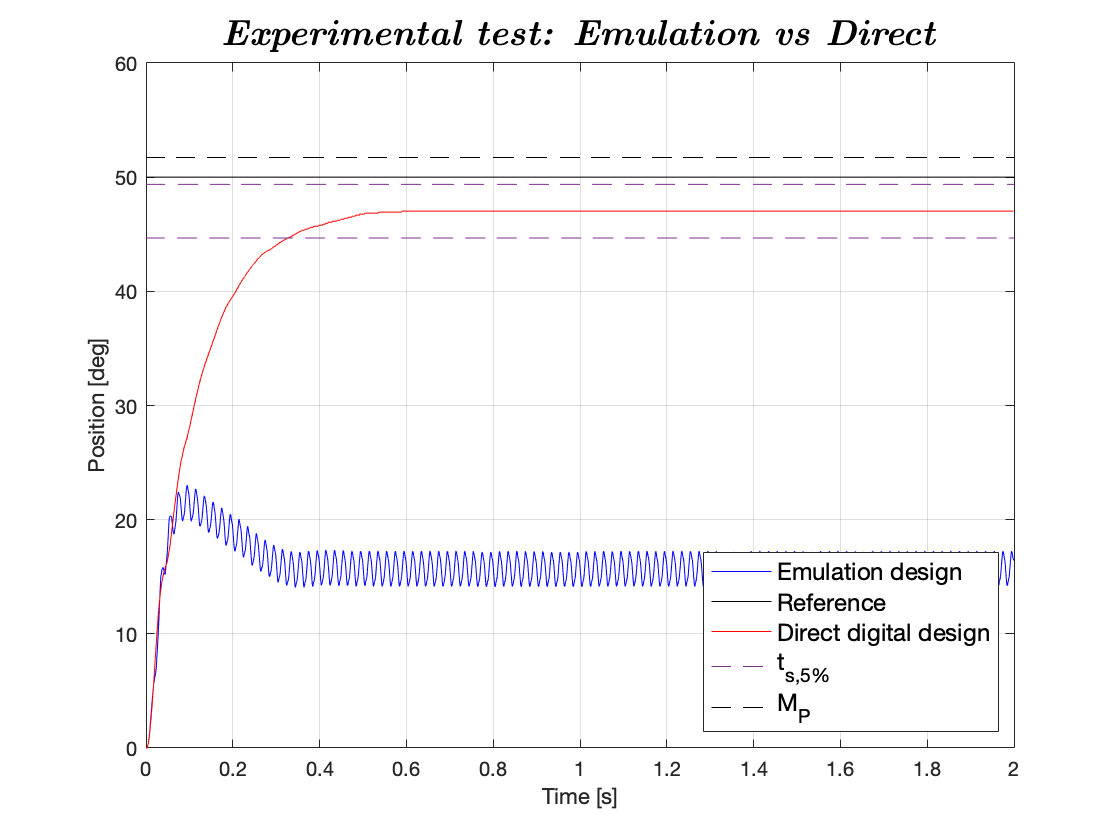

ts5_low = [];
ts5_high = [];
Mp = [];
time = [];
j = 1;
for i=0:0.001:2
    ts5_high(j) = direct_nomzoh10.signals.values(length(direct_nomzoh10.signals.values),1)+0.05*direct_nomzoh10.signals.values(length(direct_nomzoh10.signals.values),1);
    ts5_low(j) = direct_nomzoh10.signals.values(length(direct_nomzoh10.signals.values),1)-0.05*direct_nomzoh10.signals.values(length(direct_nomzoh10.signals.values),1);
    Mp(j) = direct_nomzoh10.signals.values(length(direct_nomzoh10.signals.values),1)+0.1*direct_nomzoh10.signals.values(length(direct_nomzoh10.signals.values),1);
    time(j) = i;
    j = j + 1;
end

% EXPERIMENTAL COMPARISON
% Plot simulation results
figure
plot(nomfor10_first.time(1:2000), nomfor10_first.signals.values(1:2000,1), 'b');
hold on;
plot(direct_nomzoh_10ms.t, direct_nomzoh_10ms.thl_Ref, 'k');
hold on;
plot(direct_nomzoh10.time(1:2000), direct_nomzoh10.signals.values(1:2000,1), 'r');
hold on;
plot(time, ts5_low, 'color', '#7E2F8E', 'LineStyle', '--');
hold on;
plot(time, ts5_high, 'color', '#7E2F8E', 'LineStyle', '--');
hold on;
plot(time, Mp, '--k');
ylabel('Position [deg]');
xlabel('Time [s]');
grid on;
tit = '\textbf{\textit{Experimental test: Emulation vs Direct}}';
title(tit,'interpreter','latex');
ax = gca;
ax.TitleFontSizeMultiplier = 1.8;
lgd = legend('Emulation design', 'Reference', 'Direct digital design', 't_{s,5%}', '', 'M_P', 'Location', 'southeast');
lgd.FontSize = 12;

stepinfo(direct_nomzoh10.signals.values(1:2000,1), direct_nomzoh10.time(1:2000), 'SettlingTimeThreshold', 0.05)

ans = struct with fields:
        RiseTime: 0.2306
    SettlingTime: 0.3283
     SettlingMin: 42.3633
     SettlingMax: 47.0215
       Overshoot: 0
      Undershoot: 0
            Peak: 47.0215
        PeakTime: 0.5900


#### Simulation results [$$T_s = 50ms$$] 

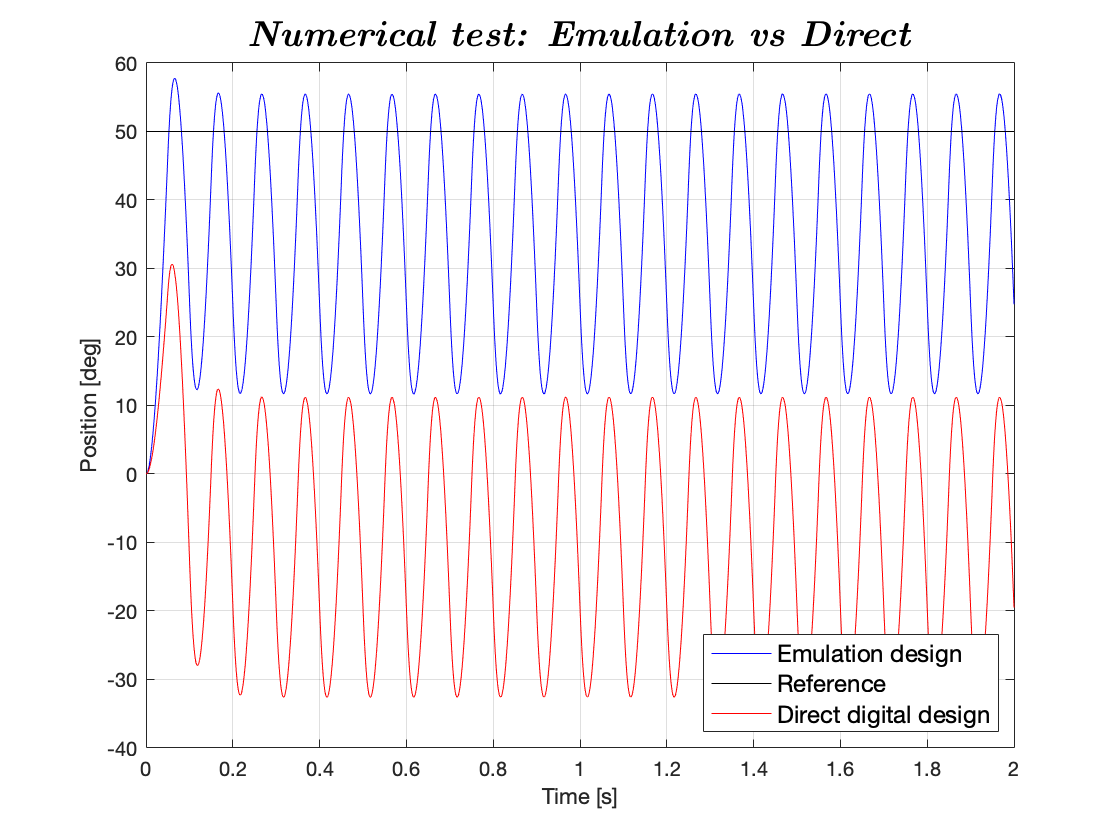

% Sampling time
T_samp = 0.05;

% Set parameters
set_param('Disc_ReducedOrder', ...
    'SolverType', 'Variable-step', ...
    'Solver', 'ode45', ...
    'StopTime', '2', ...
    'AlgebraicLoopMsg','none');

% Step
set_param('Disc_ReducedOrder/Step','Time','0','Before','0','After','50');

% Controller
set_param('Disc_ReducedOrder/Controller/State feed-forward gain','Gain','digital_des_reduced.N_x50');
set_param('Disc_ReducedOrder/Controller/Input feed-forward gain','Gain','digital_des_reduced.N_u50');
set_param('Disc_ReducedOrder/Controller/State feedback gain','Gain','digital_des_reduced.K50','Multiplication','Matrix(K*u)');
set_param('Disc_ReducedOrder/Enable Integral','Value','0'); % Nominal
set_param('Disc_ReducedOrder/Controller/Ki','Gain','0'); % Ki
set_param('Disc_ReducedOrder/Controller/Discrete-Time Integrator','IntegratorMethod','Integration: Forward Euler','SampleTime','T_samp'); % Integrator

% Discrete Reduced state observer
set_param('Disc_ReducedOrder/Discrete Reduced Order Observer','A','digital_des_reduced.Phy0_50','B','digital_des_reduced.Gamma0_50','C','digital_des_reduced.H0_50','D','digital_des_reduced.J0_50','SampleTime','T_samp');

% Run simulation
sim('Disc_ReducedOrder');
 
% Extract simulation results
direct_nomzoh_50ms.t = simres.time; % time vector 
direct_nomzoh_50ms.thl = simres.signals(1).values(:,1); % load position
direct_nomzoh_50ms.thl_Ref = simres.signals(1).values(:,2); % load position reference

% NUMERICAL COMPARISON
% Plot simulation results
figure
plot(reduced_nomfor_50ms.t, reduced_nomfor_50ms.thl, 'b');
hold on;
plot(direct_nomzoh_50ms.t, direct_nomzoh_50ms.thl_Ref, 'k');
hold on;
plot(direct_nomzoh_50ms.t, direct_nomzoh_50ms.thl, 'r');
ylabel('Position [deg]');
xlabel('Time [s]');
grid on;
tit = '\textbf{\textit{Numerical test: Emulation vs Direct}}';
title(tit,'interpreter','latex');
ax = gca;
ax.TitleFontSizeMultiplier = 1.8;
lgd = legend('Emulation design', 'Reference', 'Direct digital design', 'Location', 'southeast');
lgd.FontSize = 12;

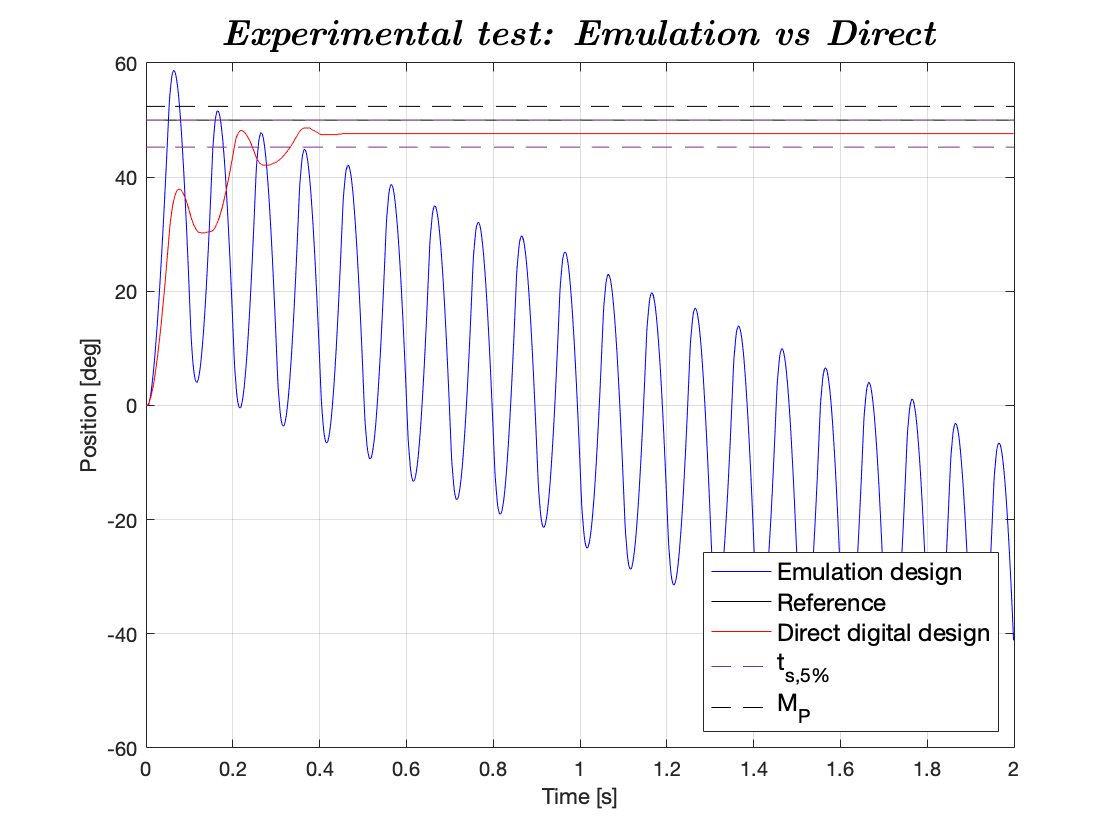

ts5_low = [];
ts5_high = [];
Mp = [];
time = [];
j = 1;
for i=0:0.001:2
    ts5_high(j) = direct_nomzoh50.signals.values(length(direct_nomzoh50.signals.values),1)+0.05*direct_nomzoh50.signals.values(length(direct_nomzoh50.signals.values),1);
    ts5_low(j) = direct_nomzoh50.signals.values(length(direct_nomzoh50.signals.values),1)-0.05*direct_nomzoh50.signals.values(length(direct_nomzoh50.signals.values),1);
    Mp(j) = direct_nomzoh50.signals.values(length(direct_nomzoh50.signals.values),1)+0.1*direct_nomzoh50.signals.values(length(direct_nomzoh50.signals.values),1);
    time(j) = i;
    j = j + 1;
end

% EXPERIMENTAL COMPARISON
% Plot simulation results
figure
plot(nomfor50.time(1:2000), nomfor50.signals.values(1:2000,1), 'b');
hold on;
plot(direct_nomzoh_50ms.t, direct_nomzoh_50ms.thl_Ref, 'k');
hold on;
plot(direct_nomzoh50.time(1:2000), direct_nomzoh50.signals.values(1:2000,1), 'r');
hold on;
plot(time, ts5_low, 'color', '#7E2F8E', 'LineStyle', '--');
hold on;
plot(time, ts5_high, 'color', '#7E2F8E', 'LineStyle', '--');
hold on;
plot(time, Mp, '--k');
ylabel('Position [deg]');
xlabel('Time [s]');
grid on;
tit = '\textbf{\textit{Experimental test: Emulation vs Direct}}';
title(tit,'interpreter','latex');
ax = gca;
ax.TitleFontSizeMultiplier = 1.8;
lgd = legend('Emulation design', 'Reference', 'Direct digital design', 't_{s,5%}', '', 'M_P', 'Location', 'southeast');
lgd.FontSize = 12;

stepinfo(direct_nomzoh50.signals.values(1:2000,1), direct_nomzoh50.time(1:2000), 'SettlingTimeThreshold', 0.05)

ans = struct with fields:
        RiseTime: 0.1784
    SettlingTime: 0.3320
     SettlingMin: 42.0996
     SettlingMax: 48.6035
       Overshoot: 2.0295
      Undershoot: 0
            Peak: 48.6035
        PeakTime: 0.3630


## Reduced-Order Observer [Discrete]

## 2.2.4 INTEGRAL

#### 
$$$T_s = 1ms$$$


% Sampling time
T_samp = 0.001;

% Augmented state-space
digital_des_reduced_int.Phie1 = [1 state_space.H1;[0;0] state_space.Phy1];
digital_des_reduced_int.Gammae1 = [0;state_space.Gamma1];

% Real and imaginary parts of the eigenvalues
digital_des_reduced_int.sigma = -digital_des_reduced.delta*digital_des_reduced.wn;
digital_des_reduced_int.wd = digital_des_reduced.wn*sqrt(1-digital_des_reduced.delta^2);

% Reduced-order Observer eigenvalue
lambda_z = exp(5*min(eig(Cs))*T_samp);

% Compute L
digital_des_reduced_int.L = place(state_space.Phy1(2,2),state_space.Phy1(1,2),lambda_z);

% Phy0
digital_des_reduced_int.Phy0_1 = state_space.Phy1(2,2) - digital_des_reduced_int.L*state_space.Phy1(1,2);

% Gamma0
digital_des_reduced_int.Gamma0_1 = [state_space.Gamma1(2,1)-digital_des_reduced_int.L*state_space.Gamma1(1,1) (state_space.Phy1(2,2)-digital_des_reduced_int.L*state_space.Phy1(1,2))*digital_des_reduced_int.L+state_space.Phy1(2,1)-digital_des_reduced_int.L*state_space.Phy1(1,1)];

% H0
digital_des_reduced_int.H0_1 = [0;1];

% J0
digital_des_reduced_int.J0_1 = [0 1;0 digital_des_reduced_int.L];

% Pole placement
digital_des_reduced_int.p1_cont = 2*digital_des_reduced_int.sigma + 1i*digital_des_reduced_int.wd;
digital_des_reduced_int.p1_disc = exp(digital_des_reduced_int.p1_cont*T_samp);
digital_des_reduced_int.p2_cont = 2*digital_des_reduced_int.sigma - 1i*digital_des_reduced_int.wd;
digital_des_reduced_int.p2_disc = exp(digital_des_reduced_int.p2_cont*T_samp);
digital_des_reduced_int.p3_cont = 2*digital_des_reduced_int.sigma;
digital_des_reduced_int.p3_disc = exp(digital_des_reduced_int.p3_cont*T_samp);
digital_des_reduced_int.poles_disc = [digital_des_reduced_int.p1_disc,digital_des_reduced_int.p2_disc,digital_des_reduced_int.p3_disc];

% Ke,Ki,K
digital_des_reduced_int.Ke = place(digital_des_reduced_int.Phie1,digital_des_reduced_int.Gammae1,digital_des_reduced_int.poles_disc);
digital_des_reduced_int.Ki1 = digital_des_reduced_int.Ke(1);
digital_des_reduced_int.K1 = digital_des_reduced_int.Ke(1,2:3);

#### 
$$$T_s = 10ms$$$


% Sampling time
T_samp = 0.01;

% Augmented state-space
digital_des_reduced_int.Phie10 = [1 state_space.H10;[0;0] state_space.Phy10];
digital_des_reduced_int.Gammae10 = [0;state_space.Gamma10];

% Real and imaginary parts of the eigenvalues
digital_des_reduced_int.sigma = -digital_des_reduced.delta*digital_des_reduced.wn;
digital_des_reduced_int.wd = digital_des_reduced.wn*sqrt(1-digital_des_reduced.delta^2);

% Reduced-order Observer eigenvalue
lambda_z = exp(5*min(eig(Cs))*T_samp);

% Compute L
digital_des_reduced_int.L = place(state_space.Phy10(2,2),state_space.Phy10(1,2),lambda_z);

% Phy0
digital_des_reduced_int.Phy0_10 = state_space.Phy10(2,2) - digital_des_reduced_int.L*state_space.Phy10(1,2);

% Gamma0
digital_des_reduced_int.Gamma0_10 = [state_space.Gamma10(2,1)-digital_des_reduced_int.L*state_space.Gamma10(1,1) (state_space.Phy10(2,2)-digital_des_reduced_int.L*state_space.Phy10(1,2))*digital_des_reduced_int.L+state_space.Phy10(2,1)-digital_des_reduced_int.L*state_space.Phy10(1,1)];

% H0
digital_des_reduced_int.H0_10 = [0;1];

% J0
digital_des_reduced_int.J0_10 = [0 1;0 digital_des_reduced_int.L];

% Pole placement
digital_des_reduced_int.p1_cont = 2*digital_des_reduced_int.sigma + 1i*digital_des_reduced_int.wd;
digital_des_reduced_int.p1_disc = exp(digital_des_reduced_int.p1_cont*T_samp);
digital_des_reduced_int.p2_cont = 2*digital_des_reduced_int.sigma - 1i*digital_des_reduced_int.wd;
digital_des_reduced_int.p2_disc = exp(digital_des_reduced_int.p2_cont*T_samp);
digital_des_reduced_int.p3_cont = 2*digital_des_reduced_int.sigma;
digital_des_reduced_int.p3_disc = exp(digital_des_reduced_int.p3_cont*T_samp);
digital_des_reduced_int.poles_disc = [digital_des_reduced_int.p1_disc,digital_des_reduced_int.p2_disc,digital_des_reduced_int.p3_disc];

% Ke,Ki,K
digital_des_reduced_int.Ke = place(digital_des_reduced_int.Phie10,digital_des_reduced_int.Gammae10,digital_des_reduced_int.poles_disc);
digital_des_reduced_int.Ki10 = digital_des_reduced_int.Ke(1);
digital_des_reduced_int.K10 = digital_des_reduced_int.Ke(1,2:3);

#### 
$$$T_s = 50ms$$$


% Sampling time
T_samp = 0.05;

% Augmented state-space
digital_des_reduced_int.Phie50 = [1 state_space.H50;[0;0] state_space.Phy50];
digital_des_reduced_int.Gammae50 = [0;state_space.Gamma50];

% Real and imaginary parts of the eigenvalues
digital_des_reduced_int.sigma = -digital_des_reduced.delta*digital_des_reduced.wn;
digital_des_reduced_int.wd = digital_des_reduced.wn*sqrt(1-digital_des_reduced.delta^2);

% Reduced-order Observer eigenvalue
lambda_z = exp(5*min(eig(Cs))*T_samp);

% Compute L
digital_des_reduced_int.L = place(state_space.Phy50(2,2),state_space.Phy50(1,2),lambda_z);

% Phy0
digital_des_reduced_int.Phy0_50 = state_space.Phy50(2,2) - digital_des_reduced_int.L*state_space.Phy50(1,2);

% Gamma0
digital_des_reduced_int.Gamma0_50 = [state_space.Gamma50(2,1)-digital_des_reduced_int.L*state_space.Gamma50(1,1) (state_space.Phy50(2,2)-digital_des_reduced_int.L*state_space.Phy50(1,2))*digital_des_reduced_int.L+state_space.Phy50(2,1)-digital_des_reduced_int.L*state_space.Phy50(1,1)];

% H0
digital_des_reduced_int.H0_50 = [0;1];

% J0
digital_des_reduced_int.J0_50 = [0 1;0 digital_des_reduced_int.L];

% Pole placement
digital_des_reduced_int.p1_cont = 2*digital_des_reduced_int.sigma + 1i*digital_des_reduced_int.wd;
digital_des_reduced_int.p1_disc = exp(digital_des_reduced_int.p1_cont*T_samp);
digital_des_reduced_int.p2_cont = 2*digital_des_reduced_int.sigma - 1i*digital_des_reduced_int.wd;
digital_des_reduced_int.p2_disc = exp(digital_des_reduced_int.p2_cont*T_samp);
digital_des_reduced_int.p3_cont = 2*digital_des_reduced_int.sigma;
digital_des_reduced_int.p3_disc = exp(digital_des_reduced_int.p3_cont*T_samp);
digital_des_reduced_int.poles_disc = [digital_des_reduced_int.p1_disc,digital_des_reduced_int.p2_disc,digital_des_reduced_int.p3_disc];

% Ke,Ki,K
digital_des_reduced_int.Ke = place(digital_des_reduced_int.Phie50,digital_des_reduced_int.Gammae50,digital_des_reduced_int.poles_disc);
digital_des_reduced_int.Ki50 = digital_des_reduced_int.Ke(1);
digital_des_reduced_int.K50 = digital_des_reduced_int.Ke(1,2:3);

#### Simulation results [$$T_s = 1ms$$] 

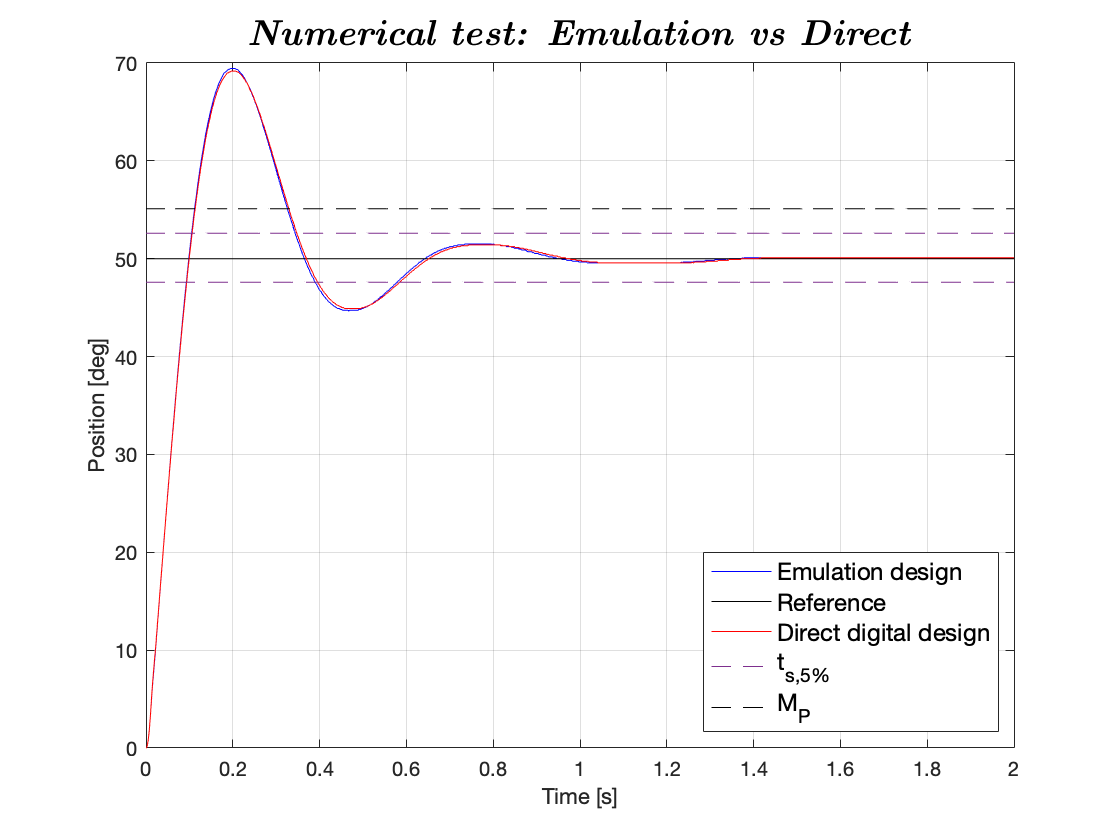

% Sampling time
T_samp = 0.001;

% Step
set_param('Disc_ReducedOrder/Step','Time','0','Before','0','After','50');

% Controller
set_param('Disc_ReducedOrder/Controller/State feed-forward gain','Gain','digital_des_reduced.N_x1');
set_param('Disc_ReducedOrder/Controller/Input feed-forward gain','Gain','digital_des_reduced.N_u1');
set_param('Disc_ReducedOrder/Controller/State feedback gain','Gain','digital_des_reduced_int.K1','Multiplication','Matrix(K*u)');
set_param('Disc_ReducedOrder/Enable Integral','Value','1'); % Integral
set_param('Disc_ReducedOrder/Controller/Ki','Gain','digital_des_reduced_int.Ki1'); % Ki
set_param('Disc_ReducedOrder/Controller/Discrete-Time Integrator','IntegratorMethod','Accumulation: Forward Euler','SampleTime','T_samp'); % Integrator

% Discrete Reduced state observer
set_param('Disc_ReducedOrder/Discrete Reduced Order Observer','A','digital_des_reduced_int.Phy0_1','B','digital_des_reduced_int.Gamma0_1','C','digital_des_reduced_int.H0_1','D','digital_des_reduced_int.J0_1','SampleTime','T_samp');

% Run simulation
sim('Disc_ReducedOrder');
 
% Extract simulation results
direct_intzoh_1ms.t = simres.time; % time vector 
direct_intzoh_1ms.thl = simres.signals(1).values(:,1); % load position
direct_intzoh_1ms.thl_Ref = simres.signals(1).values(:,2); % load position reference

ts5_low = [];
ts5_high = [];
Mp = [];
time = [];
j = 1;
for i=0:0.001:2
    ts5_high(j) = direct_intzoh_1ms.thl(length(direct_intzoh_1ms.thl))+0.05*direct_intzoh_1ms.thl(length(direct_intzoh_1ms.thl));
    ts5_low(j) = direct_intzoh_1ms.thl(length(direct_intzoh_1ms.thl))-0.05*direct_intzoh_1ms.thl(length(direct_intzoh_1ms.thl));
    Mp(j) = direct_intzoh_1ms.thl(length(direct_intzoh_1ms.thl))+0.1*direct_intzoh_1ms.thl(length(direct_intzoh_1ms.thl));
    time(j) = i;
    j = j + 1;
end

% NUMERICAL COMPARISON
% Plot simulation results
figure
plot(reduced_intfor_1ms.t, reduced_intfor_1ms.thl, 'b');
hold on;
plot(direct_nomzoh_1ms.t, direct_nomzoh_1ms.thl_Ref, 'k');
hold on;
plot(direct_intzoh_1ms.t, direct_intzoh_1ms.thl, 'r');
hold on;
plot(time, ts5_low, 'color', '#7E2F8E', 'LineStyle', '--');
hold on;
plot(time, ts5_high, 'color', '#7E2F8E', 'LineStyle', '--');
hold on;
plot(time, Mp, '--k');
ylabel('Position [deg]');
xlabel('Time [s]');
grid on;
tit = '\textbf{\textit{Numerical test: Emulation vs Direct}}';
title(tit,'interpreter','latex');
ax = gca;
ax.TitleFontSizeMultiplier = 1.8;
lgd = legend('Emulation design', 'Reference', 'Direct digital design', 't_{s,5%}', '', 'M_P', 'Location', 'southeast');
lgd.FontSize = 12;

stepinfo(reduced_intfor_1ms.thl, reduced_intfor_1ms.t, 'SettlingTimeThreshold', 0.05)

ans = struct with fields:
        RiseTime: 0.0746
    SettlingTime: 0.5785
     SettlingMin: 44.6484
     SettlingMax: 69.4336
       Overshoot: 38.5965
      Undershoot: 0
            Peak: 69.4336
        PeakTime: 0.1940


stepinfo(direct_intzoh_1ms.thl, direct_intzoh_1ms.t, 'SettlingTimeThreshold', 0.05)

ans = struct with fields:
        RiseTime: 0.0754
    SettlingTime: 0.5845
     SettlingMin: 44.9121
     SettlingMax: 69.1699
       Overshoot: 38.0702
      Undershoot: 0
            Peak: 69.1699
        PeakTime: 0.1960


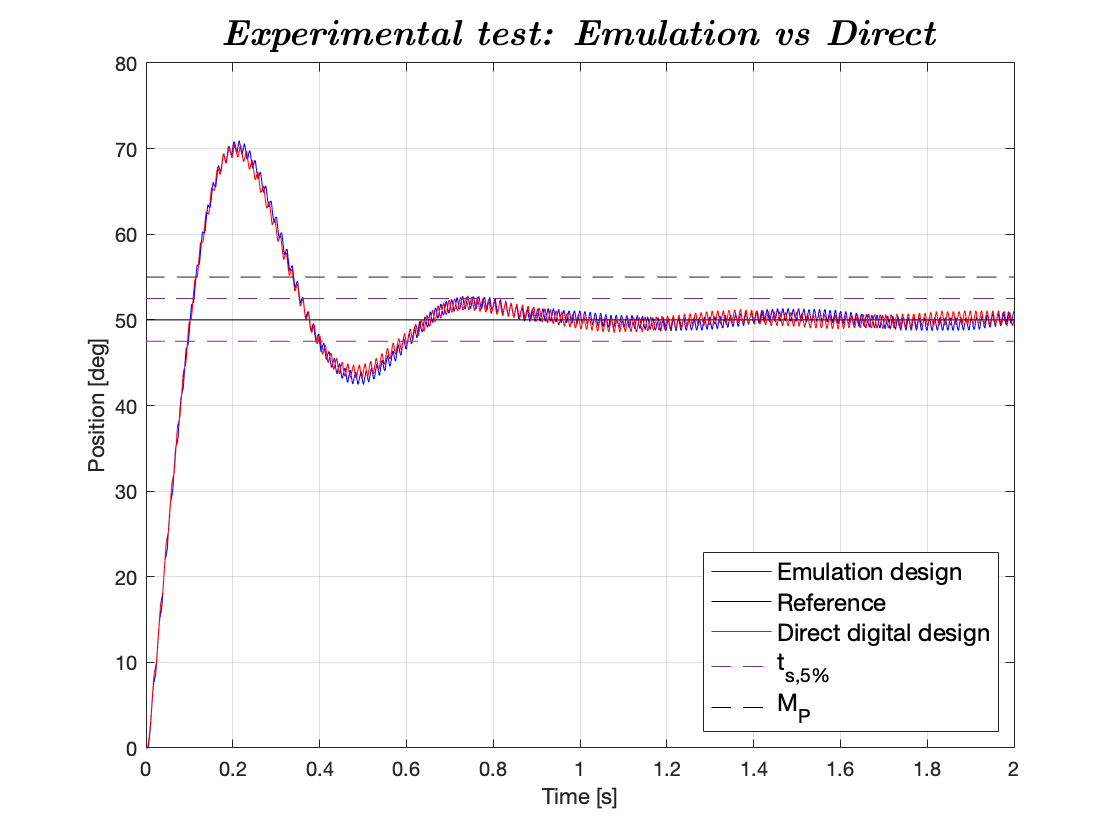

ts5_low = [];
ts5_high = [];
Mp = [];
time = [];
j = 1;
for i=0:0.001:2
    ts5_high(j) = 50+0.05*50;
    ts5_low(j) = 50-0.05*50;
    Mp(j) = 50+0.1*50;
    time(j) = i;
    j = j + 1;
end

% EXPERIMENTAL COMPARISON
% Plot simulation results
figure
plot(intfor1.time(1:2000), intfor1.signals.values(1:2000,1), 'b');
hold on;
plot(direct_nomzoh_1ms.t, direct_nomzoh_1ms.thl_Ref, 'k');
hold on;
plot(direct_intzoh1.time(1:2000), direct_intzoh1.signals.values(1:2000,1), 'r');
hold on;
plot(time, ts5_low, 'color', '#7E2F8E', 'LineStyle', '--');
hold on;
plot(time, ts5_high, 'color', '#7E2F8E', 'LineStyle', '--');
hold on;
plot(time, Mp, '--k');
ylabel('Position [deg]');
xlabel('Time [s]');
grid on;
tit = '\textbf{\textit{Experimental test: Emulation vs Direct}}';
title(tit,'interpreter','latex');
ax = gca;
ax.TitleFontSizeMultiplier = 1.8;
lgd = legend('Emulation design', 'Reference', 'Direct digital design', 't_{s,5%}', '', 'M_P', 'Location', 'southeast');
lgd.FontSize = 12;

stepinfo(intfor1.signals.values(1:2000,1), intfor1.time(1:2000), 'SettlingTimeThreshold', 0.05)

ans = struct with fields:
        RiseTime: 0.0774
    SettlingTime: 0.6262
     SettlingMin: 42.4512
     SettlingMax: 70.9277
       Overshoot: 39.1379
      Undershoot: 0
            Peak: 70.9277
        PeakTime: 0.2150


stepinfo(direct_intzoh1.signals.values(1:2000,1), direct_intzoh1.time(1:2000), 'SettlingTimeThreshold', 0.05)

ans = struct with fields:
        RiseTime: 0.0783
    SettlingTime: 0.7772
     SettlingMin: 43.1543
     SettlingMax: 70.6641
       Overshoot: 41.5493
      Undershoot: 0
            Peak: 70.6641
        PeakTime: 0.2050


#### Simulation results [$$T_s = 10ms$$] 

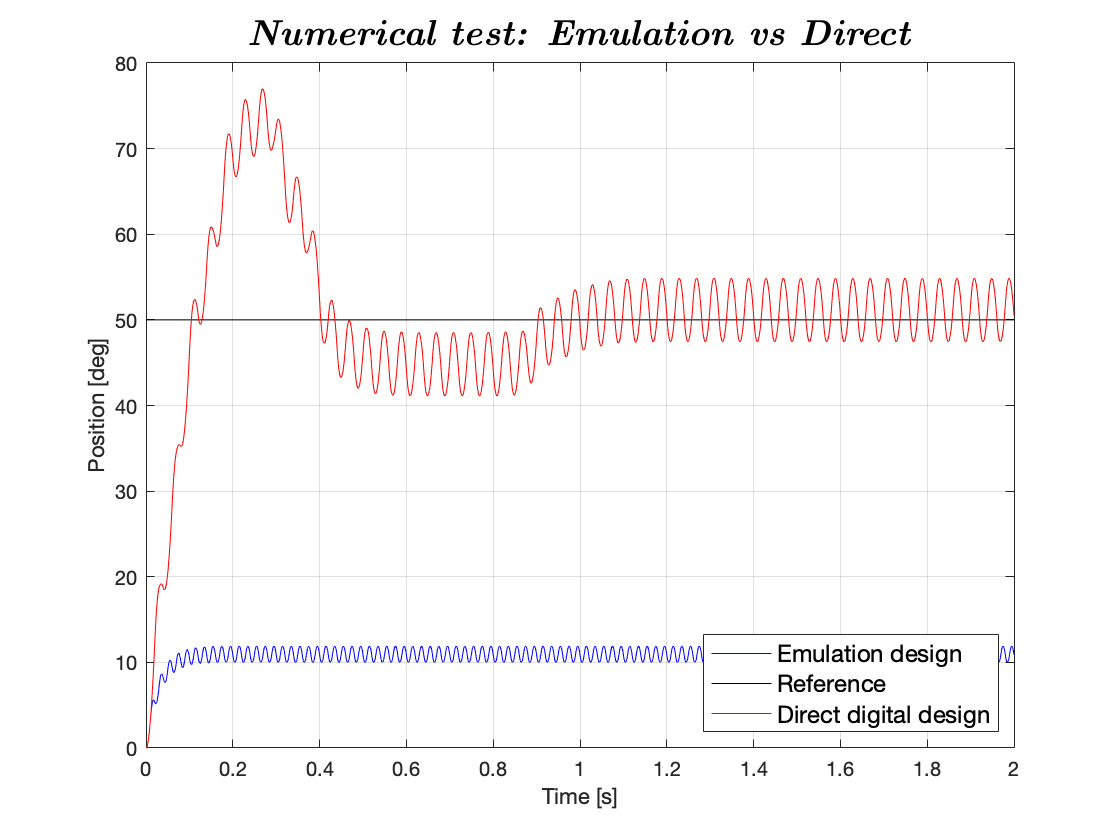

% Sampling time
T_samp = 0.01;

% Step
set_param('Disc_ReducedOrder/Step','Time','0','Before','0','After','50');

% Controller
set_param('Disc_ReducedOrder/Controller/State feed-forward gain','Gain','digital_des_reduced.N_x10');
set_param('Disc_ReducedOrder/Controller/Input feed-forward gain','Gain','digital_des_reduced.N_u10');
set_param('Disc_ReducedOrder/Controller/State feedback gain','Gain','digital_des_reduced_int.K10','Multiplication','Matrix(K*u)');
set_param('Disc_ReducedOrder/Enable Integral','Value','1'); % Integral
set_param('Disc_ReducedOrder/Controller/Ki','Gain','digital_des_reduced_int.Ki10'); % Ki
set_param('Disc_ReducedOrder/Controller/Discrete-Time Integrator','IntegratorMethod','Accumulation: Forward Euler','SampleTime','T_samp'); % Integrator

% Discrete Reduced state observer
set_param('Disc_ReducedOrder/Discrete Reduced Order Observer','A','digital_des_reduced_int.Phy0_10','B','digital_des_reduced_int.Gamma0_10','C','digital_des_reduced_int.H0_10','D','digital_des_reduced_int.J0_10','SampleTime','T_samp');

% Run simulation
sim('Disc_ReducedOrder');
 
% Extract simulation results
direct_intzoh_10ms.t = simres.time; % time vector 
direct_intzoh_10ms.thl = simres.signals(1).values(:,1); % load position
direct_intzoh_10ms.thl_Ref = simres.signals(1).values(:,2); % load position reference

% NUMERICAL COMPARISON
% Plot simulation results
figure
plot(reduced_intfor_10ms.t, reduced_intfor_10ms.thl, 'b');
hold on;
plot(direct_nomzoh_1ms.t, direct_nomzoh_1ms.thl_Ref, 'k');
hold on;
plot(direct_intzoh_10ms.t, direct_intzoh_10ms.thl, 'r');
ylabel('Position [deg]');
xlabel('Time [s]');
grid on;
tit = '\textbf{\textit{Numerical test: Emulation vs Direct}}';
title(tit,'interpreter','latex');
ax = gca;
ax.TitleFontSizeMultiplier = 1.8;
lgd = legend('Emulation design', 'Reference', 'Direct digital design', 'Location', 'southeast');
lgd.FontSize = 12;

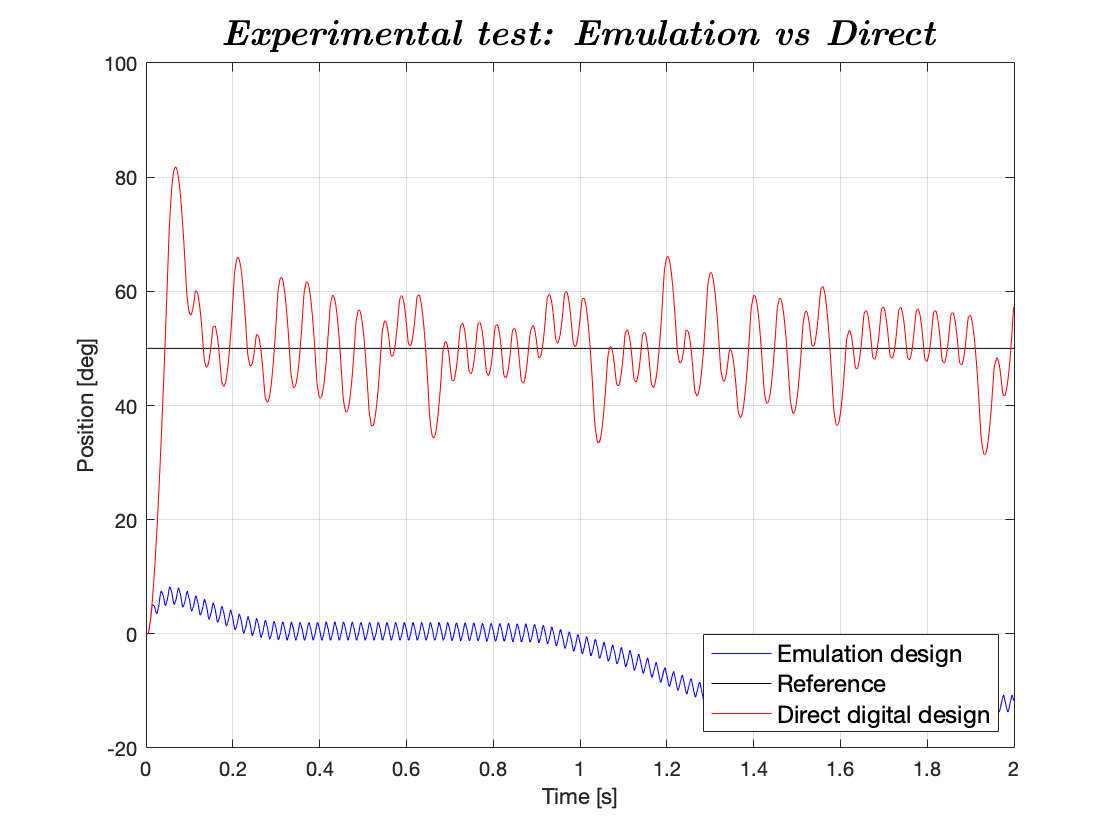

% EXPERIMENTAL COMPARISON
% Plot simulation results
figure
plot(intfor10.time(1:2000), intfor10.signals.values(1:2000,1), 'b');
hold on;
plot(direct_nomzoh_1ms.t, direct_nomzoh_1ms.thl_Ref, 'k');
hold on;
plot(direct_intzoh10.time(1:2000), direct_intzoh10.signals.values(1:2000,1), 'r');
ylabel('Position [deg]');
xlabel('Time [s]');
grid on;
tit = '\textbf{\textit{Experimental test: Emulation vs Direct}}';
title(tit,'interpreter','latex');
ax = gca;
ax.TitleFontSizeMultiplier = 1.8;
lgd = legend('Emulation design', 'Reference', 'Direct digital design', 'Location', 'southeast');
lgd.FontSize = 12;

#### Simulation results [$$T_s = 50ms$$] 

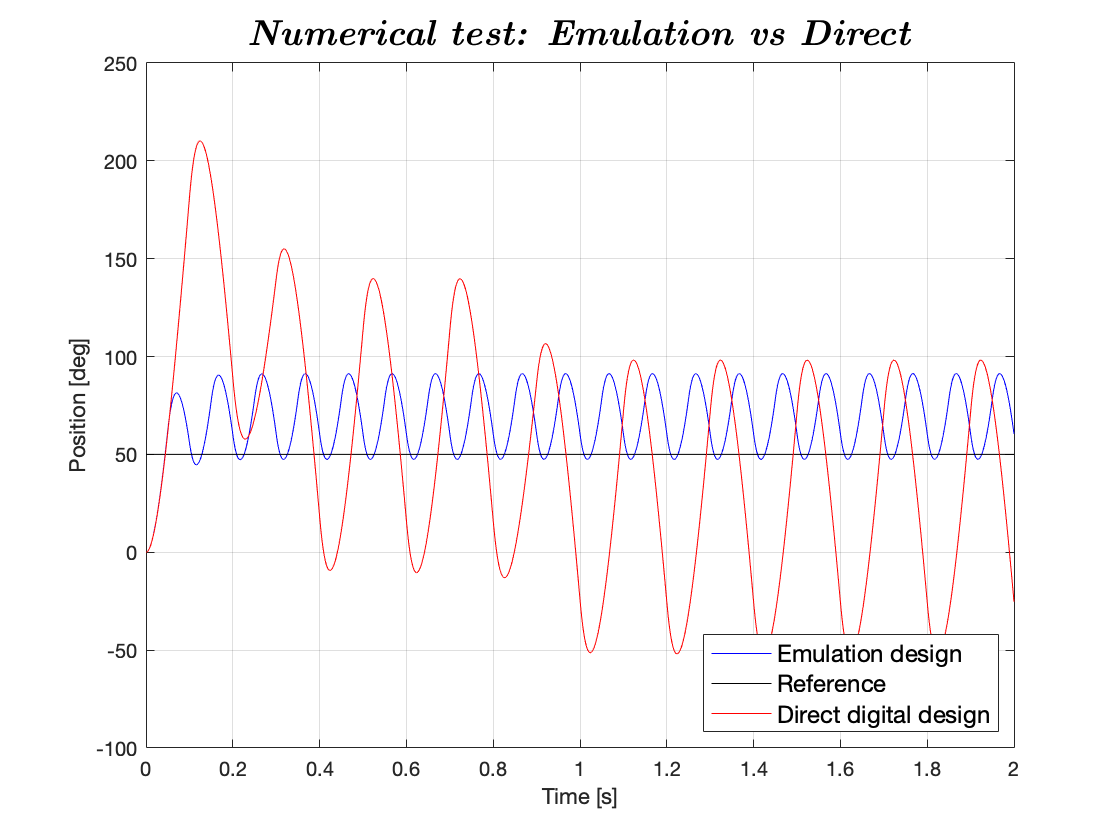

% Sampling time
T_samp = 0.1;

% Step
set_param('Disc_ReducedOrder/Step','Time','0','Before','0','After','50');

% Controller
set_param('Disc_ReducedOrder/Controller/State feed-forward gain','Gain','digital_des_reduced.N_x50');
set_param('Disc_ReducedOrder/Controller/Input feed-forward gain','Gain','digital_des_reduced.N_u50');
set_param('Disc_ReducedOrder/Controller/State feedback gain','Gain','digital_des_reduced_int.K50','Multiplication','Matrix(K*u)');
set_param('Disc_ReducedOrder/Enable Integral','Value','1'); % Integral
set_param('Disc_ReducedOrder/Controller/Ki','Gain','digital_des_reduced_int.Ki50'); % Ki
set_param('Disc_ReducedOrder/Controller/Discrete-Time Integrator','IntegratorMethod','Accumulation: Forward Euler','SampleTime','T_samp'); % Integrator

% Discrete Reduced state observer
set_param('Disc_ReducedOrder/Discrete Reduced Order Observer','A','digital_des_reduced_int.Phy0_50','B','digital_des_reduced_int.Gamma0_50','C','digital_des_reduced_int.H0_50','D','digital_des_reduced_int.J0_50','SampleTime','T_samp');

% Run simulation
sim('Disc_ReducedOrder');
 
% Extract simulation results
direct_intzoh_50ms.t = simres.time; % time vector 
direct_intzoh_50ms.thl = simres.signals(1).values(:,1); % load position
direct_intzoh_50ms.thl_Ref = simres.signals(1).values(:,2); % load position reference

% ts5_low = [];
% ts5_high = [];
% Mp = [];
% time = [];
% j = 1;
% for i=0:0.001:2
%     ts5_high(j) = direct_intzoh_1ms.thl(length(direct_intzoh_1ms.thl))+0.05*direct_intzoh_1ms.thl(length(direct_intzoh_1ms.thl));
%     ts5_low(j) = direct_intzoh_1ms.thl(length(direct_intzoh_1ms.thl))-0.05*direct_intzoh_1ms.thl(length(direct_intzoh_1ms.thl));
%     Mp(j) = direct_intzoh_1ms.thl(length(direct_intzoh_1ms.thl))+0.1*direct_intzoh_1ms.thl(length(direct_intzoh_1ms.thl));
%     time(j) = i;
%     j = j + 1;
% end

% NUMERICAL COMPARISON
% Plot simulation results
figure
plot(reduced_intfor_50ms.t, reduced_intfor_50ms.thl, 'b');
hold on;
plot(direct_nomzoh_1ms.t, direct_nomzoh_1ms.thl_Ref, 'k');
hold on;
plot(direct_intzoh_50ms.t, direct_intzoh_50ms.thl, 'r');
% hold on;
% plot(time, ts5_low, 'color', '#7E2F8E', 'LineStyle', '--');
% hold on;
% plot(time, ts5_high, 'color', '#7E2F8E', 'LineStyale', '--');
% hold on;
% plot(time, Mp, '--k');
ylabel('Position [deg]');
xlabel('Time [s]');
grid on;
tit = '\textbf{\textit{Numerical test: Emulation vs Direct}}';
title(tit,'interpreter','latex');
ax = gca;
ax.TitleFontSizeMultiplier = 1.8;
lgd = legend('Emulation design', 'Reference', 'Direct digital design', 'Location', 'southeast');
lgd.FontSize = 12;

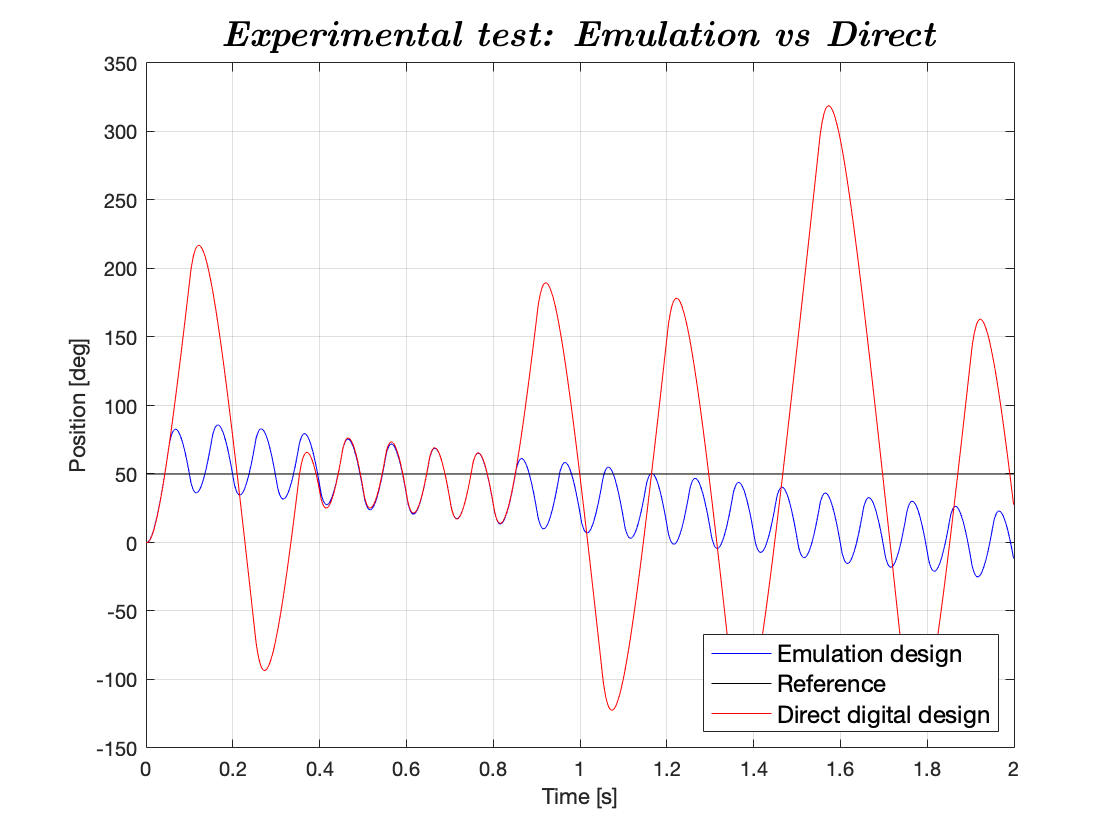

% EXPERIMENTAL COMPARISON
% Plot simulation results
figure
plot(intfor50.time(1:2000), intfor50.signals.values(1:2000,1), 'b');
hold on;
plot(direct_nomzoh_1ms.t, direct_nomzoh_1ms.thl_Ref, 'k');
hold on;
plot(direct_intzoh50.time(1:2000), direct_intzoh50.signals.values(1:2000,1), 'r');
ylabel('Position [deg]');
xlabel('Time [s]');
grid on;
tit = '\textbf{\textit{Experimental test: Emulation vs Direct}}';
title(tit,'interpreter','latex');
ax = gca;
ax.TitleFontSizeMultiplier = 1.8;
lgd = legend('Emulation design', 'Reference', 'Direct digital design', 'Location', 'southeast');
lgd.FontSize = 12;